clc                     % clear command window
clear                   % clear MATLAB workspace
clf

[robotArduino]= SETUPARDUINO('COM3') 

robotArduino =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Nano33BLE'
         AvailablePins: {'D0-D13', 'A0-A7'}
  AvailableDigitalPins: {'D0-D13', 'A0-A7'}
      AvailablePWMPins: {'D0-D13'}
   AvailableAnalogPins: {'A0-A3', 'A6-A7'}
    AvailableI2CBusIDs: [0, 1]
AvailableSerialPortIDs: [1]
             Libraries: {'I2C', 'Servo'}
Show all properties


steerServo = servo(robotArduino, 'D5', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
driveServo = servo(robotArduino, 'D3', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
panServo = servo(robotArduino, 'D6', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);

writePosition(steerServo, 0.5);      % always start servo-command at 0.5
writePosition(driveServo, 0.3);      % always start servo-command at 0.5
writePosition(panServo, 0.5);        % always start servo-command at 0.5
pause(3.0);                          % wait for Arduino to send stable pwm
warning ('actuators live');

clear lid
lid = LIDAR('COM6')

lid =   LIDAR with properties:

        lidar: [1×1 serial]
     pol_data: []
    cart_data: []


lidar_data = lid.scan(5000);

lid.close()

cam = Camera();

obj =   Camera with properties:

           cam: [1×1 webcam]
    intrinsics: [1×1 cameraIntrinsics]
       tagSize: []


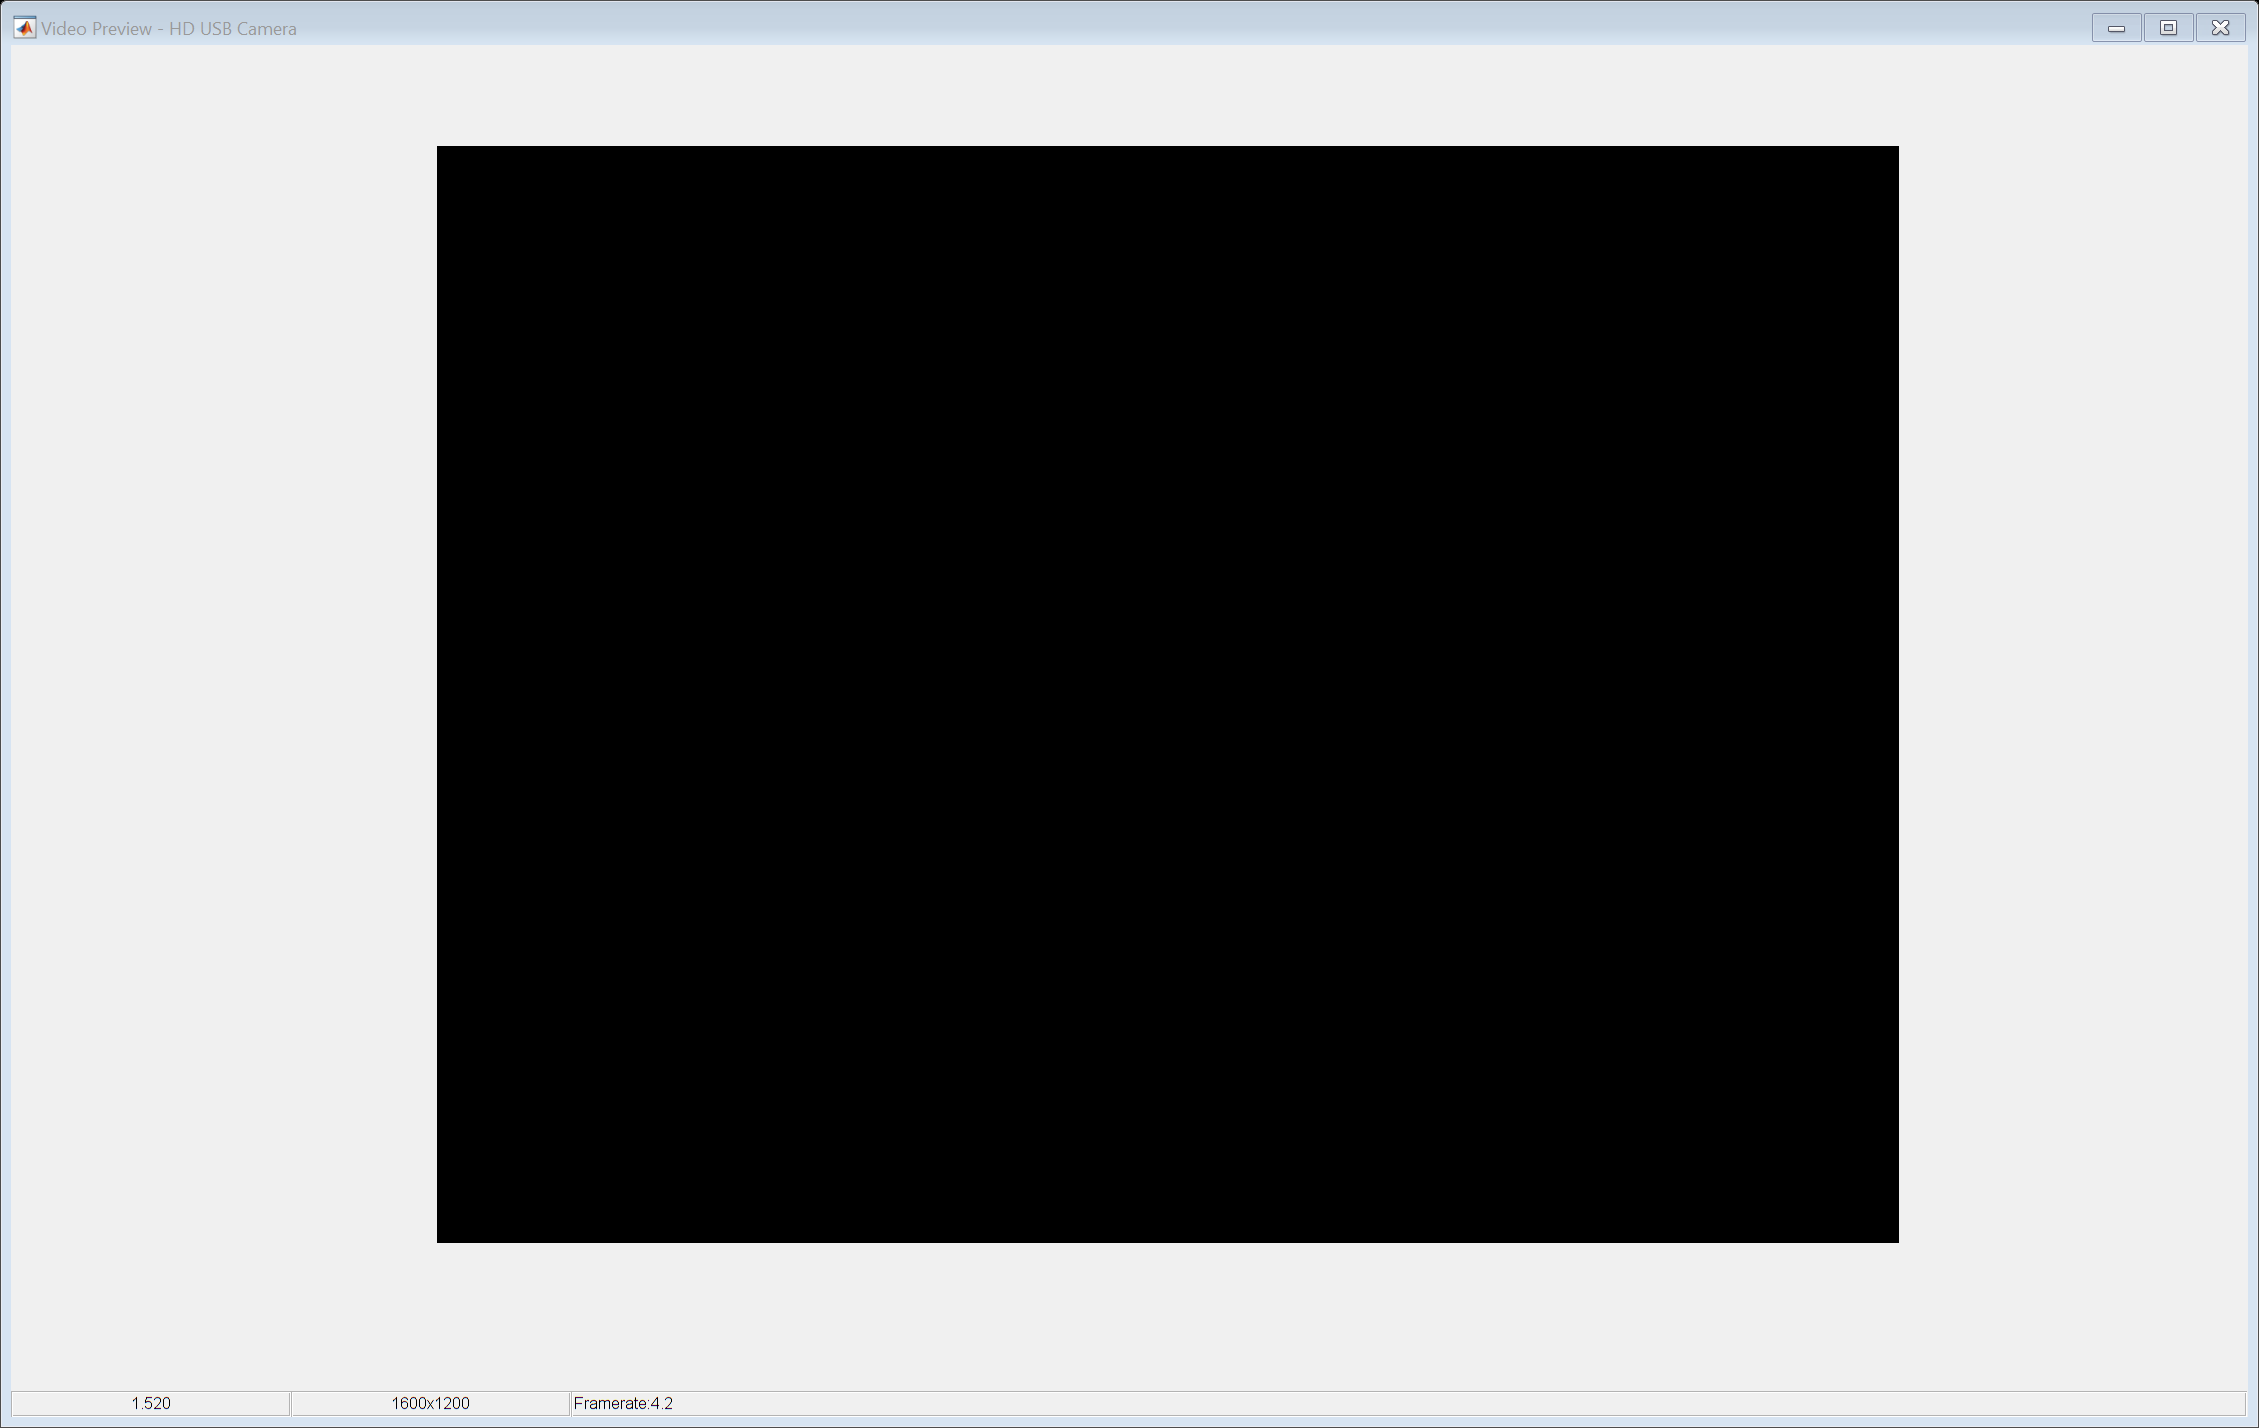

cam.cam.Sharpness = 6;
cam.cam.Exposure = -8;
cam.show

RANSAC fit

% calibrate to 0.1 - 0.3 - 0.9
writePosition(driveServo, 0.3);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.52);
writePosition(panServo, 0.51);

## Outer Course

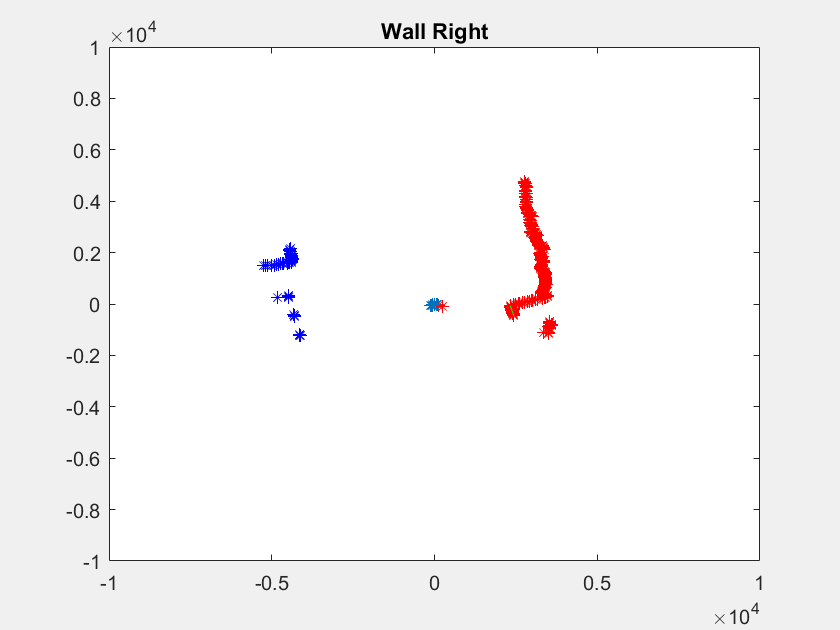

rpoints = 	1.0e+03 *

    0.2576   -0.0874
    3.3640   -1.1182
    3.4963   -1.1384
    3.5061   -1.1178
    3.5259   -0.9361
    3.5209   -0.9116
    3.5061   -0.8848
    3.5114   -0.8633
    3.5371   -0.8466
    3.5792   -0.8335


slope = -3.5583

rpoints = 	1.0e+03 *

    3.1023   -1.0524
    3.1287   -1.0400
    3.1350   -1.0208
    3.1212   -0.9951
    2.4342   -0.7596
    2.4321   -0.7426
    2.4357   -0.7274
    2.4200   -0.7065
    2.4146   -0.6889
    2.4063   -0.6706


slope = 0.2162

rpoints = 	1.0e+03 *

    2.5266   -0.8571
    2.5441   -0.8457
    2.5597   -0.8334
    2.5648   -0.8177
    2.6070   -0.8136
    2.6253   -0.8016
    2.6379   -0.7878
    2.6955   -0.7870
    2.7128   -0.7740
    2.7887   -0.7772


slope = 0.2116

rpoints = 	1.0e+03 *

    2.8741   -0.9750
    2.9066   -0.9662
    2.9391   -0.9570
    2.9554   -0.9422
    2.9659   -0.9256
    3.0050   -0.9176
    3.0336   -0.9059
    3.0698   -0.8963
    3.1234   -0.8911
    3.1683   -0.8829


slope = 5.4784

rpoints = 	1.0e+03 *

    2.9897   -1.0142
    3.1069   -1.0327
    3.1131   -1.0136
    3.1193   -0.9945
    3.1120   -0.9711
    3.1150   -0.9511
    3.1179   -0.9311
    3.1236   -0.9120
    3.0926   -0.8823
    3.0970   -0.8631


slope = -8.2090

rpoints = 	1.0e+03 *

    2.9963   -1.0165
    3.0025   -0.9980
    3.0085   -0.9796
    3.0202   -0.9629
    3.0261   -0.9443
    3.0089   -0.9187
    3.0145   -0.9002
    3.0103   -0.8789
    3.0157   -0.8604
    3.0180   -0.8410


slope = -10.9708

rpoints = 	1.0e+03 *

    3.0281   -1.0066
    3.0380   -0.9892
    3.0440   -0.9705
    3.0461   -0.9506
    3.0127   -0.9199
    3.0183   -0.9014
    3.0055   -0.8775
    3.0070   -0.8579
    3.0093   -0.8386
    3.0135   -0.8199


slope = 0.1262

rpoints = 	1.0e+03 *

    0.3333   -0.1131
    3.4058   -1.1321
    3.4916   -1.1369
    3.4985   -1.1154
    3.5053   -1.0939
    3.5110   -1.0720
    3.4916   -1.0427
    3.4903   -1.0190
    3.4888   -0.9954
    3.4852   -0.9712


slope = 0.0679

rpoints = 	1.0e+03 *

    3.0309   -1.0075
    3.0599   -0.9963
    3.0659   -0.9775
    3.0490   -0.9515
    3.0500   -0.9313
    3.0557   -0.9125
    3.0218   -0.8823
    3.0522   -0.8708
    3.0498   -0.8499
    3.0550   -0.8312


slope = 0.1275

rpoints = 	1.0e+03 *

    0.3428   -0.1163
    3.5595   -1.1832
    3.6456   -1.1870
    3.7243   -1.1874
    3.7420   -1.1678
    3.8065   -1.1623
    3.8136   -1.1389
    3.8205   -1.1154
    3.8273   -1.0919
    3.7072   -1.0086


slope = 0.0082

rpoints = 	1.0e+03 *

    2.9379   -0.9766
    2.9439   -0.9585
    2.9497   -0.9404
    2.9373   -0.9166
    2.9247   -0.8930
    2.9301   -0.8750
    2.9182   -0.8520
    2.9137   -0.8313
    2.9188   -0.8134
    2.9150   -0.7931


slope = 0.0344

rpoints = 	1.0e+03 *

    0.3135   -0.1063
    3.3526   -1.1144
    3.3594   -1.0938
    3.3661   -1.0732
    3.3669   -1.0507
    3.3656   -1.0277
    3.3719   -1.0070
    3.3780   -0.9862
    3.3840   -0.9655
    3.3898   -0.9447


slope = -0.0424

rpoints = 	1.0e+03 *

    2.8325   -0.9609
    2.8383   -0.9435
    2.8440   -0.9260
    2.8316   -0.9028
    2.8027   -0.8746
    2.7851   -0.8504
    2.7854   -0.8318
    2.7847   -0.8130
    2.7955   -0.7976
    2.7907   -0.7777


slope = -0.0657

rpoints = 	1.0e+03 *

    2.9129   -0.9882
    2.9256   -0.9725
    2.9315   -0.9545
    2.9307   -0.9344
    2.9134   -0.9092
    2.9190   -0.8913
    2.9148   -0.8705
    2.9201   -0.8525
    2.9253   -0.8346
    2.9371   -0.8185


slope = -0.0987

rpoints = 	1.0e+03 *

    3.1497   -1.0901
    3.2520   -1.1032
    3.2274   -1.0728
    3.2339   -1.0530
    3.2451   -1.0346
    3.2514   -1.0146
    3.2537   -0.9935
    3.2597   -0.9735
    3.2657   -0.9534
    3.2638   -0.9312


slope = -0.1427

rpoints = 	1.0e+03 *

    3.1600   -1.0504
    3.1664   -1.0310
    3.2184   -1.0261
    3.2246   -1.0063
    3.2308   -0.9865
    3.2626   -0.9743
    3.2714   -0.9551
    3.2965   -0.9405
    3.3243   -0.9264
    3.3300   -0.9060


slope = -0.1610

rpoints = 	1.0e+03 *

    3.4096   -1.1334
    3.4212   -1.1139
    3.4423   -1.0975
    3.4490   -1.0763
    3.4871   -1.0647
    3.4935   -1.0433
    3.5364   -1.0325
    3.5551   -1.0143
    3.5613   -0.9924
    3.5673   -0.9706


slope = -0.2444

rpoints = 	1.0e+03 *

    3.1876   -1.0814
    3.2122   -1.0677
    3.3223   -1.0817
    3.3289   -1.0613
    3.3354   -1.0409
    3.3407   -1.0201
    3.3469   -0.9995
    3.3530   -0.9789
    3.3917   -0.9677
    3.3975   -0.9468


slope = -0.2074

rpoints = 	1.0e+03 *

    2.8649   -0.9523
    2.8868   -0.9399
    2.8925   -0.9222
    2.8962   -0.9038
    2.8874   -0.8816
    2.8918   -0.8636
    2.8913   -0.8441
    2.8964   -0.8264
    2.9014   -0.8086
    2.9064   -0.7907


slope = 4.0123

rpoints = 	1.0e+03 *

    2.9319   -0.9946
    2.9379   -0.9766
    2.9448   -0.9588
    2.9497   -0.9404
    2.9411   -0.9178
    2.9467   -0.8997
    2.9522   -0.8816
    2.9575   -0.8635
    2.9724   -0.8480
    2.9775   -0.8298


slope = 3.6596

rpoints = 	1.0e+03 *

    2.7737   -0.9410
    2.7795   -0.9239
    2.7851   -0.9068
    2.7811   -0.8867
    2.7731   -0.8654
    2.7736   -0.8469
    2.7663   -0.8261
    2.7655   -0.8074
    2.7676   -0.7896
    2.7724   -0.7726


slope = 4.1815

rpoints = 	1.0e+03 *

    3.1761   -1.0558
    3.1826   -1.0362
    3.2136   -1.0246
    3.2199   -1.0048
    3.2107   -0.9803
    3.2166   -0.9606
    3.2225   -0.9408
    3.2282   -0.9210
    3.2396   -0.9028
    3.2643   -0.8881


slope = -0.2575

rpoints = 	1.0e+03 *

    0.3191   -0.1083
    3.4361   -1.1422
    3.4431   -1.1211
    3.4499   -1.0999
    3.4461   -1.0754
    3.4526   -1.0542
    3.4571   -1.0324
    3.4567   -1.0092
    3.4667   -0.9891
    3.4727   -0.9677


slope = 4.4354

rpoints = 	1.0e+03 *

    0.3911   -0.1327
    3.4959   -1.1621
    3.5600   -1.1591
    3.5671   -1.1373
    3.5941   -1.1216
    3.6009   -1.0995
    3.5932   -1.0731
    3.5690   -1.0420
    3.5686   -1.0181
    3.5700   -0.9949


slope = 5.6766

rpoints = 	1.0e+03 *

    3.3403   -1.1103
    3.3471   -1.0898
    3.3623   -1.0720
    3.3965   -1.0599
    3.4029   -1.0390
    3.4466   -1.0293
    3.4557   -1.0089
    3.4917   -0.9962
    3.4977   -0.9747
    3.4795   -0.9467


slope = 4.9481

rpoints = 	1.0e+03 *

    0.3277   -0.1112
    3.5026   -1.1643
    3.5211   -1.1465
    3.5452   -1.1303
    3.5788   -1.1168
    3.5856   -1.0948
    3.5922   -1.0728
    3.6333   -1.0608
    3.6407   -1.0387
    3.6721   -1.0233


slope = 4.1542

rpoints = 	1.0e+03 *

    3.1163   -1.0359
    3.1398   -1.0223
    3.1650   -1.0091
    3.1712   -0.9896
    3.1906   -0.9742
    3.2003   -0.9557
    3.2023   -0.9349
    3.1772   -0.9065
    3.2136   -0.8955
    3.2229   -0.8768


slope = 3.4855

rpoints = 	1.0e+03 *

    2.4853   -0.8261
    2.4903   -0.8108
    2.4953   -0.7955
    2.4934   -0.7781
    2.4962   -0.7622
    2.5009   -0.7468
    2.4987   -0.7295
    2.5031   -0.7142
    2.5017   -0.6972
    2.5117   -0.6834


slope = 4.1167

rpoints = 	1.0e+03 *

    2.5176   -0.8368
    2.5226   -0.8214
    2.5276   -0.8059
    2.5096   -0.7832
    2.5087   -0.7660
    2.5114   -0.7500
    2.5179   -0.7351
    2.5195   -0.7188
    2.5229   -0.7031
    2.5271   -0.6876


slope = 6.8698

rpoints = 	1.0e+03 *

    2.5337   -0.8422
    2.5398   -0.8269
    2.5448   -0.8113
    2.5488   -0.7954
    2.5364   -0.7745
    2.5354   -0.7572
    2.5361   -0.7404
    2.5329   -0.7227
    2.5286   -0.7047
    2.5252   -0.6870


slope = 10.8269

rpoints = 	1.0e+03 *

    0.4072   -0.1381
    2.5944   -0.8624
    2.5997   -0.8464
    2.6048   -0.8305
    2.5660   -0.8007
    2.5613   -0.7821
    2.5631   -0.7654
    2.5524   -0.7452
    2.5474   -0.7268
    2.5470   -0.7098


slope = 0.0867

rpoints = 	1.0e+03 *

    2.5811   -0.8580
    2.5864   -0.8421
    2.5915   -0.8262
    2.5774   -0.8043
    2.5699   -0.7847
    2.5593   -0.7643
    2.5611   -0.7477
    2.5483   -0.7270
    2.5508   -0.7108
    2.5464   -0.6928


slope = 0.1429

rpoints = 	1.0e+03 *

    2.5550   -0.8668
    2.5603   -0.8510
    2.5654   -0.8353
    2.5639   -0.8174
    2.5488   -0.7954
    2.5450   -0.7771
    2.5497   -0.7614
    2.5323   -0.7393
    2.5339   -0.7229
    2.5277   -0.7044


slope = 0.1781

rpoints = 	1.0e+03 *

    2.5862   -0.8774
    2.5916   -0.8615
    2.5968   -0.8455
    2.5781   -0.8220
    2.5812   -0.8055
    2.5651   -0.7832
    2.5469   -0.7606
    2.5515   -0.7449
    2.5502   -0.7276
    2.5392   -0.7076


slope = 0.2528

rpoints = 	1.0e+03 *

    2.6573   -0.9014
    2.6627   -0.8851
    2.6681   -0.8687
    2.6191   -0.8350
    2.6175   -0.8168
    2.5880   -0.7902
    2.5861   -0.7723
    2.5726   -0.7511
    2.5647   -0.7317
    2.5691   -0.7159


slope = 0.3540

rpoints = 	1.0e+03 *

    2.6734   -0.9069
    2.6789   -0.8905
    2.6843   -0.8740
    2.6458   -0.8435
    2.6271   -0.8198
    2.6072   -0.7961
    2.5976   -0.7758
    2.5966   -0.7581
    2.5752   -0.7347
    2.5730   -0.7170


slope = -2.7889

rpoints = 	1.0e+03 *

    2.7198   -0.9227
    2.7254   -0.9059
    2.7309   -0.8892
    2.7249   -0.8687
    2.6796   -0.8362
    2.6569   -0.8113
    2.6570   -0.7935
    2.6244   -0.7662
    2.6166   -0.7465
    2.6067   -0.7264


slope = -2.1048

rpoints = 	1.0e+03 *

    2.8240   -0.9003
    2.7884   -0.8702
    2.7286   -0.8332
    2.7327   -0.8161
    2.7166   -0.7931
    2.6926   -0.7682
    2.6664   -0.7431
    2.6671   -0.7256
    2.6444   -0.7020
    2.6138   -0.6768


slope = -1.6041

rpoints = 	1.0e+03 *

    2.8157   -0.8597
    2.7969   -0.8353
    2.7636   -0.8069
    2.7349   -0.7803
    2.7358   -0.7624
    2.6979   -0.7340
    2.6831   -0.7123
    2.6506   -0.6863
    2.6092   -0.6585
    2.5928   -0.6374


slope = -1.4556

rpoints = 	1.0e+03 *

    3.8802   -1.1848
    2.8563   -0.8530
    2.8231   -0.8242
    2.8041   -0.8000
    2.7666   -0.7710
    2.7500   -0.7482
    2.7121   -0.7200
    2.6564   -0.6878
    2.6499   -0.6688
    2.5938   -0.6377


slope = -1.4793

rpoints = 	1.0e+03 *

    2.5237   -0.8562
    2.5289   -0.8406
    2.5436   -0.8282
    2.5477   -0.8122
    2.5526   -0.7966
    2.5584   -0.7812
    2.5641   -0.7657
    2.5726   -0.7511
    2.5820   -0.7367
    2.6028   -0.7253


slope = -1.6807

rpoints = 	1.0e+03 *

    2.8249   -0.9583
    2.8307   -0.9409
    2.8469   -0.9269
    2.8525   -0.9094
    2.8581   -0.8919
    2.8702   -0.8764
    2.8880   -0.8625
    2.9009   -0.8469
    2.9070   -0.8294
    2.9371   -0.8185


slope = -1.7919

rpoints = 	1.0e+03 *

    2.8684   -0.9731
    2.8744   -0.9555
    2.8802   -0.9378
    2.8487   -0.9082
    2.8256   -0.8818
    2.7812   -0.8492
    2.7864   -0.8321
    2.7886   -0.8142
    2.7704   -0.7904
    2.7464   -0.7653


slope = -1.6470

rpoints = 	1.0e+03 *

    2.7747   -0.9413
    2.8203   -0.9375
    2.8260   -0.9201
    2.7916   -0.8900
    2.7607   -0.8615
    2.7535   -0.8408
    2.7586   -0.8238
    2.7559   -0.8046
    2.7589   -0.7871
    2.7598   -0.7691


slope = -1.9245

rpoints = 	1.0e+03 *

    2.4082   -0.8170
    2.4132   -0.8022
    2.4181   -0.7873
    2.3523   -0.7500
    2.2977   -0.7170
    2.2983   -0.7017
    2.2920   -0.6845
    2.2933   -0.6695
    2.2675   -0.6469
    2.2714   -0.6330


slope = -2.5709

rpoints = 	1.0e+03 *

    2.3874   -0.8099
    2.3923   -0.7952
    2.3971   -0.7805
    2.3876   -0.7612
    2.3865   -0.7447
    2.3834   -0.7277
    2.3878   -0.7131
    2.3691   -0.6917
    2.3560   -0.6722
    2.3495   -0.6547


slope = -3.2675

rpoints = 	1.0e+03 *

    1.9792   -0.6714
    1.9833   -0.6593
    1.9968   -0.6502
    1.9989   -0.6373
    2.0027   -0.6250
    2.0018   -0.6112
    2.0055   -0.5989
    2.0091   -0.5866
    2.0060   -0.5723
    2.0162   -0.5619


slope = 0.1905

rpoints = 	1.0e+03 *

    2.1724   -0.7370
    2.1769   -0.7236
    2.1813   -0.7102
    2.1485   -0.6850
    2.1345   -0.6661
    2.1366   -0.6524
    2.1406   -0.6393
    2.1445   -0.6261
    2.1454   -0.6121
    2.1404   -0.5965


slope = 0.0900

rpoints = 	1.0e+03 *

    1.6989   -0.5763
    1.7024   -0.5659
    1.7059   -0.5554
    1.7007   -0.5422
    1.6915   -0.5279
    1.6900   -0.5160
    1.6931   -0.5056
    1.6962   -0.4952
    1.6992   -0.4848
    1.6848   -0.4695


slope = 0.0122

rpoints = 	1.0e+03 *

    1.7794   -0.6036
    1.7831   -0.5927
    1.7867   -0.5817
    1.7883   -0.5701
    1.7899   -0.5586
    1.7933   -0.5476
    1.7985   -0.5371
    1.8152   -0.5300
    1.8261   -0.5210
    1.8360   -0.5117


slope = -0.0783

rpoints = 214×2
	1.0e+03 *

    1.9669   -0.6673
    1.9710   -0.6552
    1.9749   -0.6430
    1.9731   -0.6291
    1.9722   -0.6155
    1.9597   -0.5984
    1.9461   -0.5812
    1.9669   -0.5743
    1.9742   -0.5633
    1.9738   -0.5500


slope = -0.1776

rpoints = 184×2
	1.0e+03 *

    1.9423   -0.6589
    1.9463   -0.6470
    1.9502   -0.6350
    1.9388   -0.6181
    1.9340   -0.6035
    1.9377   -0.5917
    1.9413   -0.5797
    1.9448   -0.5678
    1.9136   -0.5460
    1.9102   -0.5323


slope = -0.2704

rpoints = 167×2
	1.0e+03 *

    2.0995   -0.7122
    2.1038   -0.6993
    2.1081   -0.6864
    2.0961   -0.6683
    2.0791   -0.6488
    2.0563   -0.6279
    2.0601   -0.6152
    2.0571   -0.6006
    2.0579   -0.5871
    2.0711   -0.5772


slope = -0.3674

rpoints = 126×2
	1.0e+03 *

    2.2321   -0.7572
    2.2367   -0.7435
    2.2412   -0.7297
    2.2075   -0.7038
    2.2042   -0.6878
    2.1969   -0.6708
    2.1674   -0.6473
    2.1713   -0.6339
    2.1608   -0.6165
    2.1790   -0.6072


slope = -0.4773

rpoints = 122×2
	1.0e+03 *

    2.4470   -0.8301
    2.4521   -0.8151
    2.4570   -0.8000
    2.4400   -0.7779
    2.4209   -0.7555
    2.4216   -0.7394
    2.4261   -0.7245
    2.4152   -0.7051
    2.4118   -0.6881
    2.4034   -0.6698


slope = -0.5771

rpoints = 100×2
	1.0e+03 *

    2.6734   -0.9069
    2.6789   -0.8905
    2.6891   -0.8756
    2.6896   -0.8575
    2.6920   -0.8401
    2.6866   -0.8203
    2.6465   -0.7903
    2.6513   -0.7741
    2.6560   -0.7578
    2.6722   -0.7447


slope = -0.6360

rpoints = 136×2
	1.0e+03 *

    2.6526   -0.9181
    2.6838   -0.9104
    2.6893   -0.8939
    2.6919   -0.8765
    2.6829   -0.8554
    2.6881   -0.8389
    2.6426   -0.8069
    2.6341   -0.7866
    2.6379   -0.7702
    2.6397   -0.7531


slope = 1.6739

rpoints = 133×2
	1.0e+03 *

    2.4783   -0.8407
    2.4834   -0.8255
    2.4884   -0.8102
    2.4819   -0.7913
    2.4562   -0.7665
    2.4475   -0.7473
    2.4338   -0.7268
    2.4248   -0.7079
    2.4291   -0.6930
    2.4333   -0.6781


slope = 2.4543

rpoints = 156×2
	1.0e+03 *

    2.6251   -0.8905
    2.6324   -0.8750
    2.6729   -0.8703
    2.6782   -0.8539
    2.6920   -0.8401
    2.6980   -0.8238
    2.7030   -0.8072
    2.7070   -0.7903
    2.7070   -0.7723
    2.6635   -0.7423


slope = 2.7348

rpoints = 173×2
	1.0e+03 *

    2.6232   -0.8899
    2.6286   -0.8738
    2.6339   -0.8576
    2.5829   -0.8235
    2.5831   -0.8061
    2.5756   -0.7864
    2.5804   -0.7706
    2.5841   -0.7545
    2.5800   -0.7361
    2.5845   -0.7202


slope = 4.4566

rpoints = 187×2
	1.0e+03 *

    2.7188   -0.9223
    2.7244   -0.9056
    2.7299   -0.8889
    2.7353   -0.8721
    2.7244   -0.8502
    2.6827   -0.8191
    2.6877   -0.8026
    2.7271   -0.7962
    2.7099   -0.7731
    2.7146   -0.7565


slope = 5.8124

rpoints = 211×2
	1.0e+03 *

    2.7378   -0.9288
    2.7434   -0.9119
    2.7490   -0.8951
    2.7163   -0.8660
    2.6996   -0.8425
    2.6818   -0.8188
    2.6800   -0.8004
    2.6801   -0.7825
    2.6810   -0.7649
    2.6857   -0.7484


slope = 7.7596

rpoints = 190×2
	1.0e+03 *

    2.5294   -0.8581
    2.5346   -0.8425
    2.6006   -0.8468
    2.5448   -0.8113
    2.5115   -0.7838
    1.6814   -0.5134
    1.6826   -0.5025
    1.6808   -0.4907
    1.6838   -0.4804
    1.6771   -0.4674


slope = -24.7564

rpoints = 239×2
	1.0e+03 *

    1.6743   -0.5680
    1.6777   -0.5577
    1.6811   -0.5474
    1.6835   -0.5367
    1.6782   -0.5237
    1.6622   -0.5075
    1.6653   -0.4973
    1.6635   -0.4857
    1.6646   -0.4749
    1.6636   -0.4636


slope = -5.7012

rpoints = 253×2
	1.0e+03 *

    1.6421   -0.5571
    1.6455   -0.5470
    1.6488   -0.5368
    1.6378   -0.5222
    1.6238   -0.5067
    1.6259   -0.4964
    1.6212   -0.4842
    1.6175   -0.4722
    1.6165   -0.4612
    1.6145   -0.4499


slope = 0.2263

rpoints = 233×2
	1.0e+03 *

    2.0616   -0.6994
    2.0953   -0.6965
    2.1128   -0.6879
    2.1170   -0.6749
    2.1221   -0.6622
    2.1433   -0.6544
    2.1914   -0.6544
    2.2117   -0.6457
    2.2329   -0.6371
    2.2445   -0.6255


slope = 16.1695

rpoints = 233×2
	1.0e+03 *

    2.4432   -0.8288
    2.4511   -0.8148
    2.4561   -0.7997
    2.4610   -0.7846
    2.4657   -0.7695
    2.4704   -0.7543
    2.4616   -0.7351
    2.4660   -0.7200
    2.4608   -0.7021
    2.4651   -0.6870


slope = 9.0586

rpoints = 247×2
	1.0e+03 *

    2.5881   -0.8780
    2.5935   -0.8621
    2.5987   -0.8461
    2.5734   -0.8204
    2.5707   -0.8022
    2.5756   -0.7864
    2.5804   -0.7706
    2.5668   -0.7494
    2.5589   -0.7301
    2.5412   -0.7082


slope = -6.0908

rpoints = 279×2
	1.0e+03 *

    2.3429   -0.7948
    2.3477   -0.7804
    2.3524   -0.7660
    2.3342   -0.7442
    2.2614   -0.7057
    2.2648   -0.6915
    2.2690   -0.6776
    2.2731   -0.6637
    2.2771   -0.6497
    2.2801   -0.6354


slope = -12.0391

rpoints = 277×2
	1.0e+03 *

    2.5900   -0.8786
    2.6011   -0.8646
    2.6063   -0.8486
    2.6058   -0.8308
    2.5898   -0.8082
    2.5374   -0.7748
    2.5162   -0.7514
    2.4958   -0.7287
    2.4858   -0.7092
    2.4901   -0.6939


slope = 0.0638

rpoints = 284×2
	1.0e+03 *

    2.3874   -0.8099
    2.3923   -0.7952
    2.3971   -0.7805
    2.3743   -0.7570
    2.3531   -0.7343
    2.3327   -0.7123
    2.3131   -0.6908
    2.3125   -0.6751
    2.3166   -0.6609
    2.3003   -0.6411


slope = 0.0840

rpoints = 284×2
	1.0e+03 *

    2.4631   -0.8356
    2.5166   -0.8365
    2.5217   -0.8211
    2.5267   -0.8056
    2.4829   -0.7748
    2.5173   -0.7686
    2.5219   -0.7531
    2.5265   -0.7376
    2.5050   -0.7147
    2.5354   -0.7066


slope = 0.1029

rpoints = 293×2
	1.0e+03 *

    2.5285   -0.8578
    2.5337   -0.8422
    2.5388   -0.8266
    2.4247   -0.7731
    2.4285   -0.7579
    2.4331   -0.7429
    2.3945   -0.7151
    2.3633   -0.6900
    2.3627   -0.6741
    2.3639   -0.6588


slope = -5.8090

rpoints = 299×2
	1.0e+03 *

    2.3107   -0.7839
    2.3154   -0.7697
    2.3201   -0.7554
    2.2828   -0.7278
    2.2023   -0.6873
    2.2045   -0.6731
    2.2086   -0.6596
    2.2126   -0.6460
    2.2031   -0.6286
    2.1934   -0.6113


slope = -5.4264

rpoints = 288×2
	1.0e+03 *

    2.2813   -0.7739
    2.2927   -0.7621
    2.7166   -0.8845
    2.3018   -0.7339
    2.3063   -0.7197
    2.3002   -0.7023
    2.2354   -0.6676
    2.2222   -0.6488
    2.2204   -0.6335
    2.2204   -0.6188


slope = 0.1227

rpoints = 268×2
	1.0e+03 *

    2.1733   -0.7373
    2.1778   -0.7239
    2.1822   -0.7105
    2.1275   -0.6783
    2.1097   -0.6584
    2.1060   -0.6430
    2.0764   -0.6201
    2.0725   -0.6051
    2.0838   -0.5945
    2.0711   -0.5772


slope = 0.0319

rpoints = 248×2
	1.0e+03 *

    2.0891   -0.7087
    2.1418   -0.7119
    2.1461   -0.6988
    2.1018   -0.6701
    2.1058   -0.6572
    2.1041   -0.6425
    2.1080   -0.6295
    2.1205   -0.6191
    2.1242   -0.6061
    2.1154   -0.5895


slope = -0.0742

rpoints = 227×2
	1.0e+03 *

    2.0597   -0.6987
    2.0877   -0.6940
    2.1471   -0.6991
    2.0961   -0.6683
    2.0763   -0.6479
    2.1041   -0.6425
    2.0716   -0.6187
    2.0466   -0.5975
    2.0473   -0.5841
    2.0171   -0.5621


slope = -0.1368

rpoints = 205×2
	1.0e+03 *

    2.1241   -0.7206
    2.1285   -0.7075
    2.1328   -0.6944
    2.0951   -0.6680
    2.0992   -0.6551
    2.0878   -0.6375
    2.0898   -0.6241
    2.0869   -0.6093
    2.0896   -0.5962
    2.0903   -0.5825


slope = 4.3788

rpoints = 179×2
	1.0e+03 *

    2.2482   -0.7627
    2.2528   -0.7488
    2.2574   -0.7350
    2.2533   -0.7184
    2.2462   -0.7010
    2.2418   -0.6845
    2.2201   -0.6630
    2.2241   -0.6494
    2.2252   -0.6349
    2.2088   -0.6155


slope = 3.1059

rpoints = 162×2
	1.0e+03 *

    2.3287   -0.7900
    2.3335   -0.7757
    2.3382   -0.7613
    2.3018   -0.7339
    2.2729   -0.7093
    2.2772   -0.6953
    2.2786   -0.6805
    2.2827   -0.6665
    2.2723   -0.6483
    2.2907   -0.6384


slope = 2.2065

rpoints = 153×2
	1.0e+03 *

    2.5824   -0.8761
    2.5878   -0.8602
    2.5930   -0.8443
    2.5276   -0.8059
    2.5220   -0.7870
    2.5268   -0.7715
    2.5373   -0.7577
    2.5256   -0.7374
    2.5108   -0.7163
    2.5460   -0.7095


slope = -0.3488

rpoints = 145×2
	1.0e+03 *

    2.5067   -0.8504
    2.5119   -0.8350
    2.5169   -0.8195
    2.5105   -0.8004
    2.5001   -0.7802
    2.4790   -0.7569
    2.4836   -0.7417
    2.4872   -0.7262
    2.4897   -0.7103
    2.4940   -0.6950


slope = -0.3427

rpoints = 156×2
	1.0e+03 *

    2.7292   -0.9259
    2.7349   -0.9091
    2.7404   -0.8923
    2.6725   -0.8520
    2.6566   -0.8290
    2.6617   -0.8127
    2.6523   -0.7921
    2.6715   -0.7800
    2.6762   -0.7635
    2.6760   -0.7457


slope = -0.3585

rpoints = 136×2
	1.0e+03 *

    2.5455   -0.8635
    2.5508   -0.8479
    2.5559   -0.8322
    2.5267   -0.8056
    2.5049   -0.7817
    2.5096   -0.7663
    2.5104   -0.7497
    2.4929   -0.7278
    2.5079   -0.7155
    2.5123   -0.7001


slope = 2.5979

rpoints = 120×2
	1.0e+03 *

    2.6734   -0.9069
    2.6789   -0.8905
    2.6843   -0.8740
    2.6715   -0.8517
    2.6595   -0.8299
    2.6646   -0.8136
    2.6666   -0.7964
    2.6475   -0.7730
    2.6522   -0.7567
    2.6654   -0.7428


slope = -0.3881

rpoints = 124×2
	1.0e+03 *

    2.6298   -0.8921
    2.6352   -0.8760
    2.6406   -0.8598
    2.6344   -0.8399
    2.6395   -0.8237
    2.6349   -0.8045
    2.5986   -0.7760
    2.6033   -0.7601
    2.6156   -0.7463
    2.6202   -0.7302


slope = 2.2610

rpoints = 138×2
	1.0e+03 *

    2.8400   -0.9635
    2.8459   -0.9460
    2.8621   -0.9319
    2.8573   -0.9110
    2.8581   -0.8919
    2.8578   -0.8726
    2.8631   -0.8550
    2.8683   -0.8374
    2.8733   -0.8198
    2.8908   -0.8056


slope = 1.7746

rpoints = 115×2
	1.0e+03 *

    2.8334   -0.9612
    2.8497   -0.9473
    2.8555   -0.9297
    2.8506   -0.9088
    2.8017   -0.8743
    2.8071   -0.8571
    2.8123   -0.8398
    2.8193   -0.8231
    2.8368   -0.8094
    2.8417   -0.7919


slope = 2.3121

rpoints = 115×2
	1.0e+03 *

    2.8249   -0.9583
    2.8753   -0.9558
    2.8811   -0.9381
    2.8430   -0.9064
    2.8476   -0.8886
    2.8501   -0.8702
    2.8276   -0.8444
    2.8289   -0.8259
    2.8281   -0.8069
    2.8167   -0.7849


slope = 2.9142

rpoints = 109×2
	1.0e+03 *

    2.9645   -0.9854
    2.9781   -0.9697
    2.9916   -0.9538
    2.9974   -0.9354
    3.0127   -0.9199
    3.0183   -0.9014
    3.0257   -0.8834
    3.0301   -0.8645
    3.0440   -0.8483
    3.0492   -0.8296


slope = 2.5417

rpoints = 113×2
	1.0e+03 *

    2.9085   -0.9668
    2.9220   -0.9514
    2.9278   -0.9334
    2.9335   -0.9154
    2.9390   -0.8974
    2.9445   -0.8793
    2.9450   -0.8598
    2.9541   -0.8428
    2.9592   -0.8247
    2.9604   -0.8054


slope = 3.1656

rpoints = 145×2
	1.0e+03 *

    3.1287   -1.0400
    3.1474   -1.0248
    3.1536   -1.0054
    3.1473   -0.9822
    2.1892   -0.6685
    2.1914   -0.6544
    2.1877   -0.6387
    2.1935   -0.6258
    2.1973   -0.6123
    2.2010   -0.5988


slope = 3.2269

rpoints = 113×2
	1.0e+03 *

    2.2254   -0.7550
    2.2300   -0.7413
    2.2345   -0.7276
    2.2380   -0.7135
    2.2404   -0.6992
    2.2294   -0.6807
    2.2278   -0.6653
    2.2289   -0.6508
    2.2319   -0.6368
    2.2358   -0.6231


slope = 3.3966

rpoints = 152×2
	1.0e+03 *

    2.2548   -0.7649
    2.2765   -0.7567
    2.2811   -0.7427
    2.2685   -0.7232
    2.2719   -0.7090
    2.2724   -0.6939
    2.2671   -0.6770
    2.2712   -0.6631
    2.2704   -0.6478
    2.2743   -0.6338


slope = 3.5462

rpoints = 104×2
	1.0e+03 *

    2.3002   -0.7803
    2.3335   -0.7757
    2.3382   -0.7613
    2.3428   -0.7469
    2.6751   -0.8168
    2.6800   -0.8004
    2.8625   -0.8357
    2.8676   -0.8181
    3.0084   -0.8384
    3.0771   -0.8372


slope = 3.9690

rpoints = 149×2
	1.0e+03 *

    2.9247   -0.9722
    3.0104   -0.9802
    3.0583   -0.9751
    3.1941   -0.9968
    3.3532   -1.0239
    3.5520   -1.0608
    3.5949   -1.0496
    3.6013   -1.0275
    3.6075   -1.0053
    3.6136   -0.9832


slope = 3.5953

rpoints = 169×2
	1.0e+03 *

    3.1989   -1.0633
    3.2120   -1.0458
    3.2184   -1.0261
    3.2256   -1.0066
    3.2317   -0.9868
    3.2166   -0.9606
    3.2205   -0.9403
    3.2282   -0.9210
    3.2338   -0.9012
    3.2750   -0.8910


slope = 5.6944

rpoints = 128×2
	1.0e+03 *

    2.9991   -1.0174
    3.0205   -1.0040
    3.0523   -0.9938
    3.0631   -0.9766
    3.0643   -0.9563
    3.0701   -0.9374
    3.0652   -0.9154
    3.0689   -0.8960
    3.0743   -0.8771
    3.0652   -0.8542


slope = 6.7031

rpoints = 137×2
	1.0e+03 *

    3.0067   -1.0200
    3.0129   -1.0015
    3.0190   -0.9830
    3.0021   -0.9571
    3.0051   -0.9378
    3.0022   -0.9167
    2.9972   -0.8951
    3.0026   -0.8766
    2.9926   -0.8538
    3.0132   -0.8397


slope = 7.0077

rpoints = 135×2
	1.0e+03 *

    3.2824   -1.0911
    3.2890   -1.0709
    3.2994   -1.0519
    3.3125   -1.0337
    3.3216   -1.0142
    3.3278   -0.9938
    3.3338   -0.9733
    3.3292   -0.9498
    3.3349   -0.9294
    3.3406   -0.9089


slope = 5.3905

rpoints = 191×2
	1.0e+03 *

    3.2141   -1.0684
    3.2225   -1.0492
    3.2613   -1.0398
    3.2676   -1.0197
    3.2738   -0.9996
    3.3009   -0.9858
    3.3069   -0.9655
    3.3128   -0.9452
    3.3253   -0.9267
    3.3309   -0.9062


slope = 11.6121

rpoints = 181×2
	1.0e+03 *

    3.1752   -1.0554
    3.2871   -1.0703
    3.2937   -1.0501
    3.3125   -1.0337
    3.3235   -1.0148
    3.3307   -0.9947
    3.3357   -0.9739
    3.3426   -0.9537
    3.3503   -0.9337
    3.3541   -0.9125


slope = -2.7596

rpoints = 214×2
	1.0e+03 *

    3.1856   -1.0589
    3.2016   -1.0424
    3.2270   -1.0288
    3.2332   -1.0090
    3.2394   -0.9891
    3.2262   -0.9635
    3.2522   -0.9495
    3.2455   -0.9260
    3.2251   -0.8988
    3.2286   -0.8784


slope = 20.5093

rpoints = 214×2
	1.0e+03 *

    3.1913   -1.0608
    3.1978   -1.0412
    3.2346   -1.0312
    3.2409   -1.0114
    3.2575   -0.9947
    3.2693   -0.9763
    3.2762   -0.9565
    3.3080   -0.9438
    3.3137   -0.9235
    3.3193   -0.9031


slope = 21.0296

rpoints = 213×2
	1.0e+03 *

    3.2634   -1.0848
    3.3490   -1.0904
    3.3680   -1.0738
    3.3745   -1.0531
    3.3685   -1.0285
    3.3728   -1.0072
    3.3434   -0.9761
    3.3493   -0.9556
    3.3571   -0.9355
    3.3608   -0.9144


slope = 0.0114

rpoints = 225×2
	1.0e+03 *

    3.2008   -1.0640
    3.2719   -1.0653
    3.2784   -1.0452
    3.3000   -1.0298
    3.3063   -1.0095
    3.3105   -0.9886
    3.2762   -0.9565
    3.2820   -0.9364
    3.2713   -0.9116
    3.2769   -0.8915


slope = -2.7783

rpoints = 224×2
	1.0e+03 *

    3.1809   -1.0573
    3.1921   -1.0393
    3.1993   -1.0200
    3.2055   -1.0003
    3.2212   -0.9836
    3.2636   -0.9746
    3.2724   -0.9554
    3.2782   -0.9353
    3.2839   -0.9151
    3.2450   -0.8829


slope = -13.2980

rpoints = 220×2
	1.0e+03 *

    3.1790   -1.0567
    3.1921   -1.0393
    3.2251   -1.0282
    3.2399   -1.0111
    3.2461   -0.9911
    3.2770   -0.9786
    3.2829   -0.9585
    3.2993   -0.9413
    3.3051   -0.9210
    3.3107   -0.9007


slope = 0.0377

rpoints = 212×2
	1.0e+03 *

    3.0247   -1.0261
    3.0983   -1.0299
    3.1046   -1.0108
    3.1107   -0.9918
    3.1120   -0.9711
    3.1074   -0.9488
    3.0882   -0.9223
    3.1188   -0.9106
    3.0897   -0.8815
    3.0671   -0.8547


slope = 0.0518

rpoints = 213×2
	1.0e+03 *

    3.0395   -1.0103
    3.0456   -0.9917
    3.0517   -0.9729
    3.0442   -0.9500
    3.0471   -0.9304
    3.0528   -0.9117
    3.0545   -0.8918
    3.0455   -0.8689
    3.0508   -0.8502
    3.0424   -0.8277


slope = 0.0366

rpoints = 218×2
	1.0e+03 *

    2.9366   -0.9962
    2.9436   -0.9785
    2.9486   -0.9601
    2.9545   -0.9419
    2.9535   -0.9217
    2.9237   -0.8927
    2.9225   -0.8728
    2.9134   -0.8506
    2.9185   -0.8327
    2.9207   -0.8139


slope = 0.1454

rpoints = 215×2
	1.0e+03 *

    3.0575   -1.0163
    3.0694   -0.9994
    3.0755   -0.9805
    3.0814   -0.9616
    3.0806   -0.9406
    3.0863   -0.9217
    3.0881   -0.9016
    3.0974   -0.8837
    3.0989   -0.8636
    3.0723   -0.8359


slope = 0.1148

rpoints = 207×2
	1.0e+03 *

    3.0765   -1.0226
    3.1407   -1.0226
    3.1469   -1.0033
    3.1206   -0.9738
    3.1265   -0.9546
    3.1323   -0.9354
    3.1361   -0.9156
    3.1416   -0.8963
    3.1471   -0.8770
    3.1341   -0.8527


slope = 0.1211

rpoints = 211×2
	1.0e+03 *

    2.9303   -0.9741
    2.9363   -0.9560
    2.9421   -0.9380
    2.9239   -0.9125
    2.9161   -0.8904
    2.9205   -0.8722
    2.9172   -0.8517
    2.9157   -0.8319
    2.9178   -0.8131
    2.9112   -0.7920


slope = -7.7481

rpoints = 207×2
	1.0e+03 *

    2.9754   -1.0094
    2.9816   -0.9911
    2.9876   -0.9728
    2.9669   -0.9459
    2.9707   -0.9271
    2.9534   -0.9018
    2.9503   -0.8811
    2.9556   -0.8629
    2.9464   -0.8406
    2.9371   -0.8185


slope = -6.4190

rpoints = 205×2
	1.0e+03 *

    2.8791   -0.9570
    2.9020   -0.9449
    2.9078   -0.9271
    2.9001   -0.9050
    2.9017   -0.8860
    2.8678   -0.8564
    2.8615   -0.8355
    2.8666   -0.8179
    2.8793   -0.8024
    2.8842   -0.7847


slope = -7.4641

rpoints = 196×2
	1.0e+03 *

    2.7936   -0.9477
    2.7994   -0.9305
    2.8051   -0.9133
    2.7706   -0.8833
    2.7664   -0.8633
    2.7353   -0.8352
    2.7395   -0.8181
    2.7406   -0.8001
    2.7262   -0.7778
    2.7175   -0.7573


slope = 0.1304

rpoints = 170×2
	1.0e+03 *

    2.6648   -0.9040
    2.6703   -0.8876
    2.6757   -0.8712
    2.6486   -0.8444
    2.6442   -0.8252
    2.6196   -0.7999
    2.6216   -0.7829
    2.6244   -0.7662
    2.6301   -0.7504
    2.6346   -0.7342


slope = 0.0205

rpoints = 158×2
	1.0e+03 *

    2.6999   -0.9159
    2.7054   -0.8993
    2.7109   -0.8827
    2.6782   -0.8539
    2.6767   -0.8353
    2.6655   -0.8139
    2.6427   -0.7892
    2.6360   -0.7696
    2.6397   -0.7531
    2.6442   -0.7369


slope = 7.4884

rpoints = 124×2
	1.0e+03 *

    2.8391   -0.9631
    2.8449   -0.9457
    2.8507   -0.9282
    2.8135   -0.8970
    2.8161   -0.8788
    2.8214   -0.8615
    2.8075   -0.8384
    2.8126   -0.8212
    2.8176   -0.8039
    2.8225   -0.7865


slope = 4.1531

rpoints = 102×2
	1.0e+03 *

    3.1695   -1.0536
    3.1902   -1.0387
    3.2232   -1.0276
    3.2294   -1.0078
    3.2566   -0.9944
    3.2942   -0.9838
    3.3444   -0.9764
    3.3580   -0.9581
    3.3638   -0.9374
    3.3743   -0.9181


slope = 4.0101

rpoints = 109×2
	1.0e+03 *

    2.1743   -0.7376
    2.1788   -0.7242
    2.1832   -0.7108
    2.1666   -0.6907
    2.1660   -0.6759
    2.1682   -0.6620
    2.1626   -0.6458
    2.1598   -0.6306
    2.1637   -0.6173
    2.1742   -0.6059


slope = 3.3062

rpoints = 104×2
	1.0e+03 *

    2.2207   -0.7533
    2.2253   -0.7397
    2.2298   -0.7260
    2.2075   -0.7038
    2.1994   -0.6864
    2.2007   -0.6720
    2.2048   -0.6584
    2.2088   -0.6449
    2.2098   -0.6305
    2.2117   -0.6164


slope = 4.0664

rpoints = 115×2
	1.0e+03 *

    2.2538   -0.7801
    2.2586   -0.7662
    2.2632   -0.7523
    2.2478   -0.7319
    2.2437   -0.7153
    2.2424   -0.6998
    2.2437   -0.6851
    2.2393   -0.6687
    2.2433   -0.6550
    2.2473   -0.6412


slope = 4.5844

rpoints = 110×2
	1.0e+03 *

    2.6468   -0.8979
    2.6789   -0.8905
    2.6929   -0.8768
    2.6982   -0.8602
    2.7998   -0.8737
    2.8912   -0.8828
    2.9608   -0.8842
    3.0785   -0.8988
    3.1301   -0.8930
    3.1914   -0.8894


slope = 1.3820

rpoints = 116×2
	1.0e+03 *

    2.9272   -0.9930
    2.9787   -0.9902
    2.9876   -0.9728
    2.9935   -0.9544
    3.0184   -0.9420
    3.0251   -0.9237
    3.0298   -0.9048
    3.0343   -0.8859
    3.0397   -0.8672
    3.0450   -0.8486


slope = 7.0439

rpoints = 113×2
	1.0e+03 *

    3.0834   -1.0460
    3.0936   -1.0283
    3.0998   -1.0093
    3.1022   -0.9890
    3.1120   -0.9711
    3.1189   -0.9523
    3.1246   -0.9331
    3.1303   -0.9139
    3.1359   -0.8947
    3.1105   -0.8668


slope = 7.7587

rpoints = 111×2
	1.0e+03 *

    3.1002   -1.0305
    3.1331   -1.0201
    3.1622   -1.0082
    3.1683   -0.9887
    3.1743   -0.9692
    3.2138   -0.9597
    3.2196   -0.9400
    3.2051   -0.9144
    3.2309   -0.9004
    3.2161   -0.8750


slope = 0.9399

rpoints = 105×2
	1.0e+03 *

    3.1268   -1.0394
    3.1578   -1.0282
    3.1641   -1.0088
    3.1635   -0.9872
    3.1954   -0.9757
    3.1831   -0.9506
    3.1812   -0.9288
    3.1878   -0.9095
    3.2001   -0.8918
    3.1987   -0.8703


slope = 1.4050

rpoints = 106×2
	1.0e+03 *

    3.0376   -1.0097
    3.0437   -0.9910
    3.0498   -0.9723
    3.0528   -0.9527
    3.0443   -0.9295
    3.0489   -0.9105
    3.0478   -0.8898
    3.0532   -0.8711
    3.0440   -0.8483
    3.0385   -0.8267


slope = 1.1235

rpoints = 106×2
	1.0e+03 *

    3.2084   -1.0665
    3.2358   -1.0536
    3.2546   -1.0376
    3.2619   -1.0179
    3.2757   -1.0002
    3.3182   -0.9909
    3.2877   -0.9599
    3.2936   -0.9397
    3.3359   -0.9296
    3.3550   -0.9128


slope = 1.3259

rpoints = 111×2
	1.0e+03 *

    3.2644   -1.0851
    3.2852   -1.0697
    3.2975   -1.0513
    3.3125   -1.0337
    3.3187   -1.0133
    3.3163   -0.9904
    3.3156   -0.9680
    3.3215   -0.9476
    3.3272   -0.9272
    3.3329   -0.9068


slope = 0.9950

rpoints = 125×2
	1.0e+03 *

    3.1325   -1.0413
    3.1388   -1.0220
    3.1460   -1.0030
    3.1511   -0.9834
    3.1380   -0.9581
    3.1428   -0.9386
    3.1418   -0.9173
    3.1464   -0.8977
    3.1509   -0.8781
    3.1572   -0.8590


slope = 1.4297

rpoints = 153×2
	1.0e+03 *

    2.9442   -0.9988
    2.9503   -0.9807
    2.9562   -0.9625
    2.9554   -0.9422
    2.9249   -0.9128
    2.9190   -0.8913
    2.9205   -0.8722
    2.9230   -0.8534
    2.9176   -0.8324
    2.9159   -0.8126


slope = 1.5292

rpoints = 145×2
	1.0e+03 *

    3.2463   -1.0791
    3.2605   -1.0616
    3.2851   -1.0473
    3.2924   -1.0274
    3.3025   -1.0084
    3.3211   -0.9918
    3.3271   -0.9714
    3.3330   -0.9509
    3.3243   -0.9264
    3.3039   -0.8989


slope = 0.0743

rpoints = 134×2
	1.0e+03 *

    3.0613   -1.0176
    3.0675   -0.9988
    3.0736   -0.9799
    3.0671   -0.9571
    3.0701   -0.9374
    3.0700   -0.9168
    3.0449   -0.8890
    3.0503   -0.8703
    3.0556   -0.8515
    3.0762   -0.8369


slope = 1.7576

rpoints = 143×2
	1.0e+03 *

    3.0642   -1.0185
    3.0818   -1.0034
    3.1002   -0.9884
    3.0939   -0.9655
    3.1122   -0.9503
    3.1055   -0.9274
    3.0929   -0.9030
    3.0945   -0.8829
    3.0845   -0.8596
    3.0897   -0.8406


slope = 1.8129

rpoints = 149×2
	1.0e+03 *

    3.2027   -1.0646
    3.2367   -1.0539
    3.2432   -1.0340
    3.2504   -1.0143
    3.2556   -0.9941
    3.2339   -0.9658
    3.2397   -0.9459
    3.2455   -0.9260
    3.2511   -0.9060
    3.2412   -0.8818


slope = 1.4607

rpoints = 150×2
	1.0e+03 *

    3.1856   -1.0589
    3.1921   -1.0393
    3.2155   -1.0252
    3.2218   -1.0054
    3.1963   -0.9760
    3.1975   -0.9549
    3.1697   -0.9254
    3.1705   -0.9046
    3.1760   -0.8851
    3.1814   -0.8655


slope = 1.8074

rpoints = 150×2
	1.0e+03 *

    3.1069   -1.0327
    3.1303   -1.0192
    3.1365   -1.0000
    3.1406   -0.9801
    3.1466   -0.9608
    3.1524   -0.9414
    3.1178   -0.9103
    3.1176   -0.8895
    3.1037   -0.8649
    3.1090   -0.8459


slope = 0.2119

rpoints = 160×2
	1.0e+03 *

    0.3921   -0.1330
    3.6601   -1.2166
    3.7046   -1.2062
    3.7186   -1.1856
    3.7277   -1.1633
    3.7348   -1.1404
    3.7791   -1.1286
    3.7859   -1.1053
    3.7782   -1.0780
    3.7992   -1.0588


slope = 0.3221

rpoints = 270×2
	1.0e+03 *

    3.0512   -1.0351
    3.0841   -1.0252
    3.1226   -1.0167
    3.1326   -0.9987
    3.1397   -0.9798
    3.1619   -0.9654
    3.1965   -0.9546
    3.2023   -0.9349
    3.2080   -0.9153
    3.2136   -0.8955


slope = 0.3782

rpoints = 198×2
	1.0e+03 *

    0.3267   -0.1108
    3.4200   -1.1368
    3.4288   -1.1164
    3.4775   -1.1087
    3.4986   -1.0918
    3.5158   -1.0735
    3.5520   -1.0608
    3.5604   -1.0395
    3.5676   -1.0179
    3.5738   -0.9959


slope = 0.3192

rpoints = 236×2
	1.0e+03 *

    0.2642   -0.0896
    3.3318   -1.1075
    3.3756   -1.0991
    3.4128   -1.0881
    3.4642   -1.0811
    3.4871   -1.0647
    3.5089   -1.0479
    3.5152   -1.0263
    3.5292   -1.0069
    3.5430   -0.9873


slope = 0.2355

rpoints = 213×2
	1.0e+03 *

    0.2945   -0.0999
    3.4798   -1.1567
    3.5353   -1.1511
    3.5890   -1.1442
    3.6151   -1.1281
    3.6879   -1.1261
    3.6948   -1.1034
    3.6967   -1.0793
    3.7032   -1.0566
    3.7096   -1.0338


slope = 0.0977

rpoints = 130×2
	1.0e+03 *

    4.1763   -1.1087
    4.1831   -1.0831
    4.1732   -1.0532
    4.1388   -1.0175
    4.1449   -0.9921
    4.1753   -0.9723
    4.1812   -0.9466
    4.1869   -0.9209
    4.1865   -0.7603
    4.1901   -0.7344


slope = 0.0116

rpoints = 120×2
	1.0e+03 *

    4.4236   -0.7753
    4.4282   -0.7481
    4.4328   -0.7209
    4.4806   -0.4487
    4.4833   -0.4212
    4.4599   -0.3913
    4.4622   -0.3639
    2.6238    0.0282
    2.6236    0.0443
    2.6233    0.0604


slope = -0.0951

rpoints = 142×2
	1.0e+03 *

    2.7555   -0.4308
    2.7107   -0.4067
    2.7121   -0.3899
    2.7154   -0.3734
    2.7177   -0.3567
    2.7278   -0.3410
    2.7387   -0.3253
    2.7546   -0.3101
    2.7773   -0.2954
    2.7791   -0.2783


slope = -0.1922

rpoints = 134×2
	1.0e+03 *

    2.6809   -0.9095
    2.6874   -0.8933
    2.6929   -0.8768
    2.6972   -0.8599
    2.6967   -0.8416
    2.6550   -0.8107
    2.6446   -0.7898
    2.6494   -0.7735
    2.6541   -0.7572
    2.6394   -0.7355


slope = 2.7046

rpoints = 125×2
	1.0e+03 *

    2.7235   -0.9239
    2.7425   -0.9116
    2.7480   -0.8947
    2.7401   -0.8736
    2.7454   -0.8568
    2.7315   -0.8340
    2.7366   -0.8172
    2.7415   -0.8004
    2.7464   -0.7836
    2.6674   -0.7433


slope = 2.0482

rpoints = 70×2
	1.0e+03 *

    2.0796   -0.7055
    2.0896   -0.6946
    2.0938   -0.6817
    2.0922   -0.6670
    2.0829   -0.6500
    2.0869   -0.6372
    2.0908   -0.6244
    2.1090   -0.6157
    2.1214   -0.6052
    2.1250   -0.5922


slope = 1.9776

rpoints = 110×2
	1.0e+03 *

    2.9920   -0.9946
    2.9981   -0.9762
    3.0040   -0.9577
    3.0089   -0.9390
    3.0127   -0.9199
    3.0183   -0.9014
    3.0238   -0.8828
    3.0311   -0.8648
    3.0402   -0.8472
    3.0453   -0.8285


slope = 2.0626

rpoints = 54×2
	1.0e+03 *

    3.1211   -1.0375
    3.1398   -1.0223
    3.1584   -1.0069
    3.1693   -0.9890
    3.1772   -0.9701
    3.1831   -0.9506
    3.1965   -0.9333
    3.2157   -0.9175
    3.2347   -0.9014
    3.2402   -0.8816


slope = 1.7537

rpoints = 52×2
	1.0e+03 *

    3.2027   -1.0646
    3.2177   -1.0477
    3.2536   -1.0373
    3.2657   -1.0191
    3.2910   -1.0049
    3.3249   -0.9929
    3.3242   -0.9705
    3.3474   -0.9550
    3.3609   -0.9366
    3.3840   -0.9207


slope = 1.7734

rpoints = 73×2
	1.0e+03 *

    0.4470   -0.1516
    3.8091   -1.2662
    3.8900   -1.2666
    3.9482   -1.2588
    3.9769   -1.2410
    3.9844   -1.2166
    4.0422   -1.1802
    4.0427   -1.1534
    4.0564   -1.1304
    4.0633   -1.1055


slope = 1.3421

rpoints = 57×2
	1.0e+03 *

    3.8628   -1.3104
    3.9609   -1.3166
    3.9708   -1.2929
    3.9787   -1.2685
    3.9874   -1.2443
    4.0294   -1.2303
    4.0474   -1.2087
    4.0768   -1.1903
    4.0898   -1.1668
    4.0998   -1.1425


slope = 1.3082

rpoints = 53×2
	1.0e+03 *

    4.3946   -1.2538
    4.4023   -1.2268
    4.4097   -1.1997
    4.4170   -1.1726
    4.4241   -1.1455
    4.4330   -1.1188
    4.4466   -1.0932
    4.4581   -1.0670
    4.4782   -1.0428
    4.5167   -1.0226


slope = 1.3079

rpoints = 51×2
	1.0e+03 *

    4.4153   -1.3186
    4.4013   -1.2850
    4.4091   -1.2579
    4.4234   -1.2327
    4.4444   -1.2092
    4.4518   -1.1819
    4.4899   -1.1625
    4.5241   -1.1418
    4.5398   -1.1161
    4.5476   -1.0884


slope = 1.3249

rpoints = 54×2
	1.0e+03 *

    4.5850   -1.3081
    4.5805   -1.2765
    4.5882   -1.2483
    4.5542   -1.2091
    4.5393   -1.1753
    4.5387   -1.1455
    4.5320   -1.1142
    4.5388   -1.0864
    4.5415   -1.0575
    4.5479   -1.0296


slope = -8.8817

rpoints = 83×2
	1.0e+03 *

    4.5956   -1.3112
    4.6036   -1.2829
    4.6114   -1.2546
    4.5845   -1.0973
    4.5483   -1.0591
    4.5547   -1.0312
    4.5610   -1.0032
    4.5583   -0.9733
    4.5544   -0.9432
    4.5424   -0.9117


slope = -8.3373

rpoints = 130×2
	1.0e+03 *

    4.5793   -1.3982
    4.5696   -1.3646
    4.5635   -1.3324
    4.5629   -1.3018
    4.5410   -1.2655
    4.5438   -1.2362
    4.5455   -1.2068
    4.5393   -1.1753
    4.5387   -1.1455
    4.5456   -1.1176


slope = -8.2323

rpoints = 124×2
	1.0e+03 *

    4.5217   -1.2601
    4.5064   -1.1668
    4.4689   -1.1278
    4.4864   -1.1030
    4.4688   -1.0696
    4.4753   -1.0421
    4.4816   -1.0146
    4.4750   -0.9843
    4.4771   -0.9559
    4.4623   -0.9242


slope = -11.1480

rpoints = 131×2
	1.0e+03 *

    4.4747   -1.3363
    4.4675   -1.3043
    4.4754   -1.2769
    4.4832   -1.2494
    4.4908   -1.2218
    4.4679   -1.1276
    4.4427   -1.0922
    4.4493   -1.0649
    4.4412   -1.0342
    4.4387   -1.0049


slope = -15.0240

rpoints = 59×2
	1.0e+03 *

    4.4427   -1.2675
    4.4504   -1.2402
    4.4242   -1.2037
    4.4151   -1.1721
    4.3999   -1.1392
    4.4049   -1.1117
    4.4116   -1.0846
    4.4085   -1.0552
    4.4149   -1.0281
    4.4211   -1.0009


slope = 8.5968

rpoints = 71×2
	1.0e+03 *

    4.4148   -1.3480
    4.4029   -1.3149
    4.4041   -1.2858
    4.3783   -1.2492
    4.3840   -1.2217
    4.3846   -1.1929
    4.3919   -1.1660
    4.3922   -1.1372
    4.3981   -1.1100
    4.3971   -1.0810


slope = -4.2230

rpoints = 82×2
	1.0e+03 *

    4.3088   -1.2008
    4.3094   -1.1724
    4.3165   -1.1459
    4.3079   -1.1154
    4.3128   -1.0884
    4.3174   -1.0614
    4.3258   -1.0354
    4.3214   -1.0063
    4.3372   -0.9819
    4.3432   -0.9553


slope = 10.6867

rpoints = 58×2
	1.0e+03 *

    3.9910    0.0184
    3.9908    0.0429
    3.9904    0.0674
    3.9899    0.0919
    4.0073    0.1169
    4.0085    0.1416
    4.0076    0.1662
    4.0065    0.1909
    4.0112    0.2158
    4.0128    0.2406


slope = 7.6337

rpoints = 119×2
	1.0e+03 *

    4.4335   -1.3240
    4.4416   -1.2968
    4.4495   -1.2695
    4.4398   -1.2373
    4.4416   -1.2084
    4.4489   -1.1811
    4.4551   -1.1535
    4.4466   -1.1222
    4.4534   -1.0949
    4.4600   -1.0675


slope = 8.0430

rpoints = 65×2
	1.0e+03 *

    5.1875   -1.2754
    5.1797   -1.2398
    5.1785   -1.2059
    5.1858   -1.1740
    5.1929   -1.1422
    5.2145   -1.1134
    5.2212   -1.0813
    5.2277   -1.0493
    5.2194   -1.0143
    5.2245   -0.9820


slope = 6.5344

rpoints = 126×2
	1.0e+03 *

    3.7563   -1.1722
    3.7386   -1.1415
    3.7455   -1.1186
    3.7523   -1.0955
    5.4158   -0.8808
    5.4211   -0.8475
    5.4085   -0.8116
    5.4034   -0.7769
    5.3932   -0.7417
    5.3828   -0.7066


slope = -5.1520

rpoints = 170×2
	1.0e+03 *

    5.1340   -1.5676
    5.0860   -1.5189
    5.0953   -1.4876
    5.1043   -1.4563
    5.2008   -1.4493
    5.3574   -1.2129
    3.6820   -0.8099
    3.6869   -0.7872
    3.6917   -0.7646
    5.4370   -0.2757


slope = -2.4840

rpoints = 204×2
	1.0e+03 *

    2.9272   -0.9930
    2.9332   -0.9750
    2.9391   -0.9570
    2.9183   -0.9304
    2.9220   -0.9119
    2.9276   -0.8939
    2.9349   -0.8765
    5.1759   -1.5112
    5.1851   -1.4793
    5.2211   -1.4550


slope = -2.1170

rpoints = 110×2
	1.0e+03 *

    5.1157   -1.1252
    5.1088   -1.0908
    5.1154   -1.0594
    5.1219   -1.0280
    4.2256    1.5062
    4.1956    1.5246
    4.1814    1.5486
    4.1765    1.5761
    4.1621    1.5999
    4.1522    1.6254


slope = -2.8644

rpoints = 137×2
	1.0e+03 *

    3.3617   -0.9815
    3.3368   -0.9520
    3.3359   -0.9296
    3.3415   -0.9091
    3.3538   -0.8904
    4.3284    0.9939
    4.3222    1.0205
    4.2837    1.0392
    4.2773    1.0655
    4.2531    1.1431


slope = -3.0917

rpoints = 135×2
	1.0e+03 *

    4.2554    0.8677
    4.2314    0.8899
    4.2190    0.9144
    4.1792    0.9327
    4.1724    0.9581
    4.1674    0.9839
    4.1603    1.0093
    4.1550    1.0351
    4.1525    1.0615
    4.1459    1.0870


slope = -2.8391

rpoints = 91×2
	1.0e+03 *

    3.6828    2.1112
    3.6663    2.1318
    3.6531    2.1542
    3.6398    2.1766
    3.6264    2.1990
    3.6298    2.2317
    3.6161    2.2539
    3.6123    2.2825
    3.6092    2.3116
    3.6159    2.3474


slope = -2.4770

rpoints = 105×2
	1.0e+03 *

    3.7654    1.4474
    3.7638    1.6083
    3.7538    1.6314
    3.7648    1.6637
    3.7545    1.6868
    3.7440    1.7098
    3.7435    1.7374
    3.7490    1.7681
    3.7462    1.7950
    3.7477    1.8241


slope = -2.1483

rpoints = 136×2
	1.0e+03 *

    3.9289    0.7011
    3.9147    0.7234
    3.9102    0.7474
    3.9046    0.7712
    3.8998    0.7952
    3.8958    0.8193
    3.8907    0.8432
    3.8883    0.8678
    3.8521    0.9095
    3.8464    0.9331


slope = 0.2685

rpoints = 197×2
	1.0e+03 *

    4.5516   -1.3898
    4.5562   -1.3606
    4.5644   -1.3326
    4.5764   -1.3057
    4.5843   -1.2775
    4.5882   -1.2483
    4.5890   -1.2183
    4.5480   -1.1776
    4.5552   -1.1496
    4.5583   -1.1207


slope = -3.9814

rpoints = 150×2
	1.0e+03 *

    4.0255   -0.2289
    4.0268   -0.2042
    4.0280   -0.1795
    3.7889    0.3912
    3.7715    0.4128
    3.7838    0.4377
    3.8138    0.4649
    3.7781    0.4841
    3.8008    0.5108
    3.8046    0.5351


slope = -3.1378

rpoints = 209×2
	1.0e+03 *

    4.4227   -1.4100
    4.4093   -1.3760
    4.4177   -1.3489
    4.4479   -1.3283
    4.4185   -1.2900
    4.3821   -1.2502
    4.3425   -1.2102
    4.3499   -1.1835
    4.3571   -1.1567
    4.3641   -1.1299


slope = -4.0421

rpoints = 168×2
	1.0e+03 *

    3.7628   -1.0736
    3.7694   -1.0504
    3.7410   -1.0178
    3.7250   -0.9889
    3.6932   -0.9562
    3.6990   -0.9335
    3.7047   -0.9108
    3.6830   -0.8101
    3.6879   -0.7874
    3.6760   -0.7613


slope = -5.4245

rpoints = 189×2
	1.0e+03 *

    3.4684   -1.1529
    3.5296   -1.1492
    3.5766   -1.1403
    3.5836   -1.1183
    3.5904   -1.0963
    3.5970   -1.0742
    3.5949   -1.0496
    3.6013   -1.0275
    3.6075   -1.0053
    3.6136   -0.9832


slope = -6.0865

rpoints = 147×2
	1.0e+03 *

    0.2633   -0.0893
    3.5731   -1.1150
    3.5798   -1.0931
    3.5443   -1.0585
    3.5546   -1.0378
    3.5609   -1.0159
    3.5730   -0.9017
    3.5784   -0.8798
    3.5838   -0.8578
    3.5753   -0.8326


slope = -4.8287

rpoints = 157×2
	1.0e+03 *

    3.3403   -1.1103
    3.3775   -1.0997
    3.3975   -1.0832
    3.4041   -1.0623
    3.4297   -1.0472
    3.4456   -1.0290
    3.4519   -1.0078
    3.4484   -0.9838
    3.4534   -0.9624
    3.4593   -0.9412


slope = -5.1997

rpoints = 187×2
	1.0e+03 *

    3.2758   -1.0889
    3.3366   -1.0864
    3.3470   -1.0671
    3.3821   -1.0555
    3.4000   -1.0382
    3.4475   -1.0296
    3.4125   -0.9963
    3.4186   -0.9753
    3.4062   -0.9492
    3.3994   -0.9249


slope = -6.6931

rpoints = 161×2
	1.0e+03 *

    3.2701   -1.0870
    3.2814   -1.0684
    3.3270   -1.0607
    3.3335   -1.0403
    3.3379   -1.0192
    3.3565   -1.0024
    3.3501   -0.9781
    3.3561   -0.9575
    3.3619   -0.9369
    3.3164   -0.9023


slope = -6.4882

rpoints = 169×2
	1.0e+03 *

    2.6355   -0.8941
    2.6409   -0.8779
    2.6463   -0.8616
    2.6486   -0.8444
    2.6414   -0.8243
    2.6282   -0.8025
    2.6302   -0.7855
    2.6264   -0.7668
    2.6310   -0.7506
    2.6327   -0.7337


slope = 9.5449

rpoints = 144×2
	1.0e+03 *

    2.9546   -1.0023
    3.0385   -1.0100
    3.0818   -1.0034
    3.0888   -0.9848
    3.1530   -0.9840
    3.2107   -0.9803
    3.2425   -0.9683
    3.2829   -0.9585
    3.3378   -0.9523
    3.3436   -0.9318


slope = 8.1524

rpoints = 158×2
	1.0e+03 *

    3.2758   -1.0889
    3.2909   -1.0715
    3.3232   -1.0595
    3.3296   -1.0391
    3.3331   -1.0177
    3.3680   -1.0058
    3.3549   -0.9795
    3.3609   -0.9589
    3.3889   -0.9444
    3.4023   -0.9257


slope = 6.0660

rpoints = 128×2
	1.0e+03 *

    3.3031   -1.1205
    3.3099   -1.1002
    3.3280   -1.0836
    3.3232   -1.0595
    3.3296   -1.0391
    3.3474   -1.0221
    3.3584   -1.0030
    3.3645   -0.9823
    3.3734   -0.9624
    3.3792   -0.9417


slope = 5.9425

rpoints = 145×2
	1.0e+03 *

    3.1856   -1.0589
    3.2111   -1.0455
    3.2184   -1.0261
    3.2409   -1.0114
    3.2470   -0.9914
    3.2367   -0.9666
    3.2445   -0.9473
    3.2359   -0.9232
    3.2415   -0.9033
    3.2470   -0.8834


slope = 15.7214

rpoints = 151×2
	1.0e+03 *

    3.2473   -1.0794
    3.2672   -1.0638
    3.2736   -1.0437
    3.2800   -1.0236
    3.2700   -0.9984
    3.2674   -0.9758
    3.2733   -0.9557
    3.2724   -0.9336
    3.2762   -0.9130
    3.2836   -0.8934


slope = 3.4384

rpoints = 158×2
	1.0e+03 *

    3.2473   -1.0794
    3.2539   -1.0595
    3.2622   -1.0401
    3.2666   -1.0194
    3.2747   -0.9999
    3.2789   -0.9792
    3.2868   -0.9596
    3.3013   -0.9419
    3.3070   -0.9216
    3.2914   -0.8955


slope = -17.5161

rpoints = 156×2
	1.0e+03 *

    3.2682   -1.0864
    3.2776   -1.0672
    3.2860   -1.0477
    3.2924   -1.0274
    3.3197   -1.0136
    3.3259   -0.9932
    3.3319   -0.9728
    3.3368   -0.9520
    3.3195   -0.9251
    3.3126   -0.9012


slope = 0.0825

rpoints = 165×2
	1.0e+03 *

    3.3004   -1.0971
    3.3100   -1.0777
    3.3213   -1.0589
    3.3277   -1.0385
    3.3340   -1.0180
    3.3517   -1.0010
    3.3578   -0.9803
    3.3455   -0.9545
    3.3513   -0.9339
    3.3772   -0.9188


slope = -14.4128

rpoints = 185×2
	1.0e+03 *

    3.1097   -1.0337
    3.1217   -1.0164
    3.1365   -1.0000
    3.1664   -0.9881
    3.1877   -0.9733
    3.1994   -0.9555
    3.2061   -0.9361
    3.2118   -0.9164
    3.2174   -0.8966
    3.2229   -0.8768


slope = 0.0071

rpoints = 226×2
	1.0e+03 *

    3.2463   -1.0791
    3.3043   -1.0759
    3.3527   -1.0689
    3.3592   -1.0483
    3.3656   -1.0277
    3.3776   -1.0087
    3.3876   -0.9890
    3.3917   -0.9677
    3.3975   -0.9468
    3.4033   -0.9259


slope = 0.0349

rpoints = 223×2
	1.0e+03 *

    3.2046   -1.0652
    3.2339   -1.0530
    3.2841   -1.0470
    3.3010   -1.0301
    3.3073   -1.0098
    3.3469   -0.9995
    3.3549   -0.9795
    3.3609   -0.9589
    3.3667   -0.9382
    3.3724   -0.9175


slope = 0.0572

rpoints = 229×2
	1.0e+03 *

    3.1496   -1.0469
    3.1559   -1.0276
    3.1774   -1.0130
    3.1836   -0.9935
    3.1609   -0.9652
    3.1668   -0.9457
    3.1726   -0.9263
    3.1782   -0.9068
    3.2039   -0.8929
    3.2093   -0.8732


slope = 0.0953

rpoints = 229×2
	1.0e+03 *

    3.1021   -1.0312
    3.1360   -1.0211
    3.1422   -1.0018
    3.1483   -0.9825
    3.1542   -0.9631
    3.1591   -0.9434
    3.1649   -0.9240
    3.1638   -0.9026
    3.1615   -0.8810
    3.1746   -0.8637


slope = 0.0952

rpoints = 230×2
	1.0e+03 *

    3.0433   -1.0116
    3.0494   -0.9929
    3.0583   -0.9751
    3.0643   -0.9563
    3.0548   -0.9327
    3.0585   -0.9134
    3.0612   -0.8937
    3.0541   -0.8714
    3.0594   -0.8526
    3.0212   -0.8220


slope = -6.9035

rpoints = 228×2
	1.0e+03 *

    3.0010   -1.0181
    3.0309   -1.0075
    3.0371   -0.9889
    3.0431   -0.9702
    3.0471   -0.9509
    3.0452   -0.9298
    3.0336   -0.9059
    3.0180   -0.8811
    3.0060   -0.8576
    3.0113   -0.8392


slope = 0.1856

rpoints = 239×2
	1.0e+03 *

    3.0319   -1.0078
    3.0418   -0.9904
    3.0478   -0.9717
    3.0499   -0.9518
    3.0347   -0.9266
    3.0403   -0.9080
    3.0458   -0.8893
    3.0512   -0.8705
    3.0527   -0.8507
    3.0578   -0.8319


slope = -8.8847

rpoints = 235×2
	1.0e+03 *

    2.7302   -0.9262
    2.7709   -0.9211
    2.7765   -0.9040
    2.7620   -0.8806
    2.7521   -0.8588
    2.7277   -0.8329
    2.7184   -0.8118
    2.7175   -0.7934
    2.7128   -0.7740
    2.7030   -0.7533


slope = -4.1200

rpoints = 235×2
	1.0e+03 *

    2.8353   -0.9618
    2.8411   -0.9444
    2.8469   -0.9269
    2.8468   -0.9076
    2.8504   -0.8895
    2.8358   -0.8659
    2.8171   -0.8413
    2.8107   -0.8206
    2.7801   -0.7932
    2.7849   -0.7761


slope = 0.1976

rpoints = 221×2
	1.0e+03 *

    2.5796   -0.8751
    2.5849   -0.8592
    2.5902   -0.8434
    2.5772   -0.8217
    2.5421   -0.7933
    2.5469   -0.7777
    2.5430   -0.7594
    2.5428   -0.7424
    2.5329   -0.7227
    2.5200   -0.7023


slope = -7.1188

rpoints = 195×2
	1.0e+03 *

    2.5881   -0.8780
    2.6068   -0.8665
    2.6120   -0.8505
    2.6039   -0.8302
    2.6061   -0.8133
    2.5842   -0.7891
    2.5804   -0.7706
    2.5659   -0.7491
    2.5454   -0.7262
    2.5470   -0.7098


slope = -7.3200

rpoints = 183×2
	1.0e+03 *

    2.4537   -0.8324
    2.4701   -0.8211
    2.4751   -0.8059
    2.4686   -0.7870
    2.4629   -0.7686
    2.4513   -0.7485
    2.4491   -0.7314
    2.4516   -0.7158
    2.4502   -0.6991
    2.4545   -0.6840


slope = 7.5785

rpoints = 153×2
	1.0e+03 *

    2.7150   -0.9210
    2.7605   -0.9176
    2.7661   -0.9006
    2.7334   -0.8715
    2.7368   -0.8541
    2.7047   -0.8259
    2.7002   -0.8064
    2.7051   -0.7898
    2.7099   -0.7731
    2.7136   -0.7562


slope = 3.9285

rpoints = 140×2
	1.0e+03 *

    2.7444   -0.9310
    2.7500   -0.9141
    2.7556   -0.8972
    2.7430   -0.8745
    2.7464   -0.8571
    2.7516   -0.8402
    2.7586   -0.8238
    2.7636   -0.8069
    2.7262   -0.7778
    2.0971   -0.5844


slope = 3.3117

rpoints = 114×2
	1.0e+03 *

    2.2112   -0.7501
    2.2158   -0.7365
    2.2203   -0.7229
    2.2085   -0.7041
    2.2128   -0.6905
    2.2112   -0.6752
    2.2115   -0.6604
    2.2107   -0.6454
    2.2050   -0.6291
    2.2088   -0.6155


slope = 2.6270

rpoints = 109×2
	1.0e+03 *

    2.2927   -0.7778
    2.4388   -0.8107
    3.0257   -0.9852
    3.0326   -0.9669
    3.0385   -0.9482
    3.0433   -0.9292
    3.0499   -0.9108
    3.0535   -0.8915
    3.0503   -0.8703
    3.0556   -0.8515


slope = 2.6591

rpoints = 99×2
	1.0e+03 *

    2.9821   -1.0116
    2.9882   -0.9933
    2.9943   -0.9749
    2.9954   -0.9550
    3.0013   -0.9366
    3.0070   -0.9181
    3.0173   -0.9011
    3.0228   -0.8825
    3.0282   -0.8640
    3.0209   -0.8418


slope = 2.6142

rpoints = 137×2
	1.0e+03 *

    3.1125   -1.0346
    3.1654   -1.0307
    3.1717   -1.0112
    3.1635   -0.9872
    3.1762   -0.9698
    3.1821   -0.9503
    3.1879   -0.9307
    3.2013   -0.9133
    3.2155   -0.8961
    3.2209   -0.8763


slope = 2.8379

rpoints = 118×2
	1.0e+03 *

    3.0376   -1.0097
    3.1017   -1.0099
    3.1222   -0.9954
    3.1282   -0.9762
    3.1342   -0.9570
    3.1400   -0.9377
    3.1207   -0.9111
    3.1263   -0.8919
    3.1317   -0.8727
    3.1370   -0.8535


slope = 4.1314

rpoints = 112×2
	1.0e+03 *

    3.0503   -1.0348
    3.0803   -1.0239
    3.0865   -1.0050
    3.0926   -0.9860
    3.1063   -0.9694
    3.1122   -0.9503
    3.1179   -0.9311
    3.1236   -0.9120
    3.1291   -0.8928
    3.1346   -0.8735


slope = 3.5965

rpoints = 114×2
	1.0e+03 *

    3.0746   -1.0220
    3.0808   -1.0031
    3.0879   -0.9845
    3.1063   -0.9694
    3.0997   -0.9465
    3.1055   -0.9274
    3.1130   -0.9089
    3.1166   -0.8892
    3.1220   -0.8700
    3.1215   -0.8493


slope = 3.5357

rpoints = 112×2
	1.0e+03 *

    3.0034   -0.9984
    3.0361   -0.9886
    3.0564   -0.9744
    3.0623   -0.9557
    3.0949   -0.9450
    3.0739   -0.9180
    3.1073   -0.9072
    3.1128   -0.8881
    3.1066   -0.8657
    3.1119   -0.8466


slope = 3.7676

rpoints = 111×2
	1.0e+03 *

    3.1600   -1.0504
    3.1673   -1.0313
    3.1898   -1.0170
    3.1960   -0.9974
    3.2021   -0.9777
    3.1917   -0.9532
    3.2138   -0.9383
    3.2407   -0.9246
    3.2463   -0.9047
    3.2354   -0.8802


slope = 4.9795

rpoints = 105×2
	1.0e+03 *

    3.2710   -1.0873
    3.2919   -1.0718
    3.2984   -1.0516
    3.3105   -1.0331
    3.3235   -1.0148
    3.3268   -0.9935
    3.3357   -0.9739
    3.3417   -0.9534
    3.3474   -0.9329
    3.3502   -0.9115


slope = 6.9076

rpoints = 115×2
	1.0e+03 *

    3.2549   -1.0819
    3.2615   -1.0619
    3.2698   -1.0425
    3.2762   -1.0224
    3.2948   -1.0060
    3.3077   -0.9878
    3.3137   -0.9675
    3.3388   -0.9526
    3.3253   -0.9267
    3.3338   -0.9070


slope = 7.7579

rpoints = 121×2
	1.0e+03 *

    3.2188   -1.0700
    3.2748   -1.0663
    3.2813   -1.0461
    3.2876   -1.0260
    3.3446   -1.0212
    3.3508   -1.0007
    3.3713   -0.9843
    3.3782   -0.9638
    3.3831   -0.9428
    3.3734   -0.9178


slope = 5.6268

rpoints = 127×2
	1.0e+03 *

    3.2283   -1.0731
    3.2539   -1.0595
    3.2603   -1.0395
    3.2724   -1.0212
    3.2786   -1.0011
    3.2847   -0.9809
    3.2829   -0.9585
    3.2965   -0.9405
    3.2945   -0.9181
    3.2933   -0.8960


slope = 5.3920

rpoints = 131×2
	1.0e+03 *

    3.2255   -1.0722
    3.2672   -1.0638
    3.2803   -1.0458
    3.3058   -1.0316
    3.3120   -1.0113
    3.3182   -0.9909
    3.3242   -0.9705
    3.3224   -0.9479
    3.3282   -0.9275
    3.3300   -0.9060


slope = 7.5199

rpoints = 142×2
	1.0e+03 *

    3.2264   -1.0725
    3.2329   -1.0526
    3.2394   -1.0328
    3.2399   -1.0111
    3.2461   -0.9911
    3.2521   -0.9712
    3.2772   -0.9568
    3.2830   -0.9367
    3.2993   -0.9194
    3.2943   -0.8963


slope = 10.2292

rpoints = 133×2
	1.0e+03 *

    3.2672   -1.0860
    3.3442   -1.0889
    3.3546   -1.0695
    3.3697   -1.0516
    3.3943   -1.0364
    3.4044   -1.0167
    3.4106   -0.9958
    3.4167   -0.9748
    3.4187   -0.9527
    3.4226   -0.9312


slope = 4.0999

rpoints = 151×2
	1.0e+03 *

    0.2519   -0.0855
    3.3792   -1.1233
    3.4383   -1.1195
    3.4642   -1.1045
    3.4910   -1.0894
    3.4985   -1.0682
    3.5242   -1.0525
    3.5335   -1.0316
    3.5398   -1.0099
    3.5459   -0.9882


slope = -0.0638

rpoints = 170×2
	1.0e+03 *

    3.0664   -1.0402
    3.1818   -1.0577
    3.1921   -1.0393
    3.1984   -1.0197
    3.2017   -0.9991
    3.2078   -0.9795
    3.1955   -0.9543
    3.1985   -0.9338
    3.2041   -0.9142
    3.2097   -0.8945


slope = 10.6948

rpoints = 99×2
	1.0e+03 *

    3.3175   -1.1028
    3.3993   -1.1068
    3.4518   -1.1005
    3.4585   -1.0793
    3.4775   -1.0618
    3.4849   -1.0407
    3.4903   -1.0190
    3.4859   -0.9945
    3.5054   -0.9769
    3.4979   -0.9517


slope = -0.0946

rpoints = 105×2
	1.0e+03 *

    0.2500   -0.0848
    3.3545   -1.1151
    3.4250   -1.1152
    3.4442   -1.0981
    3.4728   -1.0838
    3.5483   -1.0834
    3.5549   -1.0616
    3.5690   -1.0420
    3.5676   -1.0179
    3.5873   -0.9997


slope = 6.7825

rpoints = 149×2
	1.0e+03 *

    3.2330   -1.0968
    3.2397   -1.0769
    3.3013   -1.0525
    3.2905   -1.0269
    3.3140   -1.0119
    3.3201   -0.9915
    3.3377   -0.9745
    3.3522   -0.9564
    3.3600   -0.9363
    3.3637   -0.9152


slope = 6.2242

rpoints = 70×2
	1.0e+03 *

    0.4498   -0.1526
    3.6980   -1.2293
    3.7369   -1.2167
    3.7472   -1.1947
    3.7735   -1.1776
    3.8189   -1.1661
    3.8260   -1.1426
    3.8330   -1.1191
    3.8205   -1.0900
    3.8272   -1.0665


slope = -0.3237

rpoints = 63×2
	1.0e+03 *

    3.4238   -1.1381
    3.6109   -0.9349
    3.6631   -0.9245
    3.6144   -0.8886
    3.6198   -0.8664
    3.6796   -0.8568
    3.6847   -0.8342
    3.6800   -0.8094
    3.6849   -0.7868
    3.6897   -0.7642


slope = -0.3231

rpoints = 88×2
	1.0e+03 *

    3.3147   -1.1018
    3.3261   -1.0830
    3.3480   -1.0674
    3.3697   -1.0516
    3.3761   -1.0309
    3.3824   -1.0101
    3.3885   -0.9893
    3.3955   -0.9688
    3.4004   -0.9476
    3.4062   -0.9267


slope = 2.7625

rpoints = 90×2
	1.0e+03 *

    0.2576   -0.0874
    3.3621   -1.1176
    3.4079   -1.1096
    3.4289   -1.0932
    3.4480   -1.0760
    3.4555   -1.0551
    3.4782   -1.0387
    3.4903   -1.0190
    3.5032   -0.9995
    3.5324   -0.9844


slope = 2.4822

rpoints = 68×2
	1.0e+03 *

    4.3119   -1.3456
    4.3201   -1.3191
    4.3281   -1.2925
    4.4214   -1.2909
    4.4293   -1.2637
    4.4668   -1.2448
    4.3215   -1.0906
    4.3281   -1.0641
    4.3569   -1.0428
    4.3633   -1.0160


slope = 2.5635

rpoints = 103×2
	1.0e+03 *

    0.3665   -0.1243
    3.4798   -1.1567
    3.4954   -1.1381
    3.5071   -1.1181
    3.5158   -1.0972
    3.5225   -1.0755
    3.5290   -1.0539
    3.5392   -1.0333
    3.5455   -1.0116
    3.5507   -0.9895


slope = 4.8637

rpoints = 82×2
	1.0e+03 *

    4.7367   -1.4782
    4.6759   -1.4277
    4.6779   -1.3970
    4.6931   -1.3702
    4.7177   -1.3460
    4.7259   -1.3170
    4.7339   -1.2879
    4.7466   -1.2601
    4.7794   -1.2375
    4.8305   -1.2191


slope = 3.4610

rpoints = 64×2
	1.0e+03 *

    5.0415   -0.9156
    5.0372   -0.8829
    4.9932   -0.8436
    5.0072   -0.8144
    5.0121   -0.7836
    5.0168   -0.7528
    5.0362   -0.7241
    5.0406   -0.6932
    5.0447   -0.6622
    5.0259   -0.6283


slope = 3.0333

rpoints = 53×2
	1.0e+03 *

    4.9379    0.1745
    4.9368    0.2048
    4.9344    0.2351
    4.9329    0.2654
    4.9321    0.2957
    4.9442    0.3269
    4.9202    0.3557
    4.9179    0.3859
    4.9124    0.4159
    4.9098    0.4460


slope = -0.2916

rpoints = 79×2
	1.0e+03 *

    4.9167   -1.0183
    4.9228   -0.9881
    4.9288   -0.9578
    4.9346   -0.9275
    4.9451   -0.8981
    4.9505   -0.8677
    4.9992   -0.8446
    4.9499   -0.7739
    4.9545   -0.7434
    4.9313   -0.7090


slope = 5.0588

rpoints = 89×2
	1.0e+03 *

    4.9712   -0.8713
    4.9765   -0.8408
    4.9815   -0.8102
    4.9545   -0.6503
    4.9405   -0.6177
    4.8857   -0.5803
    4.9269   -0.5546
    4.9302   -0.5243
    4.9333   -0.4940
    4.9183   -0.4620


slope = 2.6933

rpoints = 74×2
	1.0e+03 *

    2.7908   -0.9467
    5.3528   -1.2812
    5.2758   -1.2286
    5.2696   -1.1930
    5.2583   -1.1566
    5.2722   -1.1257
    5.2721   -1.0919
    5.2787   -1.0595
    5.2851   -1.0270
    5.2982   -0.9959


slope = 10.0795

rpoints = 81×2
	1.0e+03 *

    4.9001   -0.2787
    4.9017   -0.2486
    4.8674   -0.1869
    4.8685   -0.1570
    4.8404   -0.1264
    4.8410   -0.0966
    4.8465   -0.0670
    4.8479   -0.0372
    4.8480   -0.0074
    4.8799    0.0225


slope = 5.7110

rpoints = 73×2
	1.0e+03 *

    3.1249   -1.0387
    3.2158   -1.0471
    5.4786   -0.5486
    5.4669   -0.5136
    5.3933   -0.4732
    5.3502   -0.4364
    5.3528   -0.4035
    5.3362   -0.3693
    5.3574   -0.3377
    5.3613   -0.3049


slope = -3.3091

rpoints = 82×2
	1.0e+03 *

    4.8917   -0.8264
    4.7713   -0.7760
    4.7463   -0.7420
    4.7508   -0.7129
    4.7551   -0.6837
    4.8583   -0.6681
    4.8672   -0.6389
    4.8711   -0.6090
    4.8737   -0.5789
    4.8772   -0.5490


slope = -2.5039

rpoints = 85×2
	1.0e+03 *

    2.7283   -0.9255
    2.9550   -0.9823
    5.3693   -1.2503
    5.3135   -1.2030
    5.3208   -1.1703
    5.2829   -1.1280
    5.2418   -1.0856
    5.2140   -1.0465
    5.2076   -1.0120
    5.1184   -0.9621


slope = -2.3192

rpoints = 56×2
	1.0e+03 *

    4.3971   -0.5223
    4.3307   -0.4875
    4.3206   -0.4595
    4.3363   -0.4342
    4.3817   -0.4116
    4.3842   -0.3847
    4.4105   -0.3052
    4.4122   -0.2781
    4.3999   -0.2502
    4.4013   -0.2232


slope = -2.2287

rpoints = 72×2
	1.0e+03 *

    3.1099   -1.0550
    3.2454   -1.0788
    3.2929   -1.0721
    3.3079   -1.0546
    3.3220   -1.0367
    3.3847   -1.0335
    3.4351   -1.0258
    3.4576   -1.0095
    3.4724   -0.9907
    3.5141   -0.9793


slope = -1.1281

rpoints = 94×2
	1.0e+03 *

    3.0404   -1.0107
    3.0466   -0.9920
    3.0526   -0.9732
    3.0528   -0.9527
    3.0270   -0.9243
    3.0240   -0.9031
    3.0382   -0.8870
    3.0436   -0.8683
    4.6454    2.2964
    4.5901    2.3042


slope = -1.4263

rpoints = 97×2
	1.0e+03 *

    5.0142    1.8221
    4.9082    1.8178
    4.8586    1.8334
    4.8472    1.8632
    4.8329    1.8919
    4.8165    1.9197
    4.8047    1.9492
    4.7926    1.9787
    4.7011    1.9748
    4.6760    1.9981


slope = -1.4425

rpoints = 98×2
	1.0e+03 *

    4.7629    1.5670
    4.7389    1.5914
    4.7281    1.6202
    4.7181    1.6492
    4.7013    1.6758
    4.6862    1.7029
    4.6681    1.7289
    4.5891    1.7318
    4.5756    1.7588
    4.5424    1.7781


slope = -1.6422

rpoints = 204×2
	1.0e+03 *

    3.3754   -1.1220
    3.4203   -1.1136
    3.4528   -1.1008
    3.4604   -1.0799
    3.4660   -1.0583
    3.4734   -1.0373
    3.4797   -1.0159
    3.4571   -0.9863
    3.4534   -0.9624
    3.4689   -0.9438


slope = -1.7178

rpoints = 134×2
	1.0e+03 *

    4.3134   -0.7834
    4.3182   -0.7569
    4.3227   -0.7303
    4.3271   -0.7038
    4.3234   -0.2725
    4.3577   -0.1942
    4.3588   -0.1674
    4.5354    1.0122
    4.4833    1.0295
    4.4769    1.0570


slope = -2.0473

rpoints = 163×2
	1.0e+03 *

    4.0762   -1.2446
    4.0838   -1.2196
    4.0912   -1.1945
    4.0686   -1.1608
    4.1266   -0.9609
    4.1178   -0.9323
    4.0766   -0.8966
    4.0820   -0.8716
    4.0814   -0.8453
    4.0806   -0.8190


slope = -1.9117

rpoints = 140×2
	1.0e+03 *

    4.3363   -0.9817
    4.3422   -0.9551
    4.3536   -0.9017
    4.3591   -0.8749
    4.5072    0.2980
    4.4733    0.3234
    4.4463    0.3489
    4.4042    0.3728
    4.4019    0.3999
    4.3924    0.4262


slope = -0.2923

rpoints = 116×2
	1.0e+03 *

    5.4664   -0.6834
    5.4695   -0.6497
    5.4526   -0.6138
    5.4562   -0.5803
    5.4328   -0.5440
    5.3863   -0.5060
    5.3455   -0.4690
    5.1938   -0.4236
    5.1165   -0.3857
    5.1188   -0.3543


slope = -0.2736

rpoints = 135×2
	1.0e+03 *

    5.3741   -0.9760
    5.3258   -0.9335
    5.2516   -0.8872
    5.2480   -0.8535
    5.2522   -0.8211
    5.1118   -0.7670
    5.0718   -0.7292
    5.0693   -0.6971
    5.0427   -0.6619
    5.0318   -0.6291


slope = -0.3044

rpoints = 167×2
	1.0e+03 *

    3.2093   -1.0668
    5.2760   -1.0927
    5.2209   -1.0479
    5.1153   -0.9940
    5.1046   -0.9595
    5.0947   -0.9252
    5.0658   -0.8879
    5.0692   -0.8564
    5.0072   -0.8144
    4.9874   -0.7797


slope = -0.3279

rpoints = 157×2
	1.0e+03 *

    4.6625   -1.2378
    4.5867   -1.1876
    4.5203   -1.1408
    4.5194   -1.1111
    4.5213   -1.0822
    4.4918   -1.0460
    4.4582   -1.0093
    4.4477   -0.9783
    4.3685   -0.9328
    4.3742   -0.9059


slope = -0.3412

rpoints = 177×2
	1.0e+03 *

    4.0915   -1.2219
    4.0941   -1.1953
    4.1013   -1.1701
    4.1036   -1.1436
    4.1106   -1.1184
    4.1232   -1.0946
    4.1298   -1.0693
    4.0927   -1.0329
    4.1426   -1.0185
    4.1051   -0.9825


slope = -0.4242

rpoints = 173×2
	1.0e+03 *

    4.1459   -1.4065
    4.1934   -1.3939
    4.2019   -1.3681
    4.2102   -1.3423
    4.1821   -1.3051
    4.1900   -1.2794
    4.1758   -1.2470
    4.1834   -1.2214
    4.1908   -1.1957
    4.1980   -1.1699


slope = -0.4248

rpoints = 154×2
	1.0e+03 *

    3.9262   -1.3319
    3.9590   -1.3160
    3.9670   -1.2917
    3.9501   -1.2594
    3.9301   -1.2264
    3.9184   -1.1964
    3.9257   -1.1724
    3.9319   -1.1479
    3.9263   -1.1202
    3.9110   -1.0899


slope = -0.4330

rpoints = 143×2
	1.0e+03 *

    3.8192   -1.2956
    3.9024   -1.2178
    3.9098   -1.1938
    3.9242   -1.1457
    3.9109   -1.1158
    3.8050   -1.0604
    3.8028   -1.0346
    3.7994   -1.0087
    3.7348   -0.9670
    3.7339   -0.9423


slope = -0.4761

rpoints = 134×2
	1.0e+03 *

    0.3760   -0.1275
    3.5604   -1.1835
    3.5677   -1.1616
    3.5747   -1.1397
    2.9545   -0.9220
    2.9486   -0.9003
    2.9541   -0.8822
    2.9546   -0.8626
    2.9464   -0.8406
    2.9515   -0.8225


slope = 2.3484

rpoints = 120×2
	1.0e+03 *

    2.9645   -0.9854
    2.9705   -0.9672
    2.9764   -0.9489
    2.9736   -0.9280
    2.9792   -0.9097
    2.9847   -0.8914
    3.0103   -0.8789
    3.0214   -0.8620
    3.0267   -0.8435
    3.0347   -0.8256


slope = 2.6833

rpoints = 102×2
	1.0e+03 *

    3.0945   -1.0286
    3.1008   -1.0096
    3.1069   -0.9905
    3.1129   -0.9714
    3.1189   -0.9523
    3.1361   -0.9366
    3.1524   -0.9204
    3.1657   -0.9032
    3.1731   -0.8843
    3.1823   -0.8658


slope = 2.1599

rpoints = 95×2
	1.0e+03 *

    3.1401   -1.0438
    3.2406   -1.0551
    3.2765   -1.0446
    3.2838   -1.0248
    3.2958   -1.0063
    3.3057   -0.9872
    3.3271   -0.9714
    3.3320   -0.9507
    3.3446   -0.9320
    3.4004   -0.9251


slope = 1.9902

rpoints = 88×2
	1.0e+03 *

    0.3492   -0.1161
    3.2367   -1.0539
    3.2937   -1.0501
    3.3048   -1.0313
    3.3388   -1.0195
    3.3728   -1.0072
    3.4250   -1.0000
    3.4311   -0.9789
    3.3927   -0.9455
    3.4351   -0.9346


slope = -0.5492

rpoints = 88×2
	1.0e+03 *

    3.2207   -1.0706
    3.2367   -1.0539
    3.2432   -1.0340
    3.2705   -1.0206
    3.2834   -1.0025
    3.2894   -0.9824
    3.2954   -0.9621
    3.3013   -0.9419
    3.3234   -0.9261
    3.3290   -0.9057


slope = 2.1146

rpoints = 65×2
	1.0e+03 *

    3.2947   -1.0952
    3.3927   -1.1047
    3.3994   -1.0838
    3.4146   -1.0656
    3.4268   -1.0463
    3.4753   -1.0379
    3.4816   -1.0165
    3.4878   -0.9951
    3.4823   -0.9704
    3.4853   -0.9482


slope = 1.5000

rpoints = 51×2
	1.0e+03 *

    0.2614   -0.0887
    3.4238   -1.1381
    3.5268   -1.1483
    3.5642   -1.1363
    3.5969   -1.1225
    3.6038   -1.1004
    3.6334   -1.0851
    3.6400   -1.0627
    3.6638   -1.0453
    3.6663   -1.0217


slope = 1.7443

rpoints = 60×2
	1.0e+03 *

    3.0765   -1.0226
    3.0856   -1.0047
    3.1022   -0.9890
    3.1082   -0.9700
    3.1160   -0.9514
    3.1352   -0.9363
    3.1572   -0.9218
    3.1628   -0.9024
    3.1721   -0.8840
    3.1852   -0.8666


slope = 1.3955

rpoints = 50×2
	1.0e+03 *

    3.2777   -1.0895
    3.3185   -1.0805
    3.3270   -1.0607
    4.7272   -1.4752
    4.8021   -1.4663
    4.8312   -1.4428
    4.8198   -1.4072
    4.8283   -1.3776
    4.8569   -1.3535
    4.8652   -1.3237


slope = 3.7359

rpoints = 130×2
	1.0e+03 *

    2.9499   -1.0007
    2.9626   -0.9848
    2.9686   -0.9666
    2.9831   -0.9511
    2.9936   -0.9342
    2.9993   -0.9158
    4.8922   -1.3310
    4.8742   -1.2940
    4.8568   -1.2575
    4.7714   -1.2042


slope = -3.2519

rpoints = 85×2
	1.0e+03 *

    3.2378   -1.0984
    3.2510   -1.0585
    2.9592   -0.9435
    2.9478   -0.9199
    2.9457   -0.8994
    2.9435   -0.8791
    2.9489   -0.8610
    2.9618   -0.8450
    4.9282   -1.2116
    4.9336   -1.1809


slope = 0.3523

rpoints = 54×2
	1.0e+03 *

    2.8514   -0.9673
    2.8573   -0.9498
    2.8650   -0.9328
    2.8706   -0.9152
    2.8838   -0.8999
    4.7199   -1.4412
    4.7286   -1.4121
    4.7545   -1.3881
    4.7456   -1.3540
    4.7539   -1.3248


slope = -3.0471

rpoints = 126×2
	1.0e+03 *

    4.8341   -1.5086
    4.8117   -1.4692
    4.8206   -1.4396
    4.8419   -1.4136
    4.8697   -1.3893
    4.9215   -1.3715
    4.9308   -1.3415
    4.9727   -1.3202
    4.9808   -1.2896
    5.0439   -1.2729


slope = -2.4111

rpoints = 161×2
	1.0e+03 *

    2.8647   -0.9718
    2.8706   -0.9542
    2.8764   -0.9365
    2.8430   -0.9064
    2.8485   -0.8889
    2.8539   -0.8714
    2.8726   -0.8579
    2.8884   -0.8433
    2.8955   -0.8261
    2.8146   -0.6010


slope = -3.5563

rpoints = 106×2
	1.0e+03 *

    2.6488   -0.9168
    2.6544   -0.9005
    2.7111   -0.9012
    2.7147   -0.8839
    2.7134   -0.8651
    2.7254   -0.8505
    2.7334   -0.8346
    2.7423   -0.8190
    2.7540   -0.8041
    4.0794    0.2949


slope = -3.9666

rpoints = 92×2
	1.0e+03 *

    4.2355    0.6223
    4.2316    0.6483
    4.2276    0.6742
    4.2599    0.7062
    4.3215    0.7438
    4.3631    0.8062
    4.3326    0.8281
    4.3372    0.8567
    4.3338    0.8837
    4.3264    0.9099


slope = -4.1475

rpoints = 165×2
	1.0e+03 *

    4.1426   -1.0185
    4.1080   -0.9832
    4.1139   -0.9580
    4.0983   -0.9278
    4.0648   -0.8941
    4.0331   -0.8611
    4.0197   -0.8325
    4.0100   -0.8048
    4.0149   -0.7802
    3.9793   -0.7480


slope = -4.9980

rpoints = 124×2
	1.0e+03 *

    4.4350   -0.3892
    4.4115   -0.3325
    4.3446   -0.3007
    4.2595   -0.2685
    4.2372   -0.2410
    4.2386   -0.2150
    4.2328   -0.1886
    4.2409   -0.1629
    4.2358    0.0455
    4.2354    0.0715


slope = -6.8053

rpoints = 144×2
	1.0e+03 *

    4.0206   -1.1471
    3.9967   -1.1138
    3.9958   -1.0871
    4.0024   -1.0626
    3.9991   -1.0354
    4.0054   -1.0109
    3.9708   -0.9504
    3.9406   -0.9176
    3.9442   -0.8930
    3.9330   -0.8651


slope = -5.8053

rpoints = 96×2
	1.0e+03 *

    4.6051   -1.4061
    4.6137   -1.3778
    4.5447   -1.2966
    4.5217   -1.2601
    4.5294   -1.2323
    4.5368   -1.2045
    4.5354   -1.1743
    4.5426   -1.1464
    4.4621   -1.0970
    4.4542   -1.0661


slope = -8.2307

rpoints = 138×2
	1.0e+03 *

    0.2585   -0.0877
    3.4219   -1.1375
    3.5515   -1.1564
    3.5595   -1.1348
    3.5750   -1.1156
    3.5942   -1.0974
    3.6124   -1.0788
    3.6189   -1.0566
    3.6532   -1.0423
    3.6201   -1.0088


slope = 4.1863

rpoints = 122×2
	1.0e+03 *

    0.2869   -0.0973
    3.4399   -1.1435
    3.4574   -1.1257
    3.5290   -1.1251
    3.5396   -1.1046
    3.5540   -1.0852
    3.5606   -1.0633
    3.5901   -1.0482
    3.5965   -1.0261
    3.6027   -1.0040


slope = 10.0688

rpoints = 129×2
	1.0e+03 *

    0.2614   -0.0887
    2.8459   -0.9460
    2.8516   -0.9285
    2.8573   -0.9110
    2.8590   -0.8922
    2.8625   -0.8740
    2.8583   -0.8536
    2.8625   -0.8357
    2.8512   -0.8135
    2.8523   -0.7949


slope = 3.4571

rpoints = 97×2
	1.0e+03 *

    3.2995   -1.0968
    3.3062   -1.0765
    3.4261   -1.0923
    3.5950   -1.1219
    4.0887   -1.2484
    4.0991   -1.2241
    4.1123   -1.2006
    4.1590   -1.1866
    4.2067   -1.1723
    4.2138   -1.1464


slope = 2.5597

rpoints = 74×2
	1.0e+03 *

    0.2765   -0.0938
    3.4798   -1.1567
    3.5515   -1.1564
    3.6300   -1.1573
    3.6628   -1.1430
    3.6774   -1.1229
    3.7053   -1.1065
    3.7120   -1.0838
    3.7196   -1.0612
    3.7260   -1.0384


slope = 3.3665

rpoints = 121×2
	1.0e+03 *

    0.2680   -0.0909
    3.4447   -1.1450
    3.4935   -1.1375
    3.5195   -1.1221
    3.5272   -1.1007
    3.5674   -1.0893
    3.5836   -1.0702
    3.5901   -1.0482
    3.5965   -1.0261
    3.6027   -1.0040


slope = 3.4048

rpoints = 68×2
	1.0e+03 *

    4.6771   -1.4911
    4.6861   -1.4624
    4.6692   -1.4257
    4.6424   -1.3864
    4.6508   -1.3579
    4.6572   -1.3287
    4.6103   -1.2848
    4.6181   -1.2564
    4.6258   -1.2281
    4.7078   -1.2189


slope = 2.3653

rpoints = 84×2
	1.0e+03 *

    4.9334   -1.5395
    4.8662   -1.4858
    4.8752   -1.4559
    4.8841   -1.4260
    4.9822   -1.4214
    5.1122   -1.4246
    5.1209   -1.3932
    5.1293   -1.3617
    5.1376   -1.3302
    5.0739   -1.2805


slope = 3.2342

rpoints = 79×2
	1.0e+03 *

    4.9239   -0.8630
    4.9291   -0.8328
    4.9342   -0.8025
    4.9311   -0.7709
    4.8912   -0.7339
    4.9402   -0.7103
    4.9474   -0.6803
    4.9426   -0.6488
    4.9554   -0.6195
    4.9701   -0.5904


slope = -0.3231

rpoints = 102×2
	1.0e+03 *

    2.5967   -0.8809
    5.1742   -1.5799
    5.1838   -1.5481
    5.1932   -1.5162
    5.2572   -1.4999
    5.3203   -1.4826
    5.3293   -1.4499
    5.3381   -1.4172
    5.2509   -1.3595
    5.2475   -1.3243


slope = 4.2098

rpoints = 99×2
	1.0e+03 *

    4.9388   -1.3763
    4.9472   -1.3460
    4.9553   -1.3156
    4.9633   -1.2851
    4.9934   -1.2602
    5.0011   -1.2295
    5.0085   -1.1988
    4.9759   -1.1587
    4.9829   -1.1281
    4.9897   -1.0975


slope = 6.5601

rpoints = 58×2
	1.0e+03 *

    4.9914   -0.4071
    4.9819   -0.3755
    4.9960   -0.3458
    4.9721   -0.3134
    4.9740   -0.2829
    5.0056   -0.2539
    5.0070   -0.2231
    4.9823   -0.1914
    5.0094   -0.1616
    4.9843   -0.1301


slope = -2.9518

rpoints = 115×2
	1.0e+03 *

    4.1997   -1.3390
    4.2079   -1.3131
    4.2159   -1.2873
    4.2237   -1.2613
    4.2208   -1.2323
    4.2283   -1.2064
    4.2135   -1.1742
    4.2196   -1.1480
    4.2276   -1.1223
    4.2276   -1.0946


slope = 4.6604

rpoints = 96×2
	1.0e+03 *

    4.2677   -1.2176
    4.2703   -1.1900
    4.2688   -1.1614
    4.2759   -1.1352
    4.2741   -1.1066
    4.2808   -1.0804
    4.2854   -1.0536
    4.2859   -1.0258
    4.2922   -0.9995
    4.3041   -0.9744


slope = 5.2738

rpoints = 92×2
	1.0e+03 *

    4.4048   -1.3154
    4.4118   -1.2881
    4.4187   -1.2607
    4.4109   -1.2292
    4.4165   -1.2016
    4.4238   -1.1744
    4.4309   -1.1472
    4.4408   -1.1207
    4.4534   -1.0949
    4.4639   -1.0684


slope = 3.8122

rpoints = 89×2
	1.0e+03 *

    2.7235   -0.8499
    2.7019   -0.8250
    2.7030   -0.8072
    2.7060   -0.7900
    2.7108   -0.7734
    2.7175   -0.7573
    2.7433   -0.7464
    2.7507   -0.7303
    4.5451   -1.1768
    4.5843   -1.1570


slope = 4.3450

rpoints = 61×2
	1.0e+03 *

    2.3417   -0.8105
    2.3466   -0.7961
    2.3515   -0.7816
    2.3439   -0.7632
    2.3304   -0.7430
    2.3349   -0.7287
    2.3394   -0.7143
    2.3523   -0.7025
    2.3624   -0.6897
    4.5677   -1.3032


slope = 1.4088

rpoints = 63×2
	1.0e+03 *

    4.4561   -1.3906
    4.4645   -1.3632
    4.4728   -1.3357
    4.5260   -1.3214
    4.5341   -1.2936
    4.5419   -1.2657
    2.2435   -0.6104
    2.2346   -0.5932
    1.9642   -0.5086
    1.9586   -0.4943


slope = 1.0666

rpoints = 87×2
	1.0e+03 *

    2.0798   -0.5796
    2.0813   -0.5663
    2.0761   -0.5512
    2.0775   -0.5379
    2.0769   -0.5242
    2.0771   -0.5107
    2.0802   -0.4979
    2.0862   -0.4858
    2.1233   -0.4807
    2.1809   -0.4797


slope = 1.3950

rpoints = 150×2
	1.0e+03 *

    2.0474   -0.6946
    2.0621   -0.6854
    2.0681   -0.6734
    2.0722   -0.6607
    2.0753   -0.6476
    2.0792   -0.6349
    2.0831   -0.6221
    1.8315   -0.5347
    1.8165   -0.5183
    1.8129   -0.5052


slope = -7.0156

rpoints = 70×2
	1.0e+03 *

    2.6629   -0.9034
    2.6770   -0.8898
    2.6995   -0.8790
    2.7049   -0.8624
    2.7225   -0.8496
    2.4535   -0.6837
    2.4519   -0.6671
    2.4559   -0.6520
    2.4599   -0.6369
    2.4637   -0.6218


slope = -4.5225

rpoints = 110×2
	1.0e+03 *

    2.5775   -0.7870
    2.5689   -0.7672
    2.5457   -0.7432
    2.5310   -0.7221
    2.5142   -0.7006
    2.5185   -0.6852
    2.5226   -0.6697
    2.5286   -0.6547
    2.5588   -0.6458
    4.9795   -0.9043


slope = -3.6817

rpoints = 55×2
	1.0e+03 *

    2.6687   -0.9236
    3.4770    0.1870
    3.4498    0.2068
    3.4415    0.2276
    3.4380    0.2485
    3.4295    0.2691
    3.4208    0.2896
    3.4120    0.3099
    3.4070    0.3306
    3.4049    0.3515


slope = -3.4545

rpoints = 58×2
	1.0e+03 *

    4.2259   -0.2925
    3.4651   -0.2184
    3.4614   -0.1969
    3.4596   -0.1754
    3.4606   -0.1542
    3.4495   -0.1325
    3.4462   -0.1112
    3.4428   -0.0899
    3.4343   -0.0686
    3.4217   -0.0473


slope = -5.3925

rpoints = 96×2
	1.0e+03 *

    4.0401   -1.0726
    4.0466   -1.0477
    4.0591   -0.9979
    4.0486   -0.9690
    4.0428   -0.9414
    4.0290   -0.9122
    4.0346   -0.8874
    4.0106   -0.8563
    4.0158   -0.8317
    4.0163   -0.7294


slope = -8.6643

rpoints = 61×2
	1.0e+03 *

    4.0294   -1.0697
    3.4735   -0.8993
    3.4712   -0.8760
    3.4716   -0.8535
    3.4758   -0.8319
    3.4614   -0.8060
    3.4653   -0.7845
    3.4603   -0.7611
    3.4620   -0.7392
    3.4449   -0.7135


slope = 0.1403

rpoints = 109×2
	1.0e+03 *

    0.3002   -0.1018
    3.4162   -1.1356
    3.4469   -1.1223
    3.4537   -1.1011
    3.4366   -1.0724
    3.4431   -1.0513
    3.4495   -1.0301
    3.4442   -1.0056
    3.4407   -0.9817
    3.4399   -0.9586


slope = 0.1861

rpoints = 113×2
	1.0e+03 *

    0.2576   -0.0874
    3.3764   -1.1223
    3.3832   -1.1016
    3.4023   -1.0847
    3.4089   -1.0638
    3.4546   -1.0548
    3.4907   -1.0424
    3.5824   -1.0459
    3.6263   -1.0346
    3.7010   -1.0314


slope = -14.2369

rpoints = 116×2
	1.0e+03 *

    0.4034   -0.1369
    3.6326   -1.2075
    3.6884   -1.2009
    3.7272   -1.1883
    3.7449   -1.1687
    3.7769   -1.1532
    3.7839   -1.1300
    3.7859   -1.1053
    3.7927   -1.0821
    3.7992   -1.0588


slope = 8.4135

rpoints = 108×2
	1.0e+03 *

    0.3769   -0.1279
    3.6544   -1.2147
    3.7122   -1.2087
    3.7272   -1.1883
    3.7373   -1.1663
    3.7463   -1.1439
    3.7523   -1.1206
    3.7600   -1.0978
    3.7667   -1.0747
    3.7752   -1.0520


slope = 4.9725

rpoints = 96×2
	1.0e+03 *

    0.3835   -0.1301
    3.6430   -1.2110
    3.7559   -1.2229
    3.7834   -1.2062
    3.7945   -1.1841
    3.8209   -1.1667
    3.8289   -1.1435
    3.8359   -1.1199
    3.8427   -1.0963
    3.8541   -1.0741


slope = 3.6196

rpoints = 85×2
	1.0e+03 *

    4.0838   -1.2744
    4.0915   -1.2493
    4.1001   -1.2244
    4.1094   -1.1998
    4.1148   -1.1740
    4.1239   -1.1492
    4.1492   -1.1289
    4.1618   -1.1049
    4.1811   -1.0826
    4.1896   -1.0574


slope = 1.7974

rpoints = 57×2
	1.0e+03 *

    3.6210    0.3514
    3.6128    0.3730
    3.6084    0.3950
    3.6060    0.4171
    3.6033    0.4393
    3.6045    0.4619
    3.6016    0.4840
    3.5986    0.5061
    3.5954    0.5282
    3.5921    0.5503


slope = -5.3370

rpoints = 109×2
	1.0e+03 *

    5.4360   -0.8499
    5.3461   -0.8022
    5.3450   -0.7685
    5.1565   -0.7091
    5.1578   -0.6770
    5.1320   -0.6416
    5.1359   -0.6101
    5.1594   -0.5808
    5.1629   -0.5491
    5.1662   -0.5173


slope = -4.3205

rpoints = 57×2
	1.0e+03 *

    3.6051   -0.7236
    3.6095   -0.7014
    3.6059   -0.6778
    3.6001   -0.6538
    3.6021   -0.6313
    3.6059   -0.6092
    3.6096   -0.5871
    3.5795   -0.5596
    3.5829   -0.5376
    3.5752   -0.5140


slope = 0.2205

rpoints = 123×2
	1.0e+03 *

    4.1661   -1.2721
    4.1652   -1.2439
    4.1469   -1.2107
    4.1504   -1.1841
    4.1422   -1.1543
    4.1453   -1.1278
    4.1522   -1.1023
    4.1579   -1.0766
    4.1305   -1.0424
    3.6493   -0.8972


slope = -9.5388

rpoints = 104×2
	1.0e+03 *

    4.2246   -1.2616
    3.6640   -1.0697
    3.6484   -1.0409
    3.6152   -1.0075
    3.6136   -0.9832
    3.6138   -0.9594
    3.6109   -0.9349
    3.5972   -0.9078
    3.5988   -0.8848
    3.5954   -0.8606


slope = 0.2184

rpoints = 111×2
	1.0e+03 *

    0.3655   -0.1240
    3.4750   -1.1551
    3.5543   -1.1573
    3.5614   -1.1354
    3.5683   -1.1135
    3.5674   -1.0893
    3.5587   -1.0628
    3.5517   -1.0370
    3.5532   -1.0138
    3.5594   -0.9919


slope = 0.2517

rpoints = 119×2
	1.0e+03 *

    0.3475   -0.1179
    3.4437   -1.1447
    3.4982   -1.1390
    3.5137   -1.1202
    3.5225   -1.0992
    3.5292   -1.0776
    3.5740   -1.0673
    3.6237   -1.0580
    3.6676   -1.0464
    3.7019   -1.0316


slope = -6.0946

rpoints = 78×2
	1.0e+03 *

    4.1312   -1.1786
    4.1383   -1.1532
    4.0739   -1.0815
    4.0804   -1.0565
    4.0696   -0.8428
    4.0747   -0.8178
    4.0845   -0.7677
    4.0733   -0.6882
    4.0143   -0.6529
    4.0063   -0.6263


slope = -10.3052

rpoints = 88×2
	1.0e+03 *

    0.6544   -0.2220
    3.7959   -1.2359
    3.7700   -1.2020
    3.7773   -1.1788
    3.7778   -1.1535
    3.7906   -1.1320
    3.7975   -1.1087
    3.8042   -1.0854
    3.8281   -1.0668
    3.8433   -1.0456


slope = 8.1940

rpoints = 113×2
	1.0e+03 *

    0.3977   -0.1349
    3.6658   -1.2185
    3.7103   -1.2081
    3.7281   -1.1886
    3.7411   -1.1675
    3.7424   -1.1427
    3.7388   -1.1166
    3.7456   -1.0936
    3.7503   -1.0700
    3.7568   -1.0469


slope = 9.2470

rpoints = 50×2
	1.0e+03 *

    3.9581   -1.0769
    3.9125   -1.0387
    3.9188   -1.0146
    3.9249   -0.9906
    3.9047   -0.9600
    3.9494   -0.9453
    3.9552   -0.9210
    3.9608   -0.8967
    3.9838   -0.8762
    3.9998   -0.8540


slope = 5.0968

rpoints = 96×2
	1.0e+03 *

    4.8162   -1.5355
    4.8245   -1.5056
    4.8040   -1.4669
    4.8206   -1.4396
    4.8515   -1.4164
    4.8601   -1.3866
    4.8993   -1.3653
    4.9298   -1.3412
    4.9418   -1.3120
    4.9498   -1.2816


slope = 4.4887

rpoints = 90×2
	1.0e+03 *

    0.3440   -0.1191
    3.8615   -1.1532
    3.8627   -1.1278
    3.8686   -1.1037
    3.8551   -1.0743
    3.8578   -1.0496
    3.8641   -1.0259
    3.8636   -1.0004
    3.8697   -0.9766
    3.8756   -0.9528


slope = 4.7460

rpoints = 157×2
	1.0e+03 *

    0.3703   -0.1256
    3.7113   -1.2337
    3.7692   -1.2273
    3.7967   -1.2105
    3.8241   -1.1934
    3.8409   -1.1728
    3.8481   -1.1492
    3.8723   -1.1306
    3.8792   -1.1068
    3.8445   -1.0714


slope = 5.3712

rpoints = 57×2
	1.0e+03 *

    0.4868   -0.1651
    3.6961   -1.2286
    3.8054   -1.2390
    3.8672   -1.2329
    3.8747   -1.2092
    3.8830   -1.1856
    3.9046   -1.1661
    3.9117   -1.1421
    3.9446   -1.1254
    3.9514   -1.1012


slope = 3.4780

rpoints = 105×2
	1.0e+03 *

    3.8808   -1.3165
    3.9277   -1.3056
    3.9461   -1.2848
    3.9539   -1.2606
    3.9874   -1.2443
    3.9968   -1.2204
    4.0071   -1.1967
    4.0173   -1.1729
    4.0244   -1.1482
    4.0381   -1.1253


slope = 2.4982

rpoints = 76×2
	1.0e+03 *

    4.2621   -1.2443
    4.2696   -1.2181
    4.2770   -1.1919
    4.2765   -1.1635
    4.2933   -1.1398
    4.3002   -1.1134
    4.3070   -1.0870
    4.3194   -1.0619
    4.3375   -1.0382
    4.3438   -1.0115


slope = 2.2735

rpoints = 90×2
	1.0e+03 *

    4.2512   -1.3554
    4.2594   -1.3292
    4.2675   -1.3030
    4.2869   -1.2802
    4.2976   -1.2547
    4.3052   -1.2283
    4.3127   -1.2018
    4.3200   -1.1753
    4.3271   -1.1488
    4.3263   -1.1202


slope = 3.1075

rpoints = 91×2
	1.0e+03 *

    4.4802   -1.2782
    4.4523   -1.2408
    4.4551   -1.2121
    4.4624   -1.1847
    4.4628   -1.1555
    4.4698   -1.1281
    4.4796   -1.1013
    4.4863   -1.0738
    4.4928   -1.0462
    4.4991   -1.0186


slope = 10.3393

rpoints = 70×2
	1.0e+03 *

    2.8176   -0.8603
    2.7989   -0.8358
    2.8039   -0.8186
    2.8089   -0.8014
    2.8215   -0.7863
    2.8436   -0.7737
    2.8928   -0.7680
    2.9116   -0.5103
    2.8940   -0.4889
    2.8811   -0.4686


slope = -2.5453

rpoints = 86×2
	1.0e+03 *

    2.9075   -0.8878
    2.8314   -0.8456
    2.8366   -0.8282
    2.7955   -0.7976
    2.7618   -0.7696
    2.7539   -0.7492
    2.7584   -0.7323
    2.7629   -0.7154
    2.8593   -0.5922
    2.8482   -0.5717


slope = -2.6595

rpoints = 136×2
	1.0e+03 *

    2.8419   -0.9641
    2.8478   -0.9466
    2.8536   -0.9291
    2.8278   -0.9015
    2.8208   -0.8803
    2.8214   -0.8615
    2.8257   -0.8439
    2.8308   -0.8265
    2.8368   -0.8094
    2.8591   -0.7967


slope = -3.6526

rpoints = 80×2
	1.0e+03 *

    2.6422   -0.9145
    2.6478   -0.8982
    2.6533   -0.8820
    2.6310   -0.8567
    2.6363   -0.8405
    2.6414   -0.8243
    2.6617   -0.8127
    2.6714   -0.7978
    2.7790   -0.8113
    2.7839   -0.7943


slope = -4.2927

rpoints = 114×2
	1.0e+03 *

    2.6128   -0.8864
    2.6181   -0.8703
    2.6234   -0.8542
    2.6191   -0.8350
    2.6242   -0.8189
    2.6292   -0.8028
    4.3051   -1.2857
    4.3129   -1.2592
    4.3206   -1.2327
    4.3001   -1.1983


slope = -5.5860

rpoints = 111×2
	1.0e+03 *

    4.2493   -1.2975
    4.2131   -1.2582
    4.2649   -1.2452
    4.2235   -1.2050
    4.2279   -1.1782
    4.2109   -1.1457
    4.2179   -1.1198
    4.2121   -1.0906
    4.2071   -1.0618
    3.6901   -0.9072


slope = -5.5164

rpoints = 135×2
	1.0e+03 *

    0.3816   -0.1295
    3.5766   -1.1889
    3.6161   -1.1774
    3.6347   -1.1588
    3.6494   -1.1389
    3.6573   -1.1167
    3.6641   -1.0942
    3.6698   -1.0714
    3.6705   -1.0472
    3.6393   -1.0142


slope = -8.5146

rpoints = 112×2
	1.0e+03 *

    4.0055   -1.2500
    4.0121   -1.2251
    4.0148   -1.1990
    4.0221   -1.1743
    4.0225   -1.1476
    4.0237   -1.1213
    4.0189   -1.0934
    4.0120   -1.0651
    4.0185   -1.0405
    4.0190   -1.0143


slope = -14.2925

rpoints = 63×2
	1.0e+03 *

    3.8609   -1.3098
    3.8954   -1.2949
    3.9518   -1.2867
    3.9596   -1.2624
    3.9310   -1.2267
    3.9452   -1.2046
    3.9525   -1.1804
    3.9530   -1.1541
    3.9590   -1.1295
    3.9553   -1.1022


slope = 23.9542

rpoints = 66×2
	1.0e+03 *

    4.7825    1.3486
    4.7741    1.3780
    4.8001    1.4174
    4.7913    1.4469
    4.7947    1.4801
    4.7856    1.5096
    4.7762    1.5389
    4.7657    1.5679
    4.7560    1.5972
    4.6865    1.6059


slope = 0.0281

rpoints = 65×2
	1.0e+03 *

    3.9328   -1.2008
    3.9401   -1.1766
    3.9520   -1.1538
    3.9590   -1.1295
    4.0218   -1.1208
    4.0286   -1.0960
    3.9792   -1.0564
    4.0775   -1.0557
    3.9967   -1.0087
    3.9892   -0.9808


slope = 5.2165

rpoints = 60×2
	1.0e+03 *

    4.3497   -0.3279
    4.3516   -0.3012
    4.3284   -0.2729
    4.3300   -0.2463
    4.7077    0.6327
    4.6889    0.6595
    4.6847    0.6883
    4.6804    0.7170
    4.6759    0.7457
    4.7285    0.7839


slope = -0.0408

rpoints = 67×2
	1.0e+03 *

    4.0512   -1.2098
    4.0586   -1.1849
    4.0619   -1.1589
    4.0690   -1.1339
    4.0556   -1.1034
    4.0478   -1.0746
    4.0543   -1.0497
    4.0432   -1.0204
    4.0494   -0.9956
    4.0555   -0.9707


slope = 16.4983

rpoints = 78×2
	1.0e+03 *

    3.9463   -1.2582
    3.9539   -1.2339
    3.9614   -1.2096
    3.9851   -1.1901
    4.0202   -1.1737
    4.0273   -1.1490
    4.0343   -1.1243
    4.0054   -1.0897
    4.0120   -1.0651
    3.9943   -1.0342


slope = -4.0172

rpoints = 79×2
	1.0e+03 *

    5.1034   -1.5583
    5.1004   -1.5232
    5.0934   -1.4871
    5.1024   -1.4557
    5.0236   -1.3999
    5.0147   -1.3643
    5.0191   -1.3325
    5.0030   -1.2954
    5.0109   -1.2646
    5.0186   -1.2338


slope = 2.1396

rpoints = 96×2
	1.0e+03 *

    5.2649   -1.6786
    5.1959   -1.6215
    5.1570   -1.5746
    5.1340   -1.5332
    5.1260   -1.4966
    5.1351   -1.4651
    5.1382   -1.4319
    5.1199   -1.3930
    4.9640   -1.3179
    4.9720   -1.2874


slope = 5.4411

rpoints = 68×2
	1.0e+03 *

    4.7492   -0.4756
    4.7521   -0.4464
    4.6177   -0.3766
    4.6039   -0.3470
    3.4358   -0.2378
    3.4312   -0.2163
    3.4165   -0.1943
    3.4116   -0.1730
    3.4116   -0.1520
    3.4125   -0.1311


slope = -4.7387

rpoints = 70×2
	1.0e+03 *

    3.4159   -0.4697
    3.4088   -0.4474
    3.4114   -0.4265
    3.4130   -0.4054
    3.4154   -0.3844
    3.4167   -0.3634
    3.4159   -0.3421
    3.4180   -0.3211
    3.4049   -0.2988
    3.4216   -0.2791


slope = -7.4447

rpoints = 62×2
	1.0e+03 *

    0.3712   -0.1259
    3.3526   -1.1144
    3.3870   -1.1028
    3.3937   -1.0820
    3.4003   -1.0611
    3.4067   -1.0402
    3.4016   -1.0158
    3.3991   -0.9924
    3.4042   -0.9712
    3.4043   -0.9487


slope = 3.1415

rpoints = 58×2
	1.0e+03 *

    5.0617   -1.7171
    5.0721   -1.6860
    5.0824   -1.6548
    5.0801   -1.6196
    4.9238   -1.5366
    4.9322   -1.5060
    4.9414   -1.4757
    4.9513   -1.4456
    4.9697   -1.4179
    4.9783   -1.3873


slope = 2.3006

rpoints = 53×2
	1.0e+03 *

    5.0759   -1.7219
    5.1067   -1.6281
    5.1166   -1.5967
    5.1091   -1.5600
    5.0784   -1.5166
    5.0876   -1.4854
    5.0130   -1.4302
    5.0217   -1.3994
    5.0302   -1.3685
    5.0385   -1.3376


slope = 5.5184

rpoints = 60×2
	1.0e+03 *

    4.7829   -1.1448
    4.7898   -1.1154
    4.8493   -1.0979
    4.8559   -1.0681
    4.9289   -1.0524
    4.9832   -1.0321
    4.9415   -0.9918
    4.9475   -0.9614
    4.8727   -0.9159
    4.8782   -0.8859


slope = 3.1901

rpoints = 63×2
	1.0e+03 *

    5.0749   -1.7216
    5.1433   -1.7097
    5.1537   -1.6780
    5.1134   -1.6303
    5.1157   -1.5964
    5.0058   -1.5285
    4.9883   -1.4897
    4.9974   -1.4590
    5.0062   -1.4283
    4.9870   -1.3897


slope = 15.8077

rpoints = 66×2
	1.0e+03 *

    5.2986    1.3546
    5.2824    1.3850
    5.2603    1.4138
    5.2091    1.4344
    5.1742    1.4591
    5.1296    1.4806
    5.0897    1.5030
    5.0163    1.5148
    4.9983    1.5430
    4.9839    1.5721


slope = -1.7616

rpoints = 62×2
	1.0e+03 *

    5.2499    1.1716
    5.2006    1.1942
    5.1932    1.2261
    5.1856    1.2580
    5.0536    1.2589
    5.0302    1.2859
    4.9932    1.3092
    4.9600    1.3331
    4.9372    1.3596
    4.9115    1.3850


slope = -0.8293

rpoints = 62×2
	1.0e+03 *

    5.4663    0.8031
    5.3723    0.8230
    5.3326    0.8505
    5.2523    0.8708
    5.2360    0.9012
    5.1457    0.9182
    5.1292    0.9478
    5.0486    0.9650
    5.0073    0.9890
    5.0011    1.0197


slope = -2.6261

rpoints = 78×2
	1.0e+03 *

    5.0315    0.3948
    5.0081    0.4239
    5.0263    0.4566
    5.0234    0.4875
    5.0203    0.5183
    4.9663    0.5436
    4.8318    0.5589
    4.8283    0.5886
    4.7472    0.6083
    4.7434    0.6374


slope = -1.1994

rpoints = 132×2
	1.0e+03 *

    4.6670    0.1362
    4.6661    0.1649
    4.6500    0.1929
    4.5788    0.2181
    4.5364    0.2440
    4.5029    0.2700
    4.4842    0.2965
    4.4823    0.3240
    4.4443    0.3487
    4.4421    0.3760


slope = -0.4915

rpoints = 149×2
	1.0e+03 *

    4.3012   -0.9460
    4.3069   -0.9196
    4.3996   -0.9112
    4.3179   -0.8666
    4.3683   -0.8489
    4.4157   -0.8300
    4.4207   -0.8028
    4.3832   -0.7682
    4.2689   -0.0328
    4.2360   -0.0065


slope = -0.6224

rpoints = 86×2
	1.0e+03 *

    4.9929   -0.8751
    4.9834   -0.8419
    4.8759   -0.7930
    4.8382   -0.7564
    4.8260   -0.7242
    4.8303   -0.6945
    4.7642   -0.6551
    4.7681   -0.6259
    4.7719   -0.5966
    4.7754   -0.5673


slope = -0.9443

rpoints = 104×2
	1.0e+03 *

    4.6609   -1.1763
    4.6680   -1.1476
    4.6283   -1.1078
    4.6350   -1.0793
    4.3683   -0.8489
    4.3734   -0.8220
    4.3595   -0.7641
    4.3642   -0.7373
    3.7902   -0.6164
    3.7435   -0.5853


slope = 3.3788

rpoints = 115×2
	1.0e+03 *

    5.1506   -1.6421
    5.1329   -1.6018
    5.0843   -1.5524
    4.9845   -1.4885
    4.9762   -1.4529
    4.9697   -1.4179
    4.8733   -1.3581
    4.8410   -1.3171
    4.8365   -1.2840
    4.8443   -1.2543


slope = 3.5623

rpoints = 118×2
	1.0e+03 *

    5.0531   -1.7142
    5.0636   -1.6832
    5.0738   -1.6520
    5.0582   -1.6126
    4.9563   -1.5467
    4.9408   -1.5086
    4.8570   -1.4505
    4.8351   -1.4117
    4.8437   -1.3819
    4.8242   -1.3444


slope = 4.6547

rpoints = 130×2
	1.0e+03 *

    4.7396   -1.4791
    4.7151   -1.4397
    3.7178   -1.1103
    3.6909   -1.0776
    3.6648   -1.0456
    3.6027   -1.0040
    3.6088   -0.9818
    3.5916   -0.9535
    3.5848   -0.9282
    3.5904   -0.9061


slope = 5.0069

rpoints = 116×2
	1.0e+03 *

    3.6028   -1.1001
    3.6095   -1.0779
    3.6160   -1.0557
    3.6225   -1.0335
    3.6441   -1.0155
    3.6503   -0.9931
    3.5848   -0.9517
    3.6322   -0.9404
    3.6379   -0.9181
    3.6435   -0.8958


slope = -0.0322

rpoints = 113×2
	1.0e+03 *

    3.4001   -1.1302
    3.5382   -1.1520
    3.5452   -1.1303
    3.5540   -1.1091
    3.5999   -1.0751
    3.5738   -1.0434
    3.5849   -1.0228
    3.6018   -1.0037
    3.6079   -0.9816
    3.6032   -0.9566


slope = 10.6594

rpoints = 124×2
	1.0e+03 *

    0.3087   -0.1047
    3.8634   -1.1538
    3.8704   -1.1300
    3.8773   -1.1062
    3.8840   -1.0824
    3.8906   -1.0585
    3.8423   -0.9948
    3.8396   -0.9690
    3.8542   -0.9476
    3.8512   -0.9218


slope = -0.0087

rpoints = 141×2
	1.0e+03 *

    0.2557   -0.0867
    3.3773   -1.1226
    3.4155   -1.1121
    3.4223   -1.0911
    3.4327   -1.0712
    3.4392   -1.0501
    3.4246   -1.0227
    3.4308   -1.0016
    3.4359   -0.9803
    3.4264   -0.9549


slope = 10.7347

rpoints = 91×2
	1.0e+03 *

    0.2523   -0.0873
    3.5064   -1.1655
    3.5135   -1.1440
    3.5204   -1.1224
    3.5272   -1.1007
    3.5100   -1.0717
    3.5922   -1.0728
    3.5872   -1.0473
    3.6205   -1.0330
    3.5998   -1.0032


slope = 3.2662

rpoints = 104×2
	1.0e+03 *

    3.9736   -1.3480
    4.1649   -1.2997
    4.1355   -1.2627
    4.1806   -1.2485
    4.1882   -1.2228
    4.1956   -1.1970
    4.1932   -1.1685
    4.2003   -1.1428
    4.2073   -1.1170
    4.1666   -1.0788


slope = 2.0175

rpoints = 77×2
	1.0e+03 *

    4.0873   -1.3031
    4.0866   -1.2753
    4.0944   -1.2502
    4.1106   -1.2276
    4.1709   -1.2177
    4.1956   -1.1970
    4.2029   -1.1712
    4.2177   -1.1475
    4.2314   -1.1234
    4.2576   -1.1024


slope = 1.2157

rpoints = 85×2
	1.0e+03 *

    4.1729   -0.8109
    4.1169   -0.7738
    4.1442   -0.7526
    4.1488   -0.7272
    4.1758   -0.7055
    4.1574   -0.6761
    4.1842   -0.6541
    4.1901   -0.6287
    4.1939   -0.6030
    4.2114   -0.5791


slope = 1.9452

rpoints = 101×2
	1.0e+03 *

    4.1786   -1.2479
    4.1862   -1.2222
    4.1937   -1.1965
    4.2501   -1.1844
    4.2708   -1.1619
    4.2847   -1.1094
    4.2517   -1.0730
    4.2582   -1.0469
    4.2393   -1.0147
    4.2454   -0.9886


slope = -0.2873

rpoints = 89×2
	1.0e+03 *

    4.0692   -1.3804
    4.1013   -1.3633
    4.1486   -1.3508
    4.1368   -1.3189
    4.1449   -1.2935
    4.1728   -1.2741
    4.2064   -1.2562
    4.2141   -1.2303
    4.2475   -1.2118
    4.2607   -1.1873


slope = 1.4386

rpoints = 64×2
	1.0e+03 *

    4.3684   -1.3046
    4.3763   -1.2777
    4.3850   -1.2511
    4.3974   -1.2255
    4.4049   -1.1984
    4.4354   -1.1775
    4.4503   -1.1522
    4.5222   -1.1413
    4.5466   -1.1178
    4.5456   -1.0880


slope = 1.2333

rpoints = 66×2
	1.0e+03 *

    4.8287   -1.6381
    4.8387   -1.6084
    4.8485   -1.5787
    4.8038   -1.5315
    4.8131   -1.5020
    4.7840   -1.4607
    4.8312   -1.4428
    4.8582   -1.4184
    4.8668   -1.3885
    4.8752   -1.3586


slope = 6.2427

rpoints = 67×2
	1.0e+03 *

    4.6056   -1.2530
    4.6132   -1.2247
    4.6206   -1.1964
    4.6279   -1.1680
    4.6398   -1.1407
    4.6594   -1.1152
    4.7002   -1.0945
    4.7069   -1.0656
    4.7348   -1.0414
    4.7411   -1.0123


slope = 1.7086

rpoints = 89×2
	1.0e+03 *

    3.8145   -1.2940
    3.8328   -1.2740
    3.8729   -1.2610
    3.8806   -1.2372
    3.8919   -1.2145
    3.9509   -1.2064
    3.9583   -1.1821
    3.9654   -1.1577
    4.0013   -1.1416
    4.0083   -1.1170


slope = 12.2664

rpoints = 107×2
	1.0e+03 *

    4.6232   -1.3807
    3.5728   -1.0431
    3.5676   -1.0179
    3.5632   -0.9930
    3.5644   -0.9698
    3.5703   -0.9479
    3.5761   -0.9259
    3.5613   -0.8988
    3.5668   -0.8769
    3.5721   -0.8550


slope = -7.7006

rpoints = 110×2
	1.0e+03 *

    0.3428   -0.1163
    3.6050   -1.1983
    3.7379   -1.2170
    3.8396   -1.2241
    3.8995   -1.2169
    3.9442   -1.2043
    3.9516   -1.1801
    3.9731   -1.1600
    3.9927   -1.1391
    3.9871   -1.1111


slope = -13.4761

rpoints = 171×2
	1.0e+03 *

    3.8779   -1.3156
    3.9248   -1.3046
    3.9670   -1.2917
    3.9682   -1.2651
    3.9826   -1.2428
    3.9911   -1.2186
    3.9985   -1.1941
    4.0058   -1.1695
    4.0177   -1.1463
    4.0246   -1.1216


slope = -24.3490

rpoints = 113×2
	1.0e+03 *

    3.9898   -1.1383
    3.9967   -1.1138
    4.0112   -1.0913
    4.0178   -1.0667
    4.0166   -1.0400
    4.0219   -1.0150
    4.0281   -0.9903
    4.0341   -0.9655
    4.0341   -0.9394
    4.0086   -0.9075


slope = 12.1186

rpoints = 83×2
	1.0e+03 *

    4.7944   -0.9623
    4.8905   -0.9504
    4.8963   -0.9203
    4.9018   -0.8902
    4.9072   -0.8601
    4.9124   -0.8299
    4.8443   -0.7879
    4.8491   -0.7581
    4.8537   -0.7283
    4.8620   -0.6991


slope = 6.7542

rpoints = 70×2
	1.0e+03 *

    4.1039   -1.2256
    4.0729   -1.0813
    4.0553   -1.0500
    4.0743   -1.0282
    4.0805   -1.0032
    4.0866   -0.9781
    4.0818   -0.9505
    4.0876   -0.9254
    4.0609   -0.8932
    4.0360   -0.8618


slope = 4.0969

rpoints = 63×2
	1.0e+03 *

    3.9812   -1.3506
    3.9894   -1.3261
    4.0330   -1.2858
    4.0408   -1.2610
    4.0485   -1.2362
    4.0838   -1.2196
    4.0835   -1.1922
    4.0908   -1.1671
    4.0940   -1.1409
    4.1009   -1.1157


slope = 6.7019

rpoints = 111×2
	1.0e+03 *

    4.0209   -1.3641
    4.0597   -1.2943
    4.0675   -1.2693
    4.0753   -1.2443
    4.0800   -1.2184
    4.0586   -1.1849
    4.0658   -1.1600
    4.0728   -1.1350
    4.0797   -1.1100
    4.0652   -1.0792


slope = -8.6106

rpoints = 86×2
	1.0e+03 *

    4.0257   -1.3657
    4.0340   -1.3409
    4.0478   -1.3180
    4.0501   -1.2913
    4.0389   -1.2604
    4.0466   -1.2356
    4.0550   -1.2110
    4.0624   -1.1861
    4.0735   -1.1622
    4.0805   -1.1371


slope = 0.0154

rpoints = 59×2
	1.0e+03 *

    4.5461    1.1029
    4.5393    1.1308
    4.5322    1.1586
    4.5444    1.1915
    4.5891    1.2334
    4.5815    1.2616
    4.5736    1.2897
    4.5570    1.3153
    4.5488    1.3432
    4.5405    1.3712


slope = -1.8447

rpoints = 65×2
	1.0e+03 *

    4.0599   -1.2670
    4.0609   -1.2400
    4.0685   -1.2150
    4.0586   -1.1849
    4.0648   -1.1597
    4.0564   -1.1304
    4.0633   -1.1055
    4.0661   -1.0795
    4.0650   -1.0525
    4.0558   -1.0236


slope = -4.3121

rpoints = 86×2
	1.0e+03 *

    4.4292   -0.2792
    4.4308   -0.2520
    4.4363   -0.2250
    4.4376   -0.1977
    4.4957   -0.1450
    4.4635   -0.1165
    4.4641   -0.0891
    4.4646   -0.0617
    4.4409   -0.0341
    4.4200   -0.0068


slope = -1.8175

rpoints = 114×2
	1.0e+03 *

    3.8959   -1.3217
    3.9751   -1.3214
    3.9908   -1.2994
    3.9911   -1.2724
    3.9969   -1.2473
    4.0064   -1.2233
    4.0119   -1.1981
    3.9856   -1.1636
    3.9927   -1.1391
    3.9977   -1.1141


slope = -16.7323

rpoints = 73×2
	1.0e+03 *

    0.3589   -0.1218
    3.9765   -1.1875
    3.9837   -1.1631
    4.1119   -0.9309
    4.1176   -0.9057
    4.0243   -0.8593
    4.1284   -0.8550
    4.0924    0.0691
    4.0919    0.0943
    4.0913    0.1194


slope = 6.3204

rpoints = 136×2
	1.0e+03 *

    3.8675   -1.3120
    3.9320   -1.2270
    3.9395   -1.2029
    3.9372   -1.1758
    3.9414   -1.1507
    3.9484   -1.1265
    3.9457   -1.0996
    3.9436   -1.0729
    3.9366   -1.0451
    3.9410   -1.0204


slope = 9.8682

rpoints = 63×2
	1.0e+03 *

    3.9624   -1.2099
    3.9698   -1.1855
    3.9770   -1.1611
    3.9821   -1.1361
    3.9871   -1.1111
    3.9938   -1.0866
    3.9801   -1.0567
    4.0069   -1.0375
    3.9892   -0.9808
    3.9864   -0.9541


slope = 8.3894

rpoints = 58×2
	1.0e+03 *

    3.9282   -1.2258
    3.9356   -1.2017
    3.9333   -1.1746
    3.9501   -1.1533
    3.9667   -1.1317
    3.9736   -1.1073
    3.9832   -1.0837
    3.9875   -1.0324
    3.9686   -1.0016
    3.9630   -0.9743


slope = -13.7196

rpoints = 64×2
	1.0e+03 *

    3.8230   -1.2969
    3.9544   -1.1809
    3.9443   -1.1516
    3.9513   -1.1273
    3.9572   -1.1028
    3.9639   -1.0785
    3.9705   -1.0541
    4.0011   -1.0359
    3.9637   -1.0003
    3.9494   -0.9710


slope = 5.3385

rpoints = 90×2
	1.0e+03 *

    3.8344   -1.3008
    3.9011   -1.2968
    3.9090   -1.2728
    3.9168   -1.2487
    3.9282   -1.2258
    3.9404   -1.2032
    3.9477   -1.1789
    3.9674   -1.1583
    3.9619   -1.1304
    3.9293   -1.0950


slope = -11.5072

rpoints = 74×2
	1.0e+03 *

    3.8438   -1.3040
    3.9011   -1.2968
    3.9128   -1.2740
    3.9206   -1.2500
    3.9282   -1.2258
    3.9395   -1.2029
    3.9678   -1.1849
    3.9539   -1.1544
    3.9475   -1.1262
    3.9591   -1.1033


slope = 12.9463

rpoints = 94×2
	1.0e+03 *

    0.2974   -0.1009
    3.4580   -1.1494
    3.4726   -1.1307
    3.4813   -1.1099
    3.4881   -1.0885
    3.4947   -1.0671
    3.4916   -1.0427
    3.4864   -1.0179
    3.4926   -0.9965
    3.4977   -0.9747


slope = 2.7057

rpoints = 96×2
	1.0e+03 *

    4.5588   -1.5465
    4.5456   -1.3575
    4.5836   -1.3382
    4.5735   -1.3048
    4.5814   -1.2767
    4.6075   -1.2536
    4.6596   -1.2370
    4.6671   -1.2084
    4.6744   -1.1797
    4.6738   -1.1491


slope = 2.5919

rpoints = 96×2
	1.0e+03 *

    4.6857   -1.5896
    4.7233   -1.4740
    4.7572   -1.4526
    4.7660   -1.4233
    4.7747   -1.3940
    4.7831   -1.3647
    4.7914   -1.3353
    4.8391   -1.3166
    4.8848   -1.2968
    4.7929   -1.2410


slope = 9.5671

rpoints = 112×2
	1.0e+03 *

    4.6639   -1.5822
    4.7020   -1.5630
    4.7209   -1.5051
    4.7014   -1.4671
    4.6061   -1.4064
    4.5935   -1.3718
    4.5884   -1.3396
    4.5966   -1.3114
    4.5651   -1.2722
    4.5728   -1.2441


slope = 3.0012

rpoints = 79×2
	1.0e+03 *

    5.1441   -1.7451
    5.1547   -1.7134
    5.1651   -1.6818
    5.1115   -1.6296
    5.1214   -1.5982
    5.1311   -1.5667
    5.1282   -1.5315
    5.1442   -1.5019
    5.1534   -1.4703
    5.1507   -1.4354


slope = 6.2110

rpoints = 130×2
	1.0e+03 *

    5.0759   -1.7219
    5.0864   -1.6907
    5.0966   -1.6595
    5.0505   -1.6102
    5.0594   -1.5789
    4.9915   -1.5241
    4.9989   -1.4928
    4.9628   -1.4489
    4.9639   -1.4162
    4.9195   -1.3710


slope = 6.3574

rpoints = 139×2
	1.0e+03 *

    4.6508   -1.3579
    4.6149   -1.3166
    4.6229   -1.2883
    4.5950   -1.2501
    4.6383   -1.2314
    4.6172   -1.1653
    4.5864   -1.1276
    4.5690   -1.0936
    4.5571   -1.0612
    4.5586   -1.0321


slope = 7.4444

rpoints = 100×2
	1.0e+03 *

    3.9215   -1.3303
    4.0406   -1.2882
    4.0647   -1.2684
    4.0561   -1.2385
    4.0483   -1.2090
    4.0557   -1.1841
    4.0667   -1.1603
    4.0699   -1.1342
    4.0758   -1.1089
    4.0536   -1.0762


slope = -10.6111

rpoints = 72×2
	1.0e+03 *

    4.7007   -1.3724
    4.7091   -1.3435
    4.7173   -1.3146
    4.7368   -1.2887
    4.7562   -1.2627
    4.7929   -1.2410
    4.8005   -1.2115
    4.7787   -1.1749
    4.7858   -1.1455
    4.8220   -1.1229


slope = -2.2008

rpoints = 103×2
	1.0e+03 *

    4.7620   -1.4540
    4.7612   -1.4219
    4.7535   -1.3878
    4.7783   -1.3633
    4.7962   -1.3366
    4.8275   -1.3134
    4.8355   -1.2837
    4.8617   -1.2588
    4.8693   -1.2289
    4.8282   -1.1870


slope = 3.1993

rpoints = 82×2
	1.0e+03 *

    5.0963   -1.6248
    5.1061   -1.5935
    5.1158   -1.5621
    5.1282   -1.5315
    5.1394   -1.5005
    5.1486   -1.4689
    5.1556   -1.4367
    5.1199   -1.3930
    5.1235   -1.3602
    5.1318   -1.3287


slope = 5.0515

rpoints = 106×2
	1.0e+03 *

    5.1601   -1.6451
    5.1214   -1.5982
    5.0986   -1.5568
    5.1081   -1.5255
    5.0252   -1.4672
    5.0332   -1.4360
    5.0419   -1.4050
    4.9848   -1.3562
    4.9631   -1.3176
    4.9711   -1.2871


slope = -7.8943

rpoints = 80×2
	1.0e+03 *

    3.5546   -1.0378
    3.5551   -1.0143
    3.5517   -0.9898
    3.5374   -0.9624
    3.5413   -0.9402
    3.5344   -0.9151
    3.5342   -0.8919
    3.5367   -0.8695
    3.5420   -0.8478
    3.5452   -0.8255


slope = 2.8646

rpoints = 75×2
	1.0e+03 *

    0.3599   -0.1221
    3.4902   -1.1602
    3.5201   -1.1461
    3.5280   -1.1248
    3.5549   -1.1094
    3.5617   -1.0875
    3.5683   -1.0656
    3.5719   -1.0428
    3.5773   -1.0206
    3.5584   -0.9916


slope = -4.9824

rpoints = 90×2
	1.0e+03 *

    5.1665   -1.5429
    5.1759   -1.5112
    5.1851   -1.4793
    5.2037   -1.4501
    5.2125   -1.4182
    5.2221   -1.3864
    5.2296   -1.3540
    5.2378   -1.3219
    5.2468   -1.2899
    5.2546   -1.2577


slope = 7.3302

rpoints = 99×2
	1.0e+03 *

    5.0816   -1.7239
    5.1072   -1.6977
    5.1176   -1.6663
    5.1125   -1.6299
    5.0890   -1.5881
    5.0833   -1.5521
    5.0928   -1.5209
    5.1020   -1.4896
    5.1361   -1.4653
    5.1450   -1.4338


slope = -10.8849

rpoints = 112×2
	1.0e+03 *

    5.0963   -1.6248
    5.1061   -1.5935
    5.1158   -1.5621
    5.1253   -1.5306
    5.0972   -1.4882
    5.1053   -1.4566
    5.1141   -1.4252
    5.1170   -1.3922
    5.1313   -1.3623
    5.1337   -1.3292


slope = 1.3294

rpoints = 99×2
	1.0e+03 *

    4.9030   -1.2054
    4.8354   -1.1573
    4.8424   -1.1276
    4.8873   -1.1065
    4.8940   -1.0764
    4.8761   -1.0411
    4.8843   -1.0116
    4.8905   -0.9816
    4.8964   -0.9515
    4.9768   -0.9355


slope = -7.7300

rpoints = 54×2
	1.0e+03 *

    2.2803   -0.7892
    2.3485   -0.7967
    2.9370   -0.9763
    4.6909    1.1380
    4.6839    1.1668
    4.6766    1.1955
    4.6953    1.2311
    4.7910    1.2877
    4.7830    1.3171
    4.7748    1.3464


slope = -3.4191

rpoints = 151×2
	1.0e+03 *

    4.0828   -1.2193
    4.0902   -1.1942
    4.0975   -1.1690
    4.1046   -1.1439
    4.1019   -1.0890
    4.1085   -1.0638
    4.1150   -1.0385
    4.0659   -0.9996
    4.0662   -0.9732
    4.0302   -0.9385


slope = -9.3540

rpoints = 183×2
	1.0e+03 *

    4.0236   -1.2556
    4.0035   -1.2224
    4.0081   -1.1970
    4.0154   -1.1723
    4.0100   -1.1441
    4.0092   -1.1173
    4.0093   -1.0908
    4.0140   -1.0656
    3.9933   -1.0339
    3.9996   -1.0094


slope = -53.1953

rpoints = 175×2
	1.0e+03 *

    2.3162   -0.8016
    2.3211   -0.7874
    2.3259   -0.7731
    2.3182   -0.7548
    2.2923   -0.7308
    2.2824   -0.7123
    2.2829   -0.6971
    2.2862   -0.6828
    2.2904   -0.6687
    2.2954   -0.6549


slope = -5.3924

rpoints = 168×2
	1.0e+03 *

    3.7880   -1.2850
    3.8954   -1.2949
    3.9252   -1.2780
    3.9110   -1.2469
    3.9282   -1.2258
    3.9481   -1.2055
    3.9487   -1.1792
    3.9501   -1.1533
    3.9571   -1.1290
    3.9601   -1.1036


slope = 56.5340

rpoints = 50×2
	1.0e+03 *

    2.1404   -0.7408
    2.1459   -0.7280
    2.2481   -0.7473
    2.2526   -0.7334
    4.0600   -0.0062
    4.0600    0.0187
    3.9763    0.5842
    3.9727    0.6086
    3.9688    0.6330
    3.9757    0.6591


slope = -2.4299

rpoints = 77×2
	1.0e+03 *

    2.0805   -0.7058
    2.0848   -0.6930
    2.0891   -0.6802
    2.0665   -0.6588
    2.0457   -0.6384
    2.0257   -0.6185
    2.0294   -0.6061
    2.0331   -0.5936
    2.0435   -0.5830
    2.0528   -0.5721


slope = 1.7133

rpoints = 71×2
	1.0e+03 *

    1.9331   -0.6032
    1.9071   -0.5823
    1.9001   -0.5674
    1.8978   -0.5541
    1.8992   -0.5419
    1.9025   -0.5302
    1.9057   -0.5185
    1.9108   -0.5073
    1.9187   -0.4968
    1.9237   -0.4855


slope = 1.1919

rpoints = 83×2
	1.0e+03 *

    0.3362   -0.1140
    3.7711   -1.2535
    3.7854   -1.2325
    3.8072   -1.2138
    3.8003   -1.1859
    3.8218   -1.1669
    3.8682   -1.1552
    3.8752   -1.1314
    3.8821   -1.1076
    3.8888   -1.0837


slope = 5.7148

rpoints = 80×2
	1.0e+03 *

    0.3618   -0.1227
    3.5215   -1.1706
    3.5505   -1.1561
    3.5614   -1.1354
    3.5750   -1.1156
    3.5818   -1.0936
    3.5884   -1.0716
    2.2625   -0.6606
    2.2521   -0.6425
    2.2435   -0.6252


slope = 5.2045

rpoints = 124×2
	1.0e+03 *

    2.2785   -0.7729
    2.2832   -0.7589
    2.2878   -0.7449
    2.2923   -0.7308
    2.2968   -0.7167
    2.2906   -0.6994
    2.3054   -0.6885
    2.3105   -0.6746
    2.3146   -0.6604
    2.3447   -0.6534


slope = 5.4490

rpoints = 53×2
	1.0e+03 *

    2.4896   -0.8446
    2.4948   -0.8293
    2.4998   -0.8139
    2.4848   -0.7922
    2.4877   -0.7763
    2.4924   -0.7610
    2.4970   -0.7457
    2.5121   -0.7334
    4.8890   -0.6723
    4.8762   -0.6401


slope = 1.8988

rpoints = 87×2
	1.0e+03 *

    2.4451   -0.8295
    2.4502   -0.8145
    2.4551   -0.7994
    2.4486   -0.7807
    2.4085   -0.7516
    2.4130   -0.7368
    2.4175   -0.7220
    2.4238   -0.7077
    2.4637   -0.7029
    4.1518   -1.1570


slope = 4.9113

rpoints = 86×2
	1.0e+03 *

    2.5304   -0.8584
    2.5356   -0.8428
    2.5407   -0.8273
    2.5114   -0.8007
    2.5163   -0.7853
    2.5211   -0.7698
    2.5507   -0.7617
    2.5774   -0.7525
    4.2475   -1.2118
    4.2549   -1.1857


slope = 6.8356

rpoints = 64×2
	1.0e+03 *

    4.3010   -1.3133
    4.3061   -1.2860
    4.3139   -1.2595
    4.2821   -1.2217
    4.2838   -1.1938
    2.6651   -0.7251
    2.6531   -0.7043
    2.6545   -0.6873
    2.6489   -0.6685
    2.6530   -0.6522


slope = 8.6722

rpoints = 98×2
	1.0e+03 *

    4.3052   -1.3435
    4.2981   -1.3124
    4.3003   -1.2842
    4.3005   -1.2556
    4.2917   -1.2245
    4.3156   -1.2026
    4.3113   -1.1730
    4.3184   -1.1465
    4.3254   -1.1199
    4.3322   -1.0933


slope = 11.2987

rpoints = 100×2
	1.0e+03 *

    2.1811   -0.7549
    4.3648   -1.2453
    4.3676   -1.2171
    4.3441   -1.1819
    4.3513   -1.1552
    4.3941   -1.1377
    4.3535   -1.0987
    4.3456   -1.0684
    4.3579   -1.0431
    4.3584   -1.0149


slope = 16.8254

rpoints = 75×2
	1.0e+03 *

    4.4460   -1.3277
    4.4464   -1.2982
    4.4446   -1.2681
    4.4360   -1.2362
    4.3972   -1.1963
    4.4025   -1.1688
    4.4096   -1.1417
    4.4107   -1.1131
    4.4019   -1.0822
    4.4046   -1.0542


slope = -14.9061

rpoints = 137×2
	1.0e+03 *

    4.4565   -1.3309
    4.4646   -1.3035
    4.4504   -1.2697
    4.4263   -1.2335
    4.4435   -1.2089
    4.4412   -1.1790
    4.4290   -1.1467
    4.4349   -1.1193
    4.4233   -1.0875
    4.4036   -1.0540


slope = -10.9499

rpoints = 163×2
	1.0e+03 *

    4.3737   -1.3354
    4.3818   -1.3086
    4.3801   -1.2788
    4.3821   -1.2502
    4.3897   -1.2233
    4.3673   -1.1882
    4.3745   -1.1613
    4.3786   -1.1337
    4.3486   -1.0975
    4.3553   -1.0708


slope = -21.0740

rpoints = 60×2
	1.0e+03 *

    4.3425   -1.2968
    4.3437   -1.2682
    4.3514   -1.2415
    4.3454   -1.2110
    4.3528   -1.1843
    4.3551   -1.1562
    4.3622   -1.1294
    4.3118   -1.0882
    4.3184   -1.0617
    4.3248   -1.0351


slope = -0.1171

rpoints = 82×2
	1.0e+03 *

    4.9229   -0.7387
    4.9184   -0.7072
    4.8910   -0.6726
    4.8851   -0.6412
    4.8889   -0.6112
    4.8549   -0.5767
    4.8345   -0.5442
    4.8208   -0.5127
    4.8229   -0.4830
    4.8208   -0.4529


slope = 4.2834

rpoints = 51×2
	1.0e+03 *

    4.8123    0.5267
    4.7444    0.5488
    4.7409    0.5779
    4.7640    0.6105
    4.7741    0.6416
    4.7701    0.6709
    4.7738    0.7013
    4.7694    0.7306
    4.7845    0.7631
    4.8202    0.7991


slope = 3.2935

rpoints = 62×2
	1.0e+03 *

    4.6788   -0.3238
    4.6807   -0.2951
    4.6705   -0.2656
    4.6720   -0.2369
    4.6234   -0.2060
    4.6216   -0.1775
    4.6226   -0.1491
    4.6234   -0.1207
    4.6231   -0.0923
    4.6236   -0.0639


slope = -14.0531

rpoints = 82×2
	1.0e+03 *

    4.8562   -1.6474
    4.8690   -1.6185
    4.8789   -1.5886
    4.8886   -1.5586
    4.8952   -1.5276
    4.8863   -1.4920
    4.8666   -1.4534
    4.8371   -1.4122
    4.8053   -1.3710
    4.7914   -1.3353


slope = -1.6056

rpoints = 67×2
	1.0e+03 *

    4.9452   -1.6776
    4.9753   -1.5862
    4.8579   -1.5160
    4.8576   -1.4832
    4.7852   -1.4290
    4.7900   -1.3985
    4.7620   -1.3586
    4.7529   -1.3245
    4.7503   -1.2924
    4.7524   -1.2617


slope = 4.1779

rpoints = 108×2
	1.0e+03 *

    5.2355    1.5810
    5.1855    1.6008
    5.1575    1.6269
    5.1046    1.6447
    5.0811    1.6717
    5.0584    1.6987
    4.9400    1.6928
    4.9201    1.7198
    4.7983    1.7104
    4.7557    1.7282


slope = -0.1335

rpoints = 82×2
	1.0e+03 *

    5.1123    1.9651
    4.8469    1.8973
    4.8351    1.9271
    4.8232    1.9567
    4.9239    2.0329
    4.9113    2.0631
    4.8985    2.0932
    4.7434    2.0615
    4.7307    2.0906
    4.6320    2.0811


slope = -0.1812

rpoints = 55×2
	1.0e+03 *

    5.0245    1.8259
    5.0132    1.8567
    4.8876    1.8444
    4.8724    1.8729
    4.8608    1.9028
    4.8491    1.9326
    4.8269    1.9582
    4.8148    1.9879
    4.8311    2.0294
    4.8921    2.0905


slope = -0.1411

rpoints = 63×2
	1.0e+03 *

    5.2650    1.4498
    5.2560    1.4821
    5.1411    1.4839
    5.1319    1.5154
    5.0393    1.6579
    4.8394    1.6252
    4.8293    1.6549
    4.8030    1.6789
    4.8068    1.7134
    4.7257    1.7173


slope = -2.2041

rpoints = 79×2
	1.0e+03 *

    5.0928    1.1038
    5.0449    1.1259
    4.9931    1.1465
    4.9772    1.1751
    4.9698    1.2057
    4.9711    1.2383
    4.9634    1.2689
    4.8936    1.2831
    4.8595    1.3061
    4.8341    1.3312


slope = -0.1952

rpoints = 51×2
	1.0e+03 *

    5.3840    0.8587
    5.3727    0.8907
    5.3730    0.9247
    5.3612    0.9907
    5.2519    1.0039
    5.1344    1.0469
    5.0544    1.0630
    5.0371    1.0917
    5.0303    1.1226
    5.0233    1.1535


slope = -0.2886

rpoints = 98×2
	1.0e+03 *

    5.3091   -0.9305
    5.3029   -0.8959
    5.0506   -0.8214
    5.0032   -0.7822
    4.9941   -0.7494
    4.9986   -0.7187
    5.0029   -0.6880
    5.3767   -0.5718
    5.3801   -0.5388
    5.3833   -0.5057


slope = -0.2691

rpoints = 179×2
	1.0e+03 *

    3.0726   -0.9796
    3.0786   -0.9607
    3.0739   -0.9386
    3.0796   -0.9197
    3.1015   -0.9055
    3.1253   -0.8917
    3.1124   -0.8674
    3.1177   -0.8482
    3.1190   -0.8280
    3.1124   -0.8058


slope = 1.7968

rpoints = 138×2
	1.0e+03 *

    3.0926   -1.0280
    3.0989   -1.0090
    3.1050   -0.9899
    3.1110   -0.9708
    3.1169   -0.9517
    3.1227   -0.9326
    3.1150   -0.9094
    3.1676   -0.9037
    3.1259   -0.8711
    3.1293   -0.8514


slope = -0.2267

rpoints = 168×2
	1.0e+03 *

    2.9057   -0.9659
    2.9116   -0.9480
    2.9268   -0.9331
    2.9230   -0.9122
    2.9237   -0.8927
    2.9282   -0.8745
    2.9335   -0.8565
    2.9349   -0.8373
    2.9332   -0.8174
    2.9382   -0.7994


slope = 6.1414

rpoints = 124×2
	1.0e+03 *

    3.1363   -1.0425
    3.1426   -1.0232
    3.1488   -1.0039
    3.1549   -0.9846
    3.1447   -0.9602
    3.1505   -0.9409
    3.1562   -0.9215
    3.1945   -0.9114
    3.2299   -0.9001
    3.2354   -0.8802


slope = -0.2387

rpoints = 154×2
	1.0e+03 *

    3.1562   -1.0491
    3.1626   -1.0297
    3.1688   -1.0103
    3.1750   -0.9908
    3.1925   -0.9748
    3.1984   -0.9552
    3.2061   -0.9361
    3.2118   -0.9164
    3.2579   -0.9079
    3.2229   -0.8768


slope = -0.2070

rpoints = 104×2
	1.0e+03 *

    4.8894   -1.5258
    4.8222   -1.4724
    4.8101   -1.4365
    4.6854   -1.3679
    4.6725   -1.3331
    4.6614   -1.2990
    4.6693   -1.2704
    4.6770   -1.2417
    4.6758   -1.2107
    4.6318   -1.1689


slope = -0.2975

rpoints = 114×2
	1.0e+03 *

    4.0162   -1.3625
    4.1460   -1.2659
    4.1528   -1.2402
    4.1402   -1.2088
    4.1475   -1.1833
    4.1547   -1.1578
    4.1733   -1.1354
    4.1802   -1.1098
    4.1869   -1.0841
    4.2139   -1.0635


slope = -0.3805

rpoints = 96×2
	1.0e+03 *

    4.5096   -1.5298
    4.3168   -1.2603
    4.3244   -1.2338
    4.3589   -1.2147
    4.4165   -1.2016
    4.3735   -1.1611
    4.4309   -1.1472
    4.4379   -1.1200
    4.3893   -1.0791
    4.3793   -1.0482


slope = -0.3474

rpoints = 50×2
	1.0e+03 *

    5.4039   -1.0501
    5.3739   -1.0101
    5.3800   -0.9771
    5.4223   -0.9504
    5.3985   -0.9121
    5.4573   -0.8876
    5.4626   -0.8540
    5.4144   -0.8124
    5.3896   -0.7749
    5.3942   -0.7418


slope = -0.4226

rpoints = 85×2
	1.0e+03 *

    4.5452   -1.3270
    4.5533   -1.2991
    4.6209   -1.2877
    4.6287   -1.2593
    4.6364   -1.2309
    4.6439   -1.2024
    4.6512   -1.1738
    4.6583   -1.1452
    4.6652   -1.1166
    4.7158   -1.0981


slope = 2.3613

rpoints = 62×2
	1.0e+03 *

    3.6540   -0.6868
    3.6198   -0.6574
    3.4455   -0.6039
    3.4491   -0.5827
    3.4526   -0.5615
    2.9522   -0.4060
    2.9388   -0.3858
    2.9411   -0.3677
    2.9592   -0.3515
    2.9663   -0.3339


slope = 2.4520

rpoints = 54×2
	1.0e+03 *

    3.4656   -1.1520
    2.9503   -0.8811
    2.9460   -0.8601
    2.9512   -0.8420
    2.9583   -0.8244
    2.9633   -0.8062
    2.9730   -0.7893
    2.9778   -0.7710
    2.9776   -0.7515
    2.9822   -0.7332


slope = 3.0201

rpoints = 111×2
	1.0e+03 *

    3.0105   -1.0213
    3.0404   -1.0107
    3.0504   -0.9932
    3.0631   -0.9766
    3.0690   -0.9577
    3.0949   -0.9450
    3.3901   -1.0124
    3.5738   -1.0434
    3.6205   -1.0330
    3.6268   -1.0107


slope = 3.9292

rpoints = 130×2
	1.0e+03 *

    0.3599   -0.1221
    3.5187   -1.1696
    3.5420   -1.1533
    3.5690   -1.1379
    3.5826   -1.1180
    3.5894   -1.0960
    3.5942   -1.0733
    3.6026   -1.0518
    3.6090   -1.0297
    3.6297   -1.0115


slope = 3.8371

rpoints = 76×2
	1.0e+03 *

    5.2514   -1.4983
    5.2606   -1.4660
    5.2405   -1.4258
    5.2298   -1.3884
    5.2024   -1.3470
    5.1825   -1.3079
    5.1730   -1.2718
    5.1807   -1.2400
    5.1882   -1.2081
    5.1916   -1.1754


slope = 8.0578

rpoints = 62×2
	1.0e+03 *

    5.2624   -1.7852
    5.2733   -1.7529
    5.2840   -1.7205
    5.2258   -1.6661
    5.1873   -1.6188
    5.1876   -1.5840
    5.1713   -1.5443
    5.1366   -1.4997
    5.1312   -1.4640
    5.1401   -1.4324


slope = 3.8447

rpoints = 70×2
	1.0e+03 *

    5.0493   -1.1106
    5.0560   -1.0796
    5.0626   -1.0485
    5.0689   -1.0174
    5.0751   -0.9862
    5.1007   -0.9587
    5.1065   -0.9274
    5.1121   -0.8960
    5.1579   -0.8714
    5.1632   -0.8397


slope = 19.6178

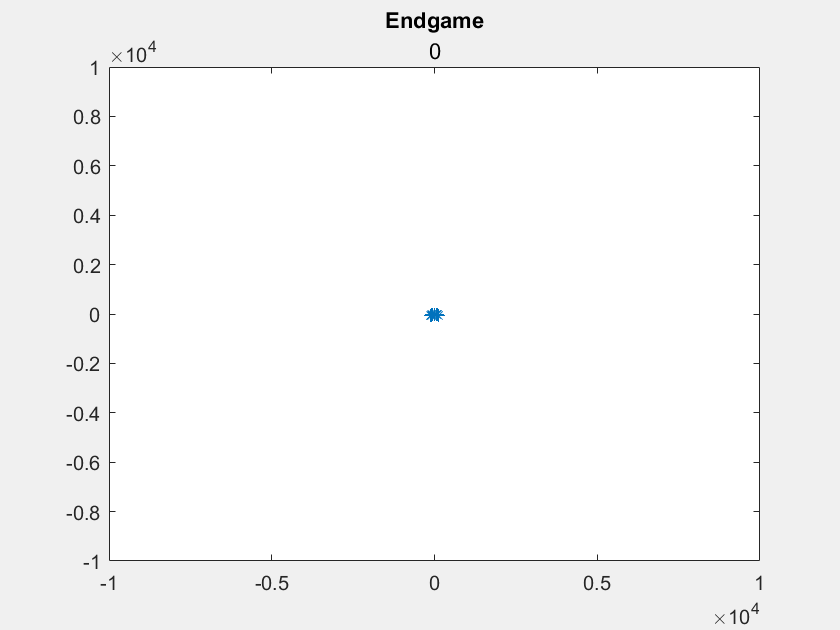

%cam.show

LaserPlot1.figure = figure('Name', 'Lidar Data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')

%CamPlot1.figure = figure('Name', 'Camera Data', 'NumberTitle','off',...
 %   'MenuBar','figure','Units','normalized','Visible','on');
%CamPlot1.axis1 = axes('parent', CamPlot1.figure, 'Units','normalized','NextPlot','replace');

outer = [1 2 3 7 8 9 10 11 12];
inner = [4 5 6 13 14 15 16];
target = [0 19];

writePosition(driveServo, 0.375);
writePosition(steerServo, 0.53);
pause(8);


while true

    turn = 0;   % Initialize variable for turn angle
    speed = 0.38;   % Initialize drive speed
    
    % Get camera data, including apriltag id and positions
    [position, aprila, aprilid] = cam.getAprilPosition();
    aprilx = position(1);
    aprily = position(2);
    desiredAngleInside = -87 * (0.6863 ^ aprily) + 87;
    desiredAngleOutside = 91.5 * (0.82 ^ aprily) + 89;

    % If it is the end apriltag, break the loop and move on
    if any(target == aprilid)
        title('Endgame')
        if aprily < 12
            break
        end
    end
    
    % Get and edit lidar data for navigation
    [lidar_data, pol_data] = lid.scan(10000);
    left_pol = pol_data(:, -40 < pol_data(1,:) < 0 & 250 < pol_data(2,:) < 1000);
    right_pol = pol_data(:, 0 < pol_data(1,:) < 40 & 250 < pol_data(2,:) < 1000);
    left = lidar_data(:, lidar_data(1,:) < -250 & 600 < lidar_data(2,:) < 4000);
    right = lidar_data(:, lidar_data(1,:) > 250 & 600 < lidar_data(2,:) < 4000);
    lefts = sort(sqrt(abs(2.*left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(2.*right(1,:).^2) + abs(right(2,:).^2)));

    %%%%% RANSAC Wall Estimation %%%%%%%
    if length(right) < 50
        rights = [20000; 20000];
        slope = 100000000000;
    else
        sampleSize = 2; % number of points to sample per trial
        maxDistance = 300; % max allowable distance for inliers
        rpoints = right'
        fitLineFcn = @(rpoints) polyfit(rpoints(:,1),rpoints(:,2),1); % fit function using polyfit
        evalLineFcn = ...   % distance evaluation function
          @(model, rpoints) sum((rpoints(:, 2) - polyval(model, rpoints(:,1))).^2,2);
        
        [modelRANSAC, inlierIdx] = ransac(rpoints,fitLineFcn,evalLineFcn, sampleSize,maxDistance);
        inlierPts = rpoints(inlierIdx,:);
        modelInliers = polyfit(rpoints(inlierIdx,1),rpoints(inlierIdx,2),1);
        x = [min(inlierPts(:,1)) max(inlierPts(:,1))];
        y = modelInliers(1)*x + modelInliers(2);
        slope = modelInliers(1)
    end

    if isempty(lefts)
        lefts = [20000; 20000];
    end

    clf

    %%%%% LIDAR and Cam Plotting %%%%%%
        plot(lidar_data(1,:), lidar_data(2,:), '*')
        hold on
        plot(left(1,:), left(2,:), 'b*')
        plot(right(1,:), right(2,:), 'r*')
        if (length(right) > 50)
            plot(x, y, 'g-')
        end
        range = 10000;
        axis([-range, range, -range, range])
    
    %%%%%% Decision Tree For Navigation %%%%%%%
    if min(lefts) < 2000 & min(rights) < 2000
        title('Obstacle Mode')
        %oleft = left(300 < left(2,:) < 600 & abs(left(2,:)) < 350);
        %oright = right(300 < right(2,:) < 600 & abs(right(2,:)) < 350);
        speed = 0.365;
        if isempty(left_pol) & isempty(right_pol)
            turn = 0;
        elseif isempty(left_pol)
            xlabel('Right')
            turn = 0.2;
        elseif isempyt(right_pol)
            xlabel('Left')
            turn = -0.2;
        elseif min(left_pol) < min(right_pol)
            xlabel('Right')
            turn = 0.2;
        else
            xlabel('Left')
            turn = -0.2;
        end
    elseif min(lefts) < 3000 & (min(lefts) < min(rights))
        title('Wall Left')
        turn = -max(300/min(lefts),0.5);
    elseif min(rights) < 3000 & (min(rights) < min(lefts))
        title('Wall Right')
        turn = max(300/min(lefts),0.5);
    elseif length(rights) < 50 & aprilid ~= -1
        title('AprilTag Mode')
        subtitle(aprilid)
        if any(outer == aprilid)
            if aprila < desiredAngleOutside
                xlabel('Outer Left')
                turn = -0.3;
            elseif aprila > desiredAngleInside
                xlabel('Outer Right')
                turn = 0.3;
            end
        elseif any(inner == aprilid)
            if aprila < desiredAngleInside
                xlabel('Inner Left')
                turn = -0.3;
            elseif aprila > desiredAngleInside
                xlabel('Inner Right')
                turn = 0.3;
            end
        end
    elseif slope > 0
        title('RANSAC Mode')
        turn = -0.2;
    elseif slope < 0
        title('RANSAC Mode')
        turn = 0.2;
    else
        turn = 0;
    end
    
    % Write turn angle and speed to servos
    %speed = 0.3;
    writePosition(driveServo, speed);
    writePosition(steerServo, turn*0.16 + 0.53)

    pause(0.1)
end


aprily = 10;

while aprily > 1
    [position, aprila, aprilid] = cam.getAprilPosition();
    aprilx = position(1);
    aprily = position(2);
    
    if aprilx > 0.5
        turn = 0.2;
    elseif aprilx < -0.5
        turn = -0.2;
    else
        turn = 0;
    end

    writePosition(steerServo, turn*0.16 + 0.52)

end

disp(aprilid)

    -1




writePosition(driveServo, 0.35);

## Inner Course

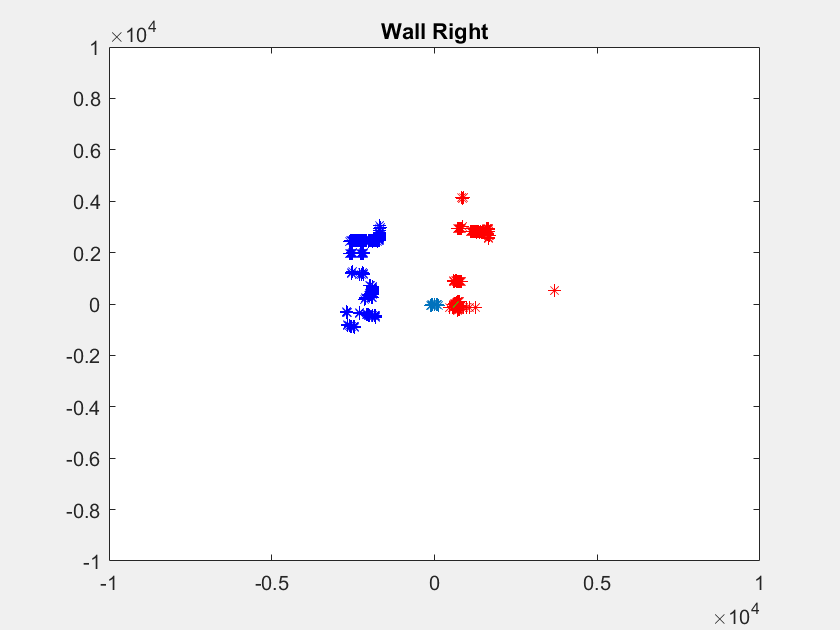

rpoints = 	1.0e+03 *

    0.4517   -0.1532
    0.7070   -0.2350
    0.7084   -0.2307
    0.7098   -0.2263
    0.7207   -0.2249
    0.7221   -0.2205
    0.7234   -0.2160
    0.7660   -0.2236
    0.7674   -0.2189
    0.7687   -0.2142


slope = 1.3901

rpoints = 	1.0e+03 *

    0.9328   -0.3164
    0.9565   -0.3180
    0.9899   -0.3223
    0.9918   -0.3162
    1.0061   -0.3140
    1.0081   -0.3078
    1.0099   -0.3016
    1.0002   -0.2920
    0.9693   -0.2766
    0.9710   -0.2706


slope = -0.2509

rpoints = 	1.0e+03 *

    1.1601   -0.3935
    1.1625   -0.3864
    1.1705   -0.3811
    1.1728   -0.3739
    1.4920   -0.4656
    1.6202   -0.4947
    1.6232   -0.4847
    1.5004   -0.4380
    1.0001   -0.2853
    0.9219   -0.2569


slope = -0.2197

rpoints = 	1.0e+03 *

    0.2533   -0.0877
    1.1335   -0.3845
    1.1359   -0.3776
    1.1382   -0.3706
    1.1404   -0.3636
    1.1427   -0.3566
    1.1821   -0.3609
    1.2341   -0.3686
    1.2364   -0.3610
    1.2386   -0.3534


slope = -0.2877

rpoints = 	1.0e+03 *

    4.6791   -1.5873
    2.3700    0.0983
    2.3693    0.1129
    2.3686    0.1274
    2.3837    0.1429
    2.3938    0.1583
    2.4077    0.1741
    2.4066    0.1888
    2.4084    0.2039
    2.4131    0.2192


slope = -0.4170

rpoints = 	1.0e+03 *

    2.4181   -0.4238
    2.4207   -0.4090
    2.4232   -0.3941
    2.4255   -0.3792
    2.4278   -0.3643
    2.4300   -0.3494
    2.4549   -0.3376
    2.4668   -0.3238
    2.4728   -0.3091
    2.4706   -0.2935


slope = -0.4670

rpoints = 	1.0e+03 *

    3.3268   -1.1286
    2.2378   -0.4206
    2.1961   -0.3988
    2.1650   -0.3795
    2.1417   -0.3618
    2.0965   -0.3410
    2.0550   -0.3213
    2.0332   -0.3051
    1.9767   -0.2842
    1.9596   -0.2695


slope = -0.4951

rpoints = 	1.0e+03 *

    2.6705   -0.9059
    2.6760   -0.8895
    2.6814   -0.8731
    2.5067   -0.7992
    2.4944   -0.7784
    2.4991   -0.7631
    2.4846   -0.7420
    2.4891   -0.7267
    2.4935   -0.7114
    2.5171   -0.7015


slope = -0.4350

rpoints = 	1.0e+03 *

    1.8755   -0.5727
    1.8790   -0.5611
    1.8824   -0.5496
    1.8858   -0.5380
    1.8938   -0.5278
    1.9009   -0.5172
    1.9069   -0.5063
    1.9158   -0.4960
    1.9217   -0.4850
    1.9247   -0.4732


slope = -0.3662

rpoints = 	1.0e+03 *

    1.9196   -0.6512
    1.9330   -0.6425
    1.9369   -0.6307
    1.9408   -0.6187
    1.9445   -0.6068
    4.7706   -1.3611
    1.7763   -0.4950
    1.7687   -0.4812
    1.7475   -0.4639
    1.7358   -0.4494


slope = -0.3163

rpoints = 	1.0e+03 *

    1.7207   -0.5837
    1.7252   -0.5735
    1.7696   -0.5762
    1.7731   -0.5653
    1.7765   -0.5544
    1.7799   -0.5435
    1.7832   -0.5325
    1.7931   -0.5235
    1.8261   -0.5210
    1.9746   -0.5242


slope = 3.0563

rpoints = 	1.0e+03 *

    2.0446   -0.6936
    2.0488   -0.6810
    2.0529   -0.6684
    2.0560   -0.6555
    2.0495   -0.6396
    2.0515   -0.6264
    2.0429   -0.6101
    2.0466   -0.5975
    2.0627   -0.5885
    1.9452   -0.4153


slope = 6.0073

rpoints = 	1.0e+03 *

    1.9739   -0.3460
    1.9760   -0.3338
    1.9464   -0.3166
    1.9483   -0.3046
    1.9551   -0.2934
    1.9767   -0.2842
    1.9645   -0.2701
    1.9661   -0.2581
    1.9677   -0.2460
    1.9443   -0.2310


slope = 9.1920

rpoints = 	1.0e+03 *

    2.0007   -0.3128
    1.9976   -0.2998
    1.9767   -0.2842
    1.9625   -0.2699
    1.9513   -0.2561
    1.9459   -0.2433
    1.9473   -0.2313
    1.9487   -0.2193
    1.9739   -0.2099
    1.9751   -0.1978


slope = 10.0361

rpoints = 	1.0e+03 *

    2.0390   -0.2932
    1.9942   -0.2742
    1.9780   -0.2596
    1.9756   -0.2470
    1.9622   -0.2331
    1.9616   -0.2208
    1.9540   -0.2078
    1.9473   -0.1950
    1.9564   -0.1838
    1.9575   -0.1718


slope = 10.2926

rpoints = 	1.0e+03 *

    1.9403   -0.3524
    1.9375   -0.3396
    1.9395   -0.3277
    1.9415   -0.3158
    2.0297   -0.2411
    2.0282   -0.2283
    1.9957   -0.2122
    1.9970   -0.2000
    1.9912   -0.1871
    1.9854   -0.1742


slope = 14.0498

rpoints = 	1.0e+03 *

    1.9187   -0.4968
    1.9179   -0.4840
    1.9208   -0.4722
    1.9237   -0.4604
    2.0572   -0.1678
    2.0332   -0.1533
    2.0112   -0.1392
    1.9891   -0.1254
    1.9878   -0.1131
    1.9854   -0.1007


slope = -0.2504

rpoints = 	1.0e+03 *

    1.9063   -0.6467
    1.9102   -0.6350
    1.9369   -0.6307
    1.9408   -0.6187
    2.0547   -0.1169
    2.0194   -0.1024
    2.0010   -0.0892
    1.9935   -0.0766
    1.9900   -0.0642
    1.9813   -0.0517


slope = 5.9566

rpoints = 	1.0e+03 *

    2.0431   -0.1414
    2.0320   -0.1281
    2.0327   -0.1156
    2.0224   -0.1026
    2.0130   -0.0897
    1.9885   -0.0764
    1.9860   -0.0641
    1.9703   -0.0514
    1.9696   -0.0393
    1.9628   -0.0271


slope = 1.1994

rpoints = 	1.0e+03 *

    2.0203   -0.0527
    1.9916   -0.0398
    1.9768   -0.0273
    1.9669   -0.0151
    1.9670   -0.0030
    1.9670    0.0091
    1.9959    0.0215
    1.9987    0.0338
    1.9985    0.0460
    1.9981    0.0583


slope = -0.4850

rpoints = 	1.0e+03 *

    1.9642    0.0573
    1.9528    0.0690
    1.9523    0.0810
    1.9518    0.0930
    1.9682    0.1059
    1.9675    0.1180
    1.9727    0.1304
    1.9719    0.1426
    1.9460    0.1527
    1.9391    0.1641


slope = -8.7419

rpoints = 	1.0e+03 *

    1.9292    0.1038
    1.9206    0.1151
    1.9098    0.1263
    1.9060    0.1378
    1.9051    0.1495
    1.9072    0.1614
    1.9131    0.1738
    1.9250    0.1868
    1.9238    0.1986
    1.9225    0.2104


slope = -8.0074

rpoints = 	1.0e+03 *

    1.8972    0.1606
    1.8842    0.1712
    1.8603    0.1805
    1.8522    0.1912
    1.8509    0.2026
    1.8497    0.2140
    1.8483    0.2253
    1.8687    0.2395
    1.8960    0.2548
    1.8944    0.2664


slope = -5.6566

rpoints = 	1.0e+03 *

    1.8467    0.2136
    1.8374    0.2240
    1.8281    0.2342
    1.8256    0.2453
    1.8211    0.2561
    1.8195    0.2673
    1.8010    0.2759
    1.7825    0.2843
    1.7807    0.2952
    1.8045    0.3106


slope = -4.3340

rpoints = 	1.0e+03 *

    1.7307    0.3088
    1.7130    0.3165
    1.7071    0.3263
    1.6933    0.3345
    1.6912    0.3448
    1.6891    0.3552
    1.6976    0.3679
    1.7470    0.3899
    1.7485    0.4015
    1.7489    0.4129


slope = -3.3939

rpoints = 	1.0e+03 *

    1.7759    0.3394
    1.7708    0.3498
    1.7647    0.3598
    1.7536    0.3688
    1.7513    0.3796
    1.7490    0.3903
    1.7310    0.3975
    1.7275    0.4079
    1.7162    0.4164
    1.6952    0.4223


slope = -2.7002

rpoints = 	1.0e+03 *

    1.7482    0.2568
    1.7308    0.2652
    1.7212    0.2745
    1.7195    0.2851
    1.7177    0.2956
    1.7149    0.3060
    1.7061    0.3153
    1.7041    0.3257
    1.6992    0.3356
    1.6902    0.3446


slope = -2.3630

rpoints = 	1.0e+03 *

    1.7195    0.1243
    1.7137    0.1345
    1.7129    0.1450
    1.7020    0.1546
    1.6960    0.1646
    1.6950    0.1750
    1.6889    0.1849
    1.6858    0.1950
    1.4661    0.1787
    1.4611    0.1872


slope = -2.1859

rpoints = 	1.0e+03 *

    1.7070   -0.0026
    1.6860    0.0078
    1.6859    0.0181
    1.6858    0.0285
    1.6826    0.0388
    1.6813    0.0491
    1.3861    0.0490
    1.3698    0.0568
    1.3694    0.0652
    1.3690    0.0736


slope = -2.0518

rpoints = 	1.0e+03 *

    1.6734   -0.1365
    1.6553   -0.1248
    1.3428   -0.0929
    1.3413   -0.0846
    1.3418   -0.0763
    1.3443   -0.0682
    1.3696   -0.0610
    1.3710   -0.0527
    1.3713   -0.0442
    1.3715   -0.0358


slope = -1.9604

rpoints = 	1.0e+03 *

    1.3427   -0.2867
    1.3445   -0.2784
    1.3462   -0.2702
    1.3517   -0.2627
    1.3602   -0.2557
    1.3617   -0.2473
    1.3632   -0.2389
    1.3016   -0.2199
    1.3029   -0.2119
    1.3042   -0.2039


slope = -2.0754

rpoints = 	1.0e+03 *

    1.2832   -0.4353
    1.3058   -0.4340
    1.3084   -0.4260
    1.3110   -0.4180
    1.3135   -0.4099
    1.3294   -0.4059
    1.3328   -0.3980
    1.3487   -0.3938
    1.3511   -0.3855
    1.3554   -0.3777


slope = -2.2807

rpoints = 	1.0e+03 *

    1.2984   -0.4494
    1.3173   -0.4469
    1.3247   -0.4403
    1.3274   -0.4322
    1.3300   -0.4240
    1.3278   -0.4144
    1.3304   -0.4062
    1.3242   -0.3955
    1.3189   -0.3851
    1.3184   -0.3761


slope = -2.4450

rpoints = 	1.0e+03 *

    1.1822   -0.4092
    1.2197   -0.4138
    1.2222   -0.4063
    1.2247   -0.3988
    1.2310   -0.3925
    1.2333   -0.3849
    1.2319   -0.3761
    1.2294   -0.3671
    1.2210   -0.3565
    1.2222   -0.3487


slope = -2.8594

rpoints = 	1.0e+03 *

    1.1094   -0.3840
    1.1354   -0.3852
    1.1416   -0.3795
    1.1439   -0.3725
    1.1462   -0.3654
    1.1484   -0.3584
    1.1506   -0.3513
    1.1508   -0.3437
    1.1481   -0.3352
    1.1482   -0.3276


slope = -3.1944

rpoints = 	1.0e+03 *

    1.0348   -0.3581
    1.0720   -0.3637
    1.0752   -0.3574
    1.0773   -0.3508
    1.0833   -0.3454
    1.0882   -0.3396
    1.0164   -0.2900
    1.0105   -0.2816
    1.0103   -0.2749
    1.0100   -0.2681


slope = -0.0811

rpoints = 	1.0e+03 *

    5.3034   -0.4325
    2.2636   -0.1706
    2.2237   -0.1539
    2.2226   -0.1401
    2.2234   -0.1265
    2.2052   -0.1118
    2.2058   -0.0983
    2.2064   -0.0847
    1.0616    0.1626
    1.0606    0.1692


slope = -3.6852

rpoints = 	1.0e+03 *

    2.2757   -0.4713
    2.2786   -0.4573
    2.2575   -0.4243
    3.5105    0.3407
    3.5084    0.3622
    3.5061    0.3837
    3.5036    0.4053
    1.0572    0.1289
    1.0564    0.1354
    1.0357    0.1392


slope = -5.7933

rpoints = 	1.0e+03 *

    3.5059   -0.0269
    3.4720   -0.0053
    3.4720    0.0160
    3.4718    0.0373
    3.5055    0.0592
    1.0463    0.0756
    1.0458    0.0821
    1.0373    0.0878
    0.9859    0.0896
    1.0103    0.0980


slope = -5.3885

rpoints = 	1.0e+03 *

    1.1007    0.0254
    1.1005    0.0321
    1.0463    0.0370
    0.9862    0.0409
    0.9859    0.0470
    0.9856    0.0530
    0.9693    0.0581
    0.9689    0.0641
    0.9755    0.0705
    0.9441    0.0741


slope = -7.0340

rpoints = 	1.0e+03 *

    1.1299   -0.0156
    1.1290   -0.0087
    1.0600   -0.0016
    1.0400    0.0048
    1.0079    0.0108
    1.0079    0.0170
    1.0007    0.0231
    1.0006    0.0292
    0.9934    0.0351
    0.9931    0.0412


slope = -4.6644

rpoints = 	1.0e+03 *

    1.0440   -0.0916
    1.0395   -0.0848
    1.0400   -0.0784
    1.0455   -0.0724
    1.0409   -0.0656
    1.0733   -0.0610
    1.1126   -0.0564
    1.0749   -0.0479
    1.0752   -0.0413
    1.0754   -0.0347


slope = -6.1480

rpoints = 	1.0e+03 *

    1.0946   -0.1780
    1.1214   -0.1753
    1.1224   -0.1684
    1.1234   -0.1615
    1.1403   -0.1568
    4.0322   -0.3788
    1.0490   -0.0920
    0.9917   -0.0809
    0.9383   -0.0707
    0.9358   -0.0648


slope = -7.1286

rpoints = 	1.0e+03 *

    1.1973   -0.2944
    1.1991   -0.2870
    1.1220   -0.2613
    1.0192   -0.2307
    0.8722   -0.1918
    0.8714   -0.1861
    0.8725   -0.1807
    0.8706   -0.1747
    0.8678   -0.1686
    0.8688   -0.1633


slope = -9.7462

rpoints = 	1.0e+03 *

    0.8325   -0.2881
    0.8703   -0.2952
    0.8740   -0.2905
    0.8757   -0.2851
    0.8851   -0.2822
    0.8878   -0.2770
    0.8895   -0.2716
    0.8911   -0.2661
    0.8927   -0.2606
    0.8943   -0.2552


slope = -16.2820

rpoints = 	1.0e+03 *

    0.8836   -0.3058
    0.8968   -0.3042
    0.8996   -0.2990
    0.9014   -0.2935
    0.9032   -0.2880
    0.9059   -0.2827
    0.9115   -0.2783
    0.9132   -0.2727
    0.9167   -0.2676
    0.9184   -0.2620


slope = 16.0592

rpoints = 	1.0e+03 *

    0.8666   -0.2999
    0.8921   -0.3026
    0.8949   -0.2975
    0.8967   -0.2920
    0.8984   -0.2864
    0.9059   -0.2827
    0.9105   -0.2780
    0.9122   -0.2724
    0.9071   -0.2648
    0.9087   -0.2593


slope = -18.2728

rpoints = 	1.0e+03 *

    0.8571   -0.2967
    0.8656   -0.2936
    0.8740   -0.2905
    0.8757   -0.2851
    0.8870   -0.2828
    0.8887   -0.2773
    0.8914   -0.2722
    0.8949   -0.2673
    0.8946   -0.2612
    0.8982   -0.2563


slope = 10.0931

rpoints = 	1.0e+03 *

    0.8354   -0.2891
    0.8637   -0.2930
    0.8702   -0.2893
    0.8719   -0.2839
    0.8746   -0.2788
    0.8773   -0.2738
    0.8875   -0.2710
    0.8892   -0.2655
    0.8908   -0.2601
    0.8837   -0.2521


slope = -5.7366

rpoints = 	1.0e+03 *

    0.8108   -0.2806
    0.8466   -0.2872
    0.8503   -0.2826
    0.8520   -0.2774
    0.8680   -0.2767
    0.8706   -0.2717
    0.8722   -0.2663
    0.8739   -0.2610
    0.8726   -0.2548
    0.8741   -0.2494


slope = -5.0057

rpoints = 249×2
  855.2257 -295.9965
  857.0276 -290.7382
  890.9619 -290.0962
  892.7269 -284.6185
  896.1557 -273.6312
  897.8194 -268.1220
  897.5293 -262.0421
  899.1219 -256.5246
  896.8273 -249.9237
  896.4155 -243.8858


slope = -6.7014

rpoints = 246×2
  852.3907 -295.0153
  868.3915 -294.5933
  883.4697 -293.6703
  875.7481 -285.1426
  877.4829 -279.7585
  879.1846 -274.3638
  880.8531 -268.9588
  882.4884 -263.5436
  884.0904 -258.1185
  885.6591 -252.6836


slope = -6.2449

rpoints = 248×2
  837.2707 -289.7822
  848.5047 -287.8469
  865.4397 -287.6770
  867.1903 -282.3562
  868.9081 -277.0247
  865.8202 -270.1932
  872.2454 -266.3305
  869.0738 -259.5375
  866.8118 -253.0738
  867.3881 -247.4708


slope = -5.0000

rpoints = 248×2
  820.2607 -283.8950
  830.5118 -281.7430
  847.4097 -281.6838
  839.6152 -273.3777
  844.1366 -269.1270
  849.5920 -265.1290
  851.2044 -259.9059
  848.9519 -253.5284
  850.4931 -248.3094
  844.3091 -240.8862


slope = -4.3756

rpoints = 246×2
  811.7557 -280.9514
  818.2009 -277.5667
  819.8903 -272.5361
  821.5487 -267.4953
  823.1761 -262.4444
  824.7725 -257.3836
  827.2942 -252.6051
  828.8300 -247.5192
  829.3747 -242.1437
  813.5370 -232.1068


slope = -4.3570

rpoints = 234×2
  736.1556 -254.7859
  750.9645 -254.7574
  764.8513 -254.2409
  764.4967 -248.9193
  766.0111 -244.2191
  769.4058 -240.1056
  770.8660 -235.3754
  772.2971 -230.6364
  773.6991 -225.8887
  775.0719 -221.1325


slope = -4.4444

rpoints = 222×2
  724.8156 -250.8611
  743.3886 -252.1873
  750.6171 -249.5094
  752.1354 -244.8944
  761.2474 -242.7003
  764.6328 -238.6161
  766.0840 -233.9153
  767.5062 -229.2057
  764.0999 -223.0861
  764.4940 -218.1145


slope = -4.6098

rpoints = 203×2
  729.5406 -252.4965
  750.9645 -254.7574
  753.4640 -250.4557
  754.9880 -245.8232
  756.4836 -241.1816
  757.9507 -236.5308
  753.6506 -230.1189
  735.8861 -219.7627
  737.2220 -215.2389
  738.5300 -210.7069


slope = -4.4572

rpoints = 176×2
  730.4856 -252.8235
  757.5934 -257.0062
  762.0045 -253.2946
  763.5458 -248.6097
  766.9639 -244.5229
  773.2242 -241.2971
  774.6917 -236.5435
  772.2971 -230.6364
  773.6991 -225.8887
  772.1870 -220.3094


slope = 10.1005

rpoints = 150×2
  761.6707 -263.6168
  771.7983 -261.8250
  779.0855 -258.9724
  780.6614 -254.1825
  782.2079 -249.3830
  787.5432 -245.7656
  789.0378 -240.9240
  790.5026 -236.0733
  790.9777 -230.9334
  792.3812 -226.0709


slope = -4.4908

rpoints = 116×2
  797.5807 -276.0454
  812.5190 -275.6391
  825.5840 -274.4287
  827.2539 -269.3529
  828.8926 -264.2670
  831.4547 -259.4689
  833.0326 -254.3573
  833.6210 -248.9500
  834.1743 -243.5450
  835.6544 -238.4170


slope = 5.5676

rpoints = 100×2
  824.0407 -285.2033
  838.0877 -284.3131
  845.5118 -281.0529
  847.2221 -275.8546
  850.8059 -271.2533
  861.0472 -268.7037
  862.6813 -263.4102
  864.2829 -258.1068
  865.8518 -252.7936
  865.4649 -246.9221


slope = 3.7362

rpoints = 78×2
  862.7857 -298.6131
  926.1723 -307.8649
  924.2423 -300.9322
  929.8841 -296.4650
  927.8691 -289.5566
  929.6300 -283.8522
  870.0320 -259.8237
  869.6915 -253.9146
  870.2730 -248.2939
  871.7816 -242.9441


slope = 6.0417

rpoints = 86×2
	1.0e+03 *

    3.4035   -1.1546
    3.8279   -1.1432
    3.7936   -1.1076
    3.7859   -1.0801
    3.7694   -1.0504
    3.7989   -1.0336
    3.8120   -1.0120
    3.7881   -0.9808
    3.7892   -0.9563
    3.7950   -0.9330


slope = 1.1412

rpoints = 77×2
	1.0e+03 *

    0.9745   -0.2332
    0.9720   -0.2263
    0.9597   -0.2173
    0.9610   -0.2114
    0.9349   -0.1996
    0.9254   -0.1916
    0.9265   -0.1860
    0.9384   -0.1824
    0.9769   -0.1836
    1.0420   -0.1892


slope = 5.5005

rpoints = 81×2
	1.0e+03 *

    0.4877   -0.1654
    3.7398   -1.2431
    1.0798   -0.3297
    1.0770   -0.3216
    1.0732   -0.3133
    1.0386   -0.2963
    1.0124   -0.2821
    1.0141   -0.2759
    1.0264   -0.2725
    1.0010   -0.2592


slope = -0.1086

rpoints = 95×2
	1.0e+03 *

    0.9574   -0.3248
    1.0498   -0.3418
    1.0233   -0.3262
    1.0291   -0.3211
    1.0310   -0.3148
    1.0310   -0.3079
    1.0329   -0.3016
    1.0347   -0.2952
    1.0365   -0.2888
    1.0055   -0.2736


slope = 2.2825

rpoints = 88×2
	1.0e+03 *

    1.0474   -0.3553
    1.0583   -0.3446
    1.0604   -0.3381
    1.0625   -0.3316
    1.0645   -0.3250
    1.1268   -0.3365
    1.1778   -0.3439
    1.1703   -0.3339
    1.1723   -0.3267
    1.1743   -0.3195


slope = 3.3663

rpoints = 95×2
	1.0e+03 *

    0.9243   -0.3135
    1.1473   -0.3814
    1.1971   -0.3898
    1.1995   -0.3824
    1.2257   -0.3825
    1.2280   -0.3750
    1.2303   -0.3674
    1.1615   -0.3391
    1.1636   -0.3320
    1.1656   -0.3248


slope = 3.0142

rpoints = 103×2
	1.0e+03 *

    1.1866   -0.4025
    1.2033   -0.4000
    1.2323   -0.4012
    1.2348   -0.3937
    1.2372   -0.3861
    1.2395   -0.3785
    1.2370   -0.3694
    1.2393   -0.3618
    1.2309   -0.3512
    1.2330   -0.3436


slope = 3.2958

rpoints = 101×2
	1.0e+03 *

    1.2663   -0.4383
    1.2983   -0.4404
    1.3067   -0.4344
    1.3036   -0.4245
    1.3119   -0.4183
    3.8709   -1.2080
    3.8782   -1.1842
    1.3606   -0.4063
    2.3605   -0.6892
    2.3646   -0.6746


slope = 2.6588

rpoints = 119×2
	1.0e+03 *

    1.4128   -0.4890
    1.4640   -0.4967
    1.6464   -0.5473
    1.6498   -0.5372
    2.0837   -0.6643
    2.0877   -0.6515
    2.0917   -0.6387
    1.4229   -0.4249
    1.4236   -0.4156
    1.4261   -0.4069


slope = 2.5853

rpoints = 114×2
	1.0e+03 *

    1.4733   -0.5099
    1.4820   -0.5028
    1.4889   -0.4949
    1.4919   -0.4858
    1.4968   -0.4772
    1.5044   -0.4695
    1.5073   -0.4602
    1.5082   -0.4504
    1.5109   -0.4411
    1.5098   -0.4307


slope = 3.2207

rpoints = 111×2
	1.0e+03 *

    1.4865   -0.5145
    1.5142   -0.5137
    1.5316   -0.5091
    1.5347   -0.4997
    1.5454   -0.4927
    1.5484   -0.4832
    1.5532   -0.4743
    1.5561   -0.4647
    1.5589   -0.4551
    1.5617   -0.4456


slope = 4.3739

rpoints = 100×2
	1.0e+03 *

    1.5007   -0.5194
    1.5114   -0.5127
    1.5344   -0.5101
    1.5376   -0.5006
    1.5492   -0.4939
    1.5541   -0.4850
    1.5704   -0.4795
    1.5753   -0.4704
    1.5820   -0.4619
    1.5867   -0.4527


slope = 4.7374

rpoints = 89×2
	1.0e+03 *

    1.5322   -0.5198
    1.5572   -0.5176
    1.5632   -0.5090
    1.5663   -0.4994
    1.5760   -0.4918
    1.5876   -0.4848
    1.5925   -0.4756
    1.5973   -0.4664
    1.6021   -0.4571
    1.6048   -0.4472


slope = 2.1231

rpoints = 81×2
	1.0e+03 *

    1.5800   -0.5469
    1.5834   -0.5371
    1.5866   -0.5274
    1.5670   -0.5102
    1.5701   -0.5006
    1.5732   -0.4909
    1.5771   -0.4816
    1.5963   -0.4767
    1.6184   -0.4725
    1.6261   -0.4639


slope = 2.1120

rpoints = 68×2
	1.0e+03 *

    1.6018   -0.5544
    1.6080   -0.5455
    1.6123   -0.5359
    1.6155   -0.5260
    1.6263   -0.5185
    1.6295   -0.5085
    1.6326   -0.4985
    1.6433   -0.4907
    1.6386   -0.4784
    1.6492   -0.4705


slope = 2.5547

rpoints = 70×2
	1.0e+03 *

    1.6150   -0.5590
    1.6260   -0.5516
    1.6312   -0.5422
    1.6345   -0.5322
    1.6425   -0.5237
    1.6457   -0.5136
    1.6498   -0.5038
    1.6557   -0.4945
    1.6559   -0.4834
    1.6617   -0.4741


slope = 1.9289

rpoints = 69×2
	1.0e+03 *

    1.5275   -0.5182
    1.5344   -0.5101
    1.5956   -0.5195
    1.6149   -0.5149
    1.6180   -0.5049
    1.6211   -0.4950
    1.6241   -0.4850
    1.6261   -0.4748
    1.5876   -0.4530
    1.5779   -0.4397


slope = -0.2796

rpoints = 63×2
	1.0e+03 *

    4.5804   -1.5853
    4.6089   -1.5006
    4.6180   -1.4723
    1.8949   -0.5913
    1.8832   -0.5750
    1.8455   -0.5511
    1.8488   -0.5398
    1.8521   -0.5284
    1.8553   -0.5170
    1.8469   -0.5025


slope = -0.3405

rpoints = 53×2
	1.0e+03 *

    1.7244   -0.1727
    1.7254   -0.1621
    1.7015   -0.1493
    1.6854   -0.1375
    1.6752   -0.1263
    1.6760   -0.1160
    1.6877   -0.1064
    1.6923   -0.0962
    1.7537   -0.0889
    1.7603   -0.0784


slope = 0.0156

rpoints = 64×2
	1.0e+03 *

    1.7084   -0.2456
    1.7099   -0.2351
    1.7113   -0.2246
    1.7186   -0.2149
    1.7259   -0.2050
    1.7271   -0.1944
    1.7223   -0.1832
    1.7234   -0.1726
    1.7125   -0.1609
    1.7025   -0.1494


slope = 0.0149

rpoints = 57×2
	1.0e+03 *

    1.7385   -0.2173
    1.7189   -0.2042
    1.7142   -0.1930
    1.7153   -0.1824
    1.7204   -0.1723
    1.7214   -0.1617
    1.7224   -0.1511
    1.7233   -0.1406
    1.7141   -0.1292
    1.7149   -0.1187


slope = -0.0303

rpoints = 57×2
	1.0e+03 *

    1.7004   -0.3740
    1.6938   -0.3617
    1.6901   -0.3500
    1.6981   -0.3408
    1.7002   -0.3304
    1.7542   -0.1757
    1.7553   -0.1649
    1.7483   -0.1534
    1.7492   -0.1427
    1.7271   -0.1302


slope = 0.0542

rpoints = 58×2
	1.0e+03 *

    1.6519   -0.5717
    1.6553   -0.5616
    1.6834   -0.5596
    1.6868   -0.5492
    1.6902   -0.5389
    1.7762   -0.2221
    1.7696   -0.2102
    1.7698   -0.1992
    1.7670   -0.1879
    1.7463   -0.1749


slope = -0.0407

rpoints = 54×2
	1.0e+03 *

    1.7964   -0.2134
    1.7887   -0.2013
    1.7869   -0.1900
    1.7741   -0.1777
    1.7573   -0.1651
    1.7582   -0.1543
    1.7592   -0.1435
    1.7700   -0.1334
    1.7708   -0.1225
    1.7715   -0.1117


slope = -0.0103

rpoints = 52×2
	1.0e+03 *

    1.8234   -0.2393
    1.8248   -0.2281
    1.8262   -0.2169
    1.8220   -0.1712
    1.7991   -0.1579
    1.7990   -0.1467
    1.7999   -0.1357
    1.8007   -0.1246
    1.7924   -0.1130
    1.7931   -0.1020


slope = -0.0221

rpoints = 58×2
	1.0e+03 *

    1.8843   -0.2591
    1.8828   -0.2471
    1.8675   -0.2335
    1.8500   -0.2198
    1.8513   -0.2084
    1.8526   -0.1970
    1.8726   -0.1875
    1.9016   -0.1786
    1.9027   -0.1670
    1.9037   -0.1553


slope = -0.8530

rpoints = 55×2
	1.0e+03 *

    1.8866   -0.1889
    1.8708   -0.1757
    1.8589   -0.1631
    1.8409   -0.1501
    1.8418   -0.1388
    1.8615   -0.1288
    1.8773   -0.1183
    1.8780   -0.1068
    1.8786   -0.0953
    1.8751   -0.0836


slope = -0.8295

rpoints = 59×2
	1.0e+03 *

    1.8615   -0.1288
    1.8613   -0.1173
    1.8560   -0.1056
    1.8526   -0.0940
    1.8632   -0.0830
    1.8636   -0.0716
    1.8790   -0.0606
    1.9113   -0.0499
    1.9116   -0.0382
    1.9118   -0.0264


slope = -0.6090

rpoints = 67×2
	1.0e+03 *

    1.8592   -0.0828
    1.8586   -0.0714
    1.8590   -0.0600
    1.8524   -0.0484
    1.8226   -0.0364
    1.8188   -0.0251
    1.8189   -0.0140
    1.8190   -0.0028
    1.8240    0.0084
    1.8239    0.0196


slope = 3.9675

rpoints = 54×2
	1.0e+03 *

    1.8466   -0.0369
    1.8468   -0.0255
    1.8609   -0.0143
    1.8610   -0.0029
    1.8610    0.0086
    1.8609    0.0200
    1.8467    0.0312
    1.8465    0.0425
    1.8442    0.0538
    1.8438    0.0651


slope = -2.8770

rpoints = 55×2
	1.0e+03 *

    1.9718   -0.1121
    1.9555   -0.0992
    1.9541   -0.0871
    1.9536   -0.0750
    1.9530   -0.0630
    1.9503   -0.0509
    1.9506   -0.0389
    1.9458   -0.0269
    1.9429   -0.0149
    1.9260   -0.0030


slope = 0.6732

rpoints = 59×2
	1.0e+03 *

    1.9537   -0.2199
    1.9420   -0.2065
    1.9433   -0.1946
    1.9444   -0.1827
    1.9445   -0.1706
    1.9455   -0.1587
    1.9455   -0.1467
    1.9463   -0.1347
    1.9342   -0.1219
    1.9349   -0.1100


slope = -1.1189

rpoints = 88×2
	1.0e+03 *

    1.9425   -0.3282
    1.9425   -0.3159
    1.9444   -0.3040
    1.9403   -0.2911
    1.9341   -0.2781
    1.9318   -0.2657
    1.9324   -0.2537
    1.9339   -0.2418
    1.9195   -0.2280
    1.9189   -0.2160


slope = -5.3545

rpoints = 79×2
	1.0e+03 *

    1.9713   -0.4718
    1.9508   -0.4543
    1.9389   -0.4390
    1.9269   -0.4238
    1.9197   -0.4099
    1.9222   -0.3981
    1.9246   -0.3863
    1.9270   -0.3745
    1.9292   -0.3626
    1.6539   -0.3004


slope = -2.2927

rpoints = 120×2
	1.0e+03 *

    1.9745   -0.6698
    1.9786   -0.6577
    2.0120   -0.6551
    1.9865   -0.6333
    1.9531   -0.6095
    1.6517   -0.5043
    1.6529   -0.4936
    1.6559   -0.4834
    1.6607   -0.4738
    1.6742   -0.4666


slope = -2.4482

rpoints = 114×2
	1.0e+03 *

    1.7169   -0.5824
    1.8021   -0.5990
    1.9117   -0.5454
    1.8977   -0.5288
    1.8999   -0.5169
    1.8973   -0.5037
    1.8858   -0.4883
    1.8888   -0.4767
    1.8849   -0.4634
    1.8848   -0.4511


slope = -1.6726

rpoints = 100×2
	1.0e+03 *

    2.0304   -0.6888
    5.1367   -1.7075
    2.2531   -0.6130
    2.2568   -0.5991
    1.6746    0.1211
    1.6360    0.1284
    1.6352    0.1384
    1.6074    0.1460
    1.5985    0.1551
    1.5975    0.1649


slope = -1.8263

rpoints = 98×2
	1.0e+03 *

    1.6060   -0.0123
    1.5990   -0.0025
    1.5970    0.0074
    1.5989    0.0172
    1.5968    0.0270
    1.5966    0.0368
    1.6923    0.1119
    1.6577    0.1198
    1.6120    0.1265
    1.5903    0.1346


slope = -1.8895

rpoints = 94×2
	1.0e+03 *

    1.5853   -0.2379
    1.5807   -0.2273
    1.5811   -0.2174
    1.5795   -0.2073
    1.5807   -0.1976
    1.5849   -0.1883
    1.6178   -0.1821
    1.8666    0.1119
    1.7771    0.1175
    1.6198    0.1171


slope = 2.8347

rpoints = 67×2
	1.0e+03 *

    1.5702   -0.4376
    1.5709   -0.4274
    1.5658   -0.4157
    1.5683   -0.4061
    1.5707   -0.3964
    1.5974   -0.3927
    1.6095   -0.3852
    1.6720    0.1002
    1.6524    0.1093
    1.6357    0.1183


slope = 2.7080

rpoints = 65×2
	1.0e+03 *

    2.4627   -0.0794
    2.4632   -0.0643
    2.4635   -0.0492
    2.8097   -0.0388
    1.6046    0.0370
    1.5943    0.0465
    1.4821    0.0524
    1.4817    0.0615
    1.4813    0.0706
    1.5338    0.0825


slope = 2.5371

rpoints = 99×2
	1.0e+03 *

    3.1705   -0.8209
    3.1754   -0.8014
    3.1803   -0.7819
    3.3076   -0.7917
    2.9197   -0.2201
    2.9210   -0.2022
    2.9222   -0.1842
    5.1676    0.1190
    5.1668    0.1508
    4.9999    0.1766


slope = -1.9779

rpoints = 80×2
	1.0e+03 *

    3.2786   -1.0011
    3.2847   -0.9809
    3.3365   -0.6697
    3.3405   -0.6492
    2.9621   -0.5568
    2.9655   -0.5386
    3.3519   -0.5875
    3.3926   -0.1721
    3.3936   -0.1512
    1.5223    0.0725


slope = -2.2159

rpoints = 100×2
	1.0e+03 *

    2.0241   -0.6728
    2.9980   -0.8157
    2.4944   -0.3586
    2.4965   -0.3433
    2.4986   -0.3280
    2.8358   -0.2840
    2.3805   -0.2236
    2.3081   -0.2025
    2.3093   -0.1884
    2.3094   -0.1741


slope = -2.3671

rpoints = 67×2
	1.0e+03 *

    5.3672   -0.1401
    5.0270   -0.1004
    4.9415   -0.0683
    2.0259   -0.0156
    2.0260   -0.0031
    1.8790    0.0087
    1.7149    0.0184
    1.6438    0.0278
    1.6166    0.0372
    1.6013    0.0467


slope = -2.4933

rpoints = 101×2
	1.0e+03 *

    2.5569   -0.8674
    2.7026   -0.8984
    2.3437   -0.6999
    2.3278   -0.6796
    2.3319   -0.6653
    2.3360   -0.6510
    2.3428   -0.6374
    2.3477   -0.6233
    2.3524   -0.6091
    2.3561   -0.5946


slope = 3.1820

rpoints = 87×2
	1.0e+03 *

    2.3984   -0.8301
    2.4035   -0.8154
    2.4084   -0.8006
    2.3990   -0.7811
    2.4019   -0.7658
    2.4046   -0.7504
    2.4092   -0.7356
    2.4089   -0.7194
    2.4056   -0.7023
    2.4060   -0.6864


slope = 2.0869

rpoints = 72×2
	1.0e+03 *

    2.4372   -0.8435
    2.4508   -0.8314
    2.4559   -0.8163
    2.4608   -0.8012
    2.4610   -0.7846
    2.4657   -0.7695
    2.4656   -0.7529
    2.4702   -0.7377
    2.4747   -0.7225
    2.4791   -0.7073


slope = 3.9054

rpoints = 60×2
	1.0e+03 *

    2.5128   -0.8697
    2.5247   -0.8565
    2.5299   -0.8410
    2.5284   -0.8232
    2.5257   -0.8053
    2.5287   -0.7891
    2.5335   -0.7736
    2.5401   -0.7586
    3.7143   -0.7931
    2.5332   -0.5246


slope = -1.2891

rpoints = 61×2
	1.0e+03 *

    2.6800   -0.9276
    1.5203   -0.3837
    1.5159   -0.3727
    1.5181   -0.3634
    1.5232   -0.3547
    1.5264   -0.3456
    1.5285   -0.3362
    1.5383   -0.3285
    2.4285   -0.4565
    2.4194   -0.4394


slope = -1.6944

rpoints = 75×2
	1.0e+03 *

    1.4830   -0.5031
    1.4861   -0.4940
    1.4900   -0.4851
    1.4930   -0.4760
    1.4978   -0.4674
    1.5083   -0.4605
    1.5695   -0.4687
    1.6088   -0.4697
    2.5170   -0.6517
    2.5006   -0.6311


slope = -1.6106

rpoints = 61×2
	1.0e+03 *

    2.6001   -0.8643
    2.6054   -0.8483
    2.6105   -0.8323
    2.5908   -0.8085
    2.5574   -0.7809
    2.5421   -0.7592
    2.5102   -0.7329
    2.5147   -0.7174
    2.4872   -0.6931
    2.4914   -0.6778


slope = -1.4730

rpoints = 76×2
	1.0e+03 *

    2.6232   -0.8899
    2.6286   -0.8738
    2.6339   -0.8576
    2.5667   -0.8183
    2.5411   -0.7930
    2.4981   -0.7628
    2.4769   -0.7397
    2.4641   -0.7194
    2.4454   -0.6977
    2.4362   -0.6789


slope = -0.9546

rpoints = 79×2
	1.0e+03 *

    2.5266   -0.8571
    2.5318   -0.8416
    2.5369   -0.8260
    2.4857   -0.7925
    2.4686   -0.7704
    2.4360   -0.7438
    2.4165   -0.7217
    2.4046   -0.7020
    2.4079   -0.6870
    2.3764   -0.6623


slope = -0.9738

rpoints = 67×2
	1.0e+03 *

    2.4641   -0.8359
    2.5356   -0.8428
    3.7572   -0.7062
    3.7369   -0.6787
    3.7410   -0.6557
    3.7449   -0.6327
    3.7468   -0.6094
    3.7376   -0.5843
    3.7352   -0.5605
    3.7386   -0.5375


slope = 0.4385

rpoints = 62×2
	1.0e+03 *

    2.4660   -0.8366
    2.8801   -0.9573
    1.2363   -0.2324
    1.2299   -0.2234
    1.2293   -0.2155
    1.2296   -0.2077
    1.2210   -0.1986
    1.2222   -0.1911
    1.2233   -0.1836
    1.2363   -0.1778


slope = -3.1951

rpoints = 69×2
	1.0e+03 *

    1.2060   -0.3682
    1.2054   -0.3600
    1.2047   -0.3517
    1.2030   -0.3432
    1.2003   -0.3345
    1.2023   -0.3271
    1.2043   -0.3197
    1.2227   -0.3166
    1.2624   -0.3186
    1.2711   -0.3125


slope = 0.1083

rpoints = 66×2
	1.0e+03 *

    1.3581   -0.4147
    1.3606   -0.4063
    1.3631   -0.3980
    1.3934   -0.3975
    3.7425   -0.7034
    3.7152   -0.6747
    3.7193   -0.6519
    3.7232   -0.6290
    3.0520   -0.1360
    3.0527   -0.1172


slope = 0.6197

rpoints = 52×2
  912.3035  376.6582
  852.8115  358.2424
  836.8017  357.5794
  826.3355  359.1249
  807.6502  356.9176
  784.4630  352.4455
  744.0790  339.8095
  741.9779  344.3731
  739.8488  348.9238
  757.5319  362.9675


slope = 0.5353

rpoints = 75×2
  939.4421  315.4829
  899.6467  308.2803
  884.5205  309.1805
  879.7790  313.6000
  852.4599  309.7760
  830.8484  307.7125
  750.3523  283.1527
  745.7988  286.6796
  734.7120  287.6095
  729.2160  290.6357


slope = 0.4034

rpoints = 80×2
	1.0e+03 *

    2.9461   -0.9994
    0.8730    0.2462
    0.8714    0.2515
    0.8651    0.2555
    0.8683    0.2622
    0.8619    0.2661
    0.8574    0.2704
    0.8443    0.2720
    0.7362    0.2422
    0.7347    0.2467


slope = 0.2481

rpoints = 87×2
  940.1510  221.9730
  901.8411  218.7843
  872.3404  217.3092
  832.2355  212.7558
  798.9921  209.4936
  791.8960  212.8397
  788.6456  217.1684
  787.2969  222.0081
  711.9384  205.4865
  707.7857  209.0057


slope = -1.1691

rpoints = 108×2
  910.5162  174.0380
  860.3778  169.9384
  856.3783  174.6202
  838.6536  176.3779
  835.5999  181.1019
  798.3601  178.1715
  768.9864  176.5813
  765.9409  180.8414
  763.8439  185.3065
  758.8100  189.0276


slope = -0.6466

rpoints = 131×2
	1.0e+03 *

    2.9484   -1.0205
    0.8732    0.1010
    0.8725    0.1064
    0.8292    0.1063
    0.8286    0.1113
    0.8279    0.1164
    0.8271    0.1215
    0.8244    0.1263
    0.7426    0.1184
    0.7103    0.1178


slope = -0.4041

rpoints = 155×2
  713.2594  -62.5860
  610.9712  -49.8312
  608.2743  -45.8522
  607.5468  -42.0464
  607.7936  -38.3141
  605.0223  -34.4100
  608.2184  -30.8453
  608.3963  -27.1092
  603.5550  -23.1801
  603.6860  -19.4727


slope = 0.3109

rpoints = 182×2
  585.9005 -202.7821
  594.7109 -201.7498
  595.9388 -198.0934
  597.1442 -194.4295
  598.3271 -190.7582
  596.6236 -186.1861
  592.9739 -181.0580
  593.1165 -177.1265
  594.1932 -173.4803
  595.2475 -169.8275


slope = -0.2870

rpoints = 176×2
	1.0e+03 *

    1.0139   -0.1015
    1.0016   -0.0941
    1.0021   -0.0879
    0.9897   -0.0807
    1.0161   -0.0766
    1.0060   -0.0634
    1.0064   -0.0572
    1.0067   -0.0511
    0.9590   -0.0427
    1.0073   -0.0387


slope = -0.3527

rpoints = 188×2
	1.0e+03 *

    1.2914   -0.2427
    1.2929   -0.2348
    1.2864   -0.2255
    1.2956   -0.2189
    1.2970   -0.2109
    1.2982   -0.2030
    1.2965   -0.1945
    1.2977   -0.1866
    1.2928   -0.1778
    1.2850   -0.1687


slope = 0.3016

rpoints = 206×2
	1.0e+03 *

    1.2121   -0.4112
    1.2782   -0.4249
    1.2808   -0.4170
    1.2843   -0.4095
    1.2878   -0.4019
    1.2902   -0.3939
    1.2907   -0.3854
    1.2767   -0.3727
    1.2742   -0.3635
    1.2754   -0.3554


slope = -0.4644

rpoints = 190×2
	1.0e+03 *

    1.2851   -0.4359
    1.3171   -0.4378
    1.3217   -0.4303
    1.3243   -0.4222
    1.3269   -0.4141
    1.3275   -0.4053
    1.3165   -0.3932
    1.3189   -0.3851
    1.3203   -0.3767
    1.3236   -0.3688


slope = 0.7877

rpoints = 178×2
  313.7403 -108.5866
  509.4816 -172.8366
  514.3293 -170.9660
  521.0749 -169.6614
  522.1071 -166.4578
  523.1196 -163.2479
  524.1124 -160.0319
  525.0854 -156.8099
  517.3993 -151.0596
  518.3173 -147.8789


slope = -0.1736

rpoints = 144×2
	1.0e+03 *

    1.4672   -0.3895
    1.4695   -0.3805
    1.4631   -0.3693
    1.4450   -0.3552
    1.4471   -0.3464
    1.4434   -0.3361
    1.4435   -0.3268
    1.4328   -0.3151
    1.4249   -0.3042
    1.4160   -0.2933


slope = -0.7204

rpoints = 146×2
	1.0e+03 *

    1.4707   -0.4989
    1.4737   -0.4899
    1.4767   -0.4808
    1.4596   -0.4654
    1.4300   -0.4463
    1.4270   -0.4357
    1.4018   -0.4186
    1.3919   -0.4064
    1.3549   -0.3866
    1.3573   -0.3782


slope = -0.9352

rpoints = 170×2
	1.0e+03 *

    3.8977   -1.2427
    3.9053   -1.2187
    0.9975   -0.3046
    3.9199   -1.1706
    3.9319   -1.1479
    3.9388   -1.1238
    0.9733   -0.2584
    0.9381   -0.2429
    0.9347   -0.2359
    0.9264   -0.2278


slope = -0.3291

rpoints = 221×2
  774.6393 -262.7888
  809.4519 -269.0663
  817.7452 -266.2569
  819.3651 -261.2294
  832.4093 -259.7668
  831.1198 -253.7733
  849.9101 -253.8145
  851.4530 -248.5897
  850.0788 -242.5324
  846.7359 -235.9645


slope = -0.5942

rpoints = 200×2
  908.1651 -308.0861
  988.8028 -328.6836
  990.8029 -322.6043
  992.7656 -316.5128
  994.6909 -310.4094
  982.2325 -299.9138
  972.5578 -290.4416
  925.3672 -270.1696
  927.0091 -264.4810
  928.6160 -258.7825


slope = -0.3873

rpoints = 162×2
  868.3915 -294.5933
  961.3261 -313.0067
  944.1754 -301.0213
  965.0984 -301.1746
  947.8018 -289.4008
  968.7250 -289.2970
  951.2851 -277.7366
  873.1579 -249.1170
  874.6715 -243.7495
  876.1521 -238.3727


slope = -0.3782

rpoints = 146×2
	1.0e+03 *

    0.9545   -0.2914
    0.9563   -0.2856
    3.8984   -1.1122
    3.8859   -1.0829
    3.8925   -1.0590
    3.8989   -1.0351
    3.9052   -1.0111
    0.8377   -0.2114
    0.8342   -0.2051
    0.8403   -0.2011


slope = -0.4214

rpoints = 141×2
  866.4975 -293.9508
  874.9292 -290.8314
  876.6990 -285.4522
  878.4356 -280.0622
  873.4570 -272.5764
  817.7301 -249.6848
  805.8336 -240.6516
  807.2965 -235.6978
  808.7289 -230.7350
  839.0296 -233.8169


slope = 1.3603

rpoints = 103×2
	1.0e+03 *

    0.9110   -0.3153
    1.0502   -0.3563
    1.0524   -0.3498
    0.9252   -0.3012
    0.9270   -0.2956
    0.9260   -0.2890
    0.9248   -0.2824
    0.8700   -0.2598
    0.8399   -0.2452
    0.8414   -0.2401


slope = -0.5515

rpoints = 96×2
	1.0e+03 *

    0.9970   -0.3451
    1.0322   -0.3502
    1.0970   -0.3646
    1.0735   -0.3495
    1.0757   -0.3429
    1.0777   -0.3363
    1.0549   -0.3221
    1.0569   -0.3156
    1.0588   -0.3091
    1.0674   -0.3045


slope = 0.6961

rpoints = 66×2
	1.0e+03 *

    1.3618   -0.4620
    4.3965   -1.4614
    4.4054   -1.4344
    1.5387   -0.4906
    1.5417   -0.4811
    4.4310   -1.3530
    4.6510   -1.3890
    4.6595   -1.3604
    4.6677   -1.3317
    4.6884   -1.3065


slope = -0.2813

rpoints = 105×2
	1.0e+03 *

    2.9953   -1.0161
    3.0376   -1.0097
    3.0884   -1.0056
    3.2136   -1.0246
    1.4293   -0.2777
    1.3867   -0.2606
    1.3539   -0.2459
    1.3504   -0.2367
    1.3469   -0.2276
    1.3483   -0.2193


slope = -0.4959

rpoints = 70×2
	1.0e+03 *

    2.7845   -0.7392
    2.6816   -0.6943
    2.6780   -0.6759
    2.6821   -0.6594
    2.6861   -0.6429
    2.6355   -0.6137
    2.6226   -0.5938
    2.5383   -0.5583
    2.5417   -0.5427
    2.5450   -0.5271


slope = 0.9410

rpoints = 59×2
	1.0e+03 *

    2.7879   -0.9458
    2.7937   -0.9286
    2.7994   -0.9115
    2.8001   -0.8927
    2.8056   -0.8755
    2.8109   -0.8583
    2.8343   -0.8464
    2.8510   -0.8324
    3.2495   -0.5080
    3.2526   -0.4881


slope = -0.3971

rpoints = 52×2
	1.0e+03 *

    3.1552   -1.0488
    3.1768   -1.0344
    3.1850   -1.0155
    3.1969   -0.9977
    3.2174   -0.9824
    3.2358   -0.9663
    3.2436   -0.9470
    3.2608   -0.9087
    3.2663   -0.8886
    3.2794   -0.8706


slope = 2.4290

rpoints = 69×2
	1.0e+03 *

    2.7145   -0.3733
    2.7167   -0.3566
    2.7188   -0.3399
    2.7646   -0.3284
    2.8324    0.4875
    2.6295    0.4692
    2.6265    0.4853
    2.6235    0.5015
    2.6204    0.5176
    2.6171    0.5337


slope = -1.3375

rpoints = 58×2
	1.0e+03 *

    0.3258   -0.1105
    2.7201   -0.5286
    2.7233   -0.5119
    2.7264   -0.4951
    2.8072   -0.4920
    3.2410    0.5169
    3.1214    0.5175
    2.7013    0.4649
    2.6560    0.4739
    2.6531    0.4902


slope = -1.4178

rpoints = 64×2
	1.0e+03 *

    2.7329   -0.7979
    2.7378   -0.7811
    2.7425   -0.7643
    2.5231    0.2448
    2.5216    0.2603
    2.5200    0.2758
    2.5281    0.2924
    2.6895    0.4629
    2.6807    0.4783
    2.6324    0.4864


slope = -1.5937

rpoints = 84×2
	1.0e+03 *

    2.5282   -0.3003
    2.5300   -0.2848
    2.5317   -0.2692
    2.6010   -0.2605
    3.3606   -0.1911
    3.3567   -0.1702
    3.3577   -0.1496
    3.3635   -0.1292
    3.3672   -0.1086
    3.3679   -0.0879


slope = -1.7895

rpoints = 87×2
	1.0e+03 *

    3.3571   -0.6097
    3.3608   -0.5890
    3.3643   -0.5684
    3.3737   -0.5487
    3.3770   -0.5280
    3.3802   -0.5072
    3.3832   -0.4864
    3.3842   -0.4654
    3.3840   -0.4442
    3.3896   -0.4238


slope = -1.0778

rpoints = 82×2
	1.0e+03 *

    0.3163   -0.1073
    3.3659   -1.0504
    3.3694   -1.0288
    3.3642   -1.0047
    3.3703   -0.9840
    3.3801   -0.9644
    3.3860   -0.9436
    3.3840   -0.9207
    3.3896   -0.8999
    3.4028   -0.8810


slope = -1.4154

rpoints = 68×2
	1.0e+03 *

    3.3564   -1.1157
    3.3993   -1.1068
    3.4147   -1.0887
    3.4213   -1.0677
    3.4297   -1.0472
    3.4437   -1.0284
    3.4596   -1.0101
    3.4686   -0.9896
    3.4195   -0.7742
    3.4095   -0.7499


slope = -1.8426

rpoints = 68×2
	1.0e+03 *

    3.2796   -1.0901
    3.2862   -1.0700
    3.2927   -1.0498
    3.2972   -1.0289
    3.2805   -1.0017
    3.2674   -0.9758
    3.2513   -0.9492
    3.2465   -0.9262
    3.2492   -0.9055
    3.2393   -0.8813


slope = -1.4813

rpoints = 69×2
	1.0e+03 *

    2.3736   -0.2524
    2.3751   -0.2378
    2.3765   -0.2232
    2.3789   -0.2087
    2.5037   -0.2042
    2.4382    0.1161
    2.4355    0.1310
    2.4346    0.1460
    2.4357    0.1611
    2.4227    0.1751


slope = -1.9200

rpoints = 63×2
	1.0e+03 *

    3.0777   -1.0441
    2.3835   -0.4784
    2.3815   -0.4628
    2.3842   -0.4481
    2.3870   -0.4335
    2.5993    0.0599
    2.5989    0.0758
    2.4755    0.0875
    2.4519    0.1017
    2.4512    0.1168


slope = -2.1104

rpoints = 81×2
	1.0e+03 *

    2.4031   -0.7177
    2.3998   -0.7006
    2.4041   -0.6859
    2.4082   -0.6711
    2.4876   -0.6768
    3.2543   -0.8640
    2.5189    0.0271
    2.4447    0.0413
    2.4444    0.0563
    2.4440    0.0713


slope = -2.3518

rpoints = 76×2
	1.0e+03 *

    3.1486   -1.0466
    2.9114   -0.0581
    2.5238   -0.0349
    2.4629   -0.0189
    2.4630   -0.0038
    2.4630    0.0113
    2.4369    0.0262
    2.4367    0.0412
    2.4364    0.0561
    2.4110    0.0704


slope = -2.5612

rpoints = 87×2
	1.0e+03 *

    2.4018   -0.3755
    2.4041   -0.3607
    2.4063   -0.3460
    2.5505   -0.1136
    2.4922   -0.0957
    2.4927   -0.0804
    2.4932   -0.0651
    2.4855   -0.0496
    2.5218   -0.0349
    2.5369   -0.0195


slope = -2.5451

rpoints = 91×2
	1.0e+03 *

    2.4145   -0.8357
    2.5105   -0.8517
    2.5251   -0.8394
    2.5303   -0.8238
    3.1348   -0.5098
    3.1211   -0.4879
    3.1240   -0.4688
    3.1437   -0.4520
    3.1494   -0.4331
    3.1589   -0.4146


slope = -3.0148

rpoints = 94×2
	1.0e+03 *

    0.3286   -0.1115
    3.1645   -0.9875
    3.1600   -0.9649
    3.1658   -0.9454
    3.1821   -0.9291
    3.1965   -0.9120
    3.2039   -0.8929
    3.2093   -0.8732
    3.2146   -0.8534
    3.2198   -0.8337


slope = 3.0293

rpoints = 64×2
	1.0e+03 *

    3.2767   -1.0892
    3.3024   -1.0752
    3.3270   -1.0607
    3.3411   -1.0426
    3.3589   -1.0256
    3.3671   -1.0055
    3.3799   -0.9868
    3.3763   -0.7426
    3.3651   -0.7185
    3.3646   -0.6968


slope = -1.7320

rpoints = 50×2
	1.0e+03 *

    2.7127   -0.3561
    2.6782   -0.3348
    2.6504   -0.3148
    2.6234   -0.2953
    2.6123   -0.2778
    2.6139   -0.2618
    2.5986   -0.2441
    2.6000   -0.2281
    2.6014   -0.2122
    2.6495   -0.1997


slope = 5.1850

rpoints = 58×2
	1.0e+03 *

    3.2947   -1.0952
    3.3223   -1.0817
    3.3289   -1.0613
    3.3354   -1.0409
    3.3407   -1.0201
    3.3307   -0.9947
    3.3233   -0.9703
    3.3195   -0.9471
    3.3185   -0.9248
    3.3126   -0.9012


slope = -3.0270

rpoints = 51×2
	1.0e+03 *

    2.8659    0.4932
    2.8618    0.5107
    2.8242    0.5219
    2.7217    0.5202
    2.5792    0.5094
    2.5760    0.5253
    2.5727    0.5411
    2.6651    0.5776
    3.1622    0.7057
    3.1533    0.7445


slope = -3.5841

rpoints = 83×2
	1.0e+03 *

    3.4891   -0.8578
    3.4943   -0.8364
    3.4887   -0.8124
    3.4799   -0.7878
    3.4681   -0.7628
    3.4659   -0.7400
    3.4704   -0.7187
    3.4816   -0.6988
    3.4858   -0.6774
    3.4284   -0.5360


slope = -3.9505

rpoints = 54×2
	1.0e+03 *

    3.4191   -1.1365
    2.6340    0.4367
    2.6146    0.4500
    2.5300    0.4515
    2.5272    0.4670
    2.4565    0.4695
    2.4536    0.4846
    2.5309    0.5161
    2.9387    0.6180
    2.9525    0.6399


slope = -4.0101

rpoints = 61×2
	1.0e+03 *

    3.3975   -0.8574
    3.4027   -0.8366
    2.7364    0.3677
    2.7014    0.3799
    2.6842    0.3943
    2.6086    0.3996
    2.4639    0.3930
    2.2572    0.3742
    2.2548    0.3881
    2.2524    0.4019


slope = -4.0278

rpoints = 61×2
	1.0e+03 *

    3.2976   -1.0961
    2.2561    0.1492
    2.2471    0.1625
    2.2461    0.1763
    2.2529    0.1907
    2.9459    0.2676
    3.0699    0.3934
    3.0674    0.4122
    3.3401    0.4698
    3.0621    0.4499


slope = -4.2245

rpoints = 129×2
	1.0e+03 *

    3.2369   -1.0759
    3.2843   -1.0694
    3.2965   -1.0510
    3.3039   -1.0310
    3.3140   -1.0119
    3.3261   -0.9711
    3.3282   -0.9496
    3.3041   -0.9208
    3.3068   -0.8997
    3.3094   -0.8786


slope = -4.9938

rpoints = 75×2
	1.0e+03 *

    2.2469   -0.3090
    2.2447   -0.2946
    2.2465   -0.2809
    2.2482   -0.2671
    2.2975   -0.2586
    3.0059    0.2917
    2.9961    0.3093
    2.9941    0.3277
    3.0000    0.3470
    3.0266    0.3689


slope = -5.4703

rpoints = 99×2
	1.0e+03 *

    2.2527   -0.5246
    2.2559   -0.5107
    2.2590   -0.4969
    2.9583    0.2139
    2.9360    0.2304
    2.9345    0.2484
    2.9538    0.2683
    2.9531    0.2866
    2.9523    0.3048
    3.0369    0.3324


slope = -6.2323

rpoints = 100×2
	1.0e+03 *

    2.2889   -0.7765
    2.2936   -0.7624
    2.3192   -0.7551
    2.3238   -0.7409
    2.3550   -0.7349
    2.9148    0.1568
    2.8758    0.1724
    2.8747    0.1901
    2.8735    0.2077
    2.8722    0.2254


slope = -7.2560

rpoints = 95×2
	1.0e+03 *

    2.5356    0.0428
    2.1904    0.0505
    2.1811    0.0636
    2.1806    0.0770
    2.1891    0.0908
    2.8248    0.1346
    2.4250    0.2203
    2.3908    0.2320
    2.3774    0.2454
    2.3877    0.2613


slope = -8.5139

rpoints = 115×2
	1.0e+03 *

    2.1687   -0.1903
    2.1698   -0.1770
    2.1708   -0.1636
    2.1848   -0.1512
    2.9580    0.0136
    2.9548    0.0318
    2.8926    0.0489
    2.8882    0.0665
    2.8878    0.0843
    2.8872    0.1020


slope = -9.9559

rpoints = 133×2
	1.0e+03 *

    2.1697   -0.4355
    2.1724   -0.4221
    2.1749   -0.4088
    2.1931   -0.3983
    2.2054   -0.3865
    2.9500   -0.0770
    2.9374   -0.0586
    2.9377   -0.0406
    2.9119   -0.0224
    2.9380   -0.0045


slope = -14.2057

rpoints = 152×2
	1.0e+03 *

    2.2123   -0.7053
    2.1927   -0.6843
    2.1969   -0.6708
    2.2010   -0.6573
    2.2213   -0.6485
    2.2560   -0.6436
    2.9455   -0.0950
    2.9200   -0.0762
    2.9204   -0.0583
    2.9207   -0.0404


slope = -15.1117

rpoints = 156×2
	1.0e+03 *

    2.9606   -0.2232
    2.9290   -0.2027
    2.9302   -0.1847
    2.9053   -0.1652
    2.9063   -0.1474
    2.9251   -0.1303
    2.9368   -0.1128
    2.9605   -0.0955
    2.9910   -0.0781
    2.9914   -0.0597


slope = -32.9176

rpoints = 162×2
	1.0e+03 *

    2.9632   -0.2967
    2.9649   -0.2785
    2.9546   -0.2593
    2.9482   -0.2405
    2.9496   -0.2223
    2.9420   -0.2036
    2.9432   -0.1855
    2.9532   -0.1680
    2.9732   -0.1508
    2.5241   -0.0659


slope = 15.4124

rpoints = 193×2
	1.0e+03 *

    2.9860   -0.3547
    2.9484   -0.3319
    2.9474   -0.3134
    2.9413   -0.2945
    2.9430   -0.2765
    2.9447   -0.2584
    2.9572   -0.2412
    3.0184   -0.2275
    3.0198   -0.2090
    3.0210   -0.1904


slope = 11.9380

rpoints = 185×2
	1.0e+03 *

    3.0267   -0.3595
    3.0219   -0.3402
    3.0239   -0.3216
    2.9771   -0.2981
    2.9789   -0.2798
    2.9805   -0.2615
    3.0100   -0.2455
    2.4622   -0.0946
    2.4627   -0.0794
    2.6871   -0.0702


slope = 10.4528

rpoints = 188×2
	1.0e+03 *

    2.8519   -0.2150
    2.7095   -0.1875
    2.7106   -0.1709
    2.6567   -0.1511
    2.4878   -0.1262
    2.3187   -0.1033
    2.3193   -0.0891
    2.3198   -0.0748
    2.3212   -0.0606
    2.3675   -0.0473


slope = 17.2246

rpoints = 211×2
	1.0e+03 *

    3.1849   -0.5784
    3.1638   -0.5545
    3.1671   -0.5351
    3.1950   -0.5196
    3.1735   -0.4961
    3.1764   -0.4766
    3.1358   -0.4509
    3.1385   -0.4316
    3.0826   -0.4046
    2.4896   -0.3113


slope = 18.4163

rpoints = 218×2
	1.0e+03 *

    3.1949   -0.7855
    3.1889   -0.7633
    3.1936   -0.7437
    3.1981   -0.7240
    3.1995   -0.7037
    2.5094   -0.5358
    2.4970   -0.5171
    2.4972   -0.5012
    2.4973   -0.4853
    2.4894   -0.4679


slope = 25.8188

rpoints = 232×2
	1.0e+03 *

    3.2138   -0.9597
    2.5256   -0.7374
    2.4906   -0.7106
    2.4863   -0.6929
    2.4770   -0.6739
    2.4772   -0.6576
    2.4396   -0.6316
    2.2359   -0.5643
    2.2393   -0.5505
    2.2427   -0.5368


slope = 40.9587

rpoints = 240×2
	1.0e+03 *

    2.2245   -0.7546
    2.3192   -0.7709
    2.3239   -0.7567
    2.3180   -0.7390
    2.3330   -0.7281
    2.3269   -0.7105
    2.3198   -0.6928
    2.3201   -0.6774
    2.3243   -0.6631
    2.3283   -0.6488


slope = 79.6336

rpoints = 241×2
	1.0e+03 *

    2.3552   -0.7990
    2.3600   -0.7845
    2.3648   -0.7700
    2.3485   -0.7488
    2.3054   -0.7194
    2.3049   -0.7038
    2.3025   -0.6876
    2.2942   -0.6698
    2.2877   -0.6527
    2.2917   -0.6386


slope = -24.0701

rpoints = 254×2
	1.0e+03 *

    2.3039   -0.7974
    2.3088   -0.7832
    2.3135   -0.7690
    2.3001   -0.7489
    2.2818   -0.7275
    2.2653   -0.7069
    2.2667   -0.6921
    2.2661   -0.6767
    2.2683   -0.6623
    2.2704   -0.6478


slope = -33.5121

rpoints = 261×2
	1.0e+03 *

    2.3523   -0.7980
    2.3572   -0.7835
    2.3620   -0.7690
    2.3180   -0.7390
    2.2929   -0.7156
    2.2820   -0.6968
    2.2757   -0.6796
    2.2741   -0.6639
    2.2742   -0.6489
    2.2743   -0.6338


slope = -3.6132

rpoints = 247×2
	1.0e+03 *

    2.3883   -0.8102
    2.3932   -0.7955
    2.3981   -0.7808
    2.3790   -0.7585
    2.3120   -0.7215
    2.3155   -0.7070
    2.3198   -0.6928
    2.3249   -0.6788
    2.3291   -0.6645
    2.3264   -0.6483


slope = -28.7034

rpoints = 232×2
	1.0e+03 *

    2.4215   -0.8215
    2.4265   -0.8066
    2.4314   -0.7916
    2.3828   -0.7597
    2.3741   -0.7409
    2.3709   -0.7239
    2.3495   -0.7016
    2.3422   -0.6838
    2.3204   -0.6620
    2.2849   -0.6368


slope = -17.5316

rpoints = 221×2
	1.0e+03 *

    2.3304   -0.8065
    2.3353   -0.7922
    2.3401   -0.7779
    2.3068   -0.7511
    2.3028   -0.7342
    2.2891   -0.7144
    2.2829   -0.6971
    2.2795   -0.6807
    2.2760   -0.6645
    2.2742   -0.6489


slope = -10.3660

rpoints = 199×2
	1.0e+03 *

    2.3256   -0.8049
    2.3305   -0.7906
    2.3354   -0.7763
    2.3173   -0.7545
    2.3018   -0.7339
    2.3034   -0.7188
    2.3078   -0.7047
    2.2862   -0.6828
    2.2760   -0.6645
    2.2771   -0.6497


slope = -7.2157

rpoints = 206×2
	1.0e+03 *

    2.3417   -0.8105
    2.3466   -0.7961
    2.3515   -0.7816
    2.3296   -0.7585
    2.3066   -0.7354
    2.2863   -0.7135
    2.2896   -0.6991
    2.2824   -0.6816
    2.2741   -0.6639
    2.2714   -0.6480


slope = -4.7346

rpoints = 263×2
	1.0e+03 *

    2.2756   -0.7720
    2.2803   -0.7580
    2.2849   -0.7440
    2.2895   -0.7299
    2.2939   -0.7158
    2.2983   -0.7017
    2.3025   -0.6876
    2.2933   -0.6695
    2.2550   -0.6434
    2.2397   -0.6241


slope = -7.6659

rpoints = 185×2
	1.0e+03 *

    2.2226   -0.7540
    2.2272   -0.7403
    2.2317   -0.7266
    0.9318   -0.2971
    0.9336   -0.2913
    0.9354   -0.2856
    0.9390   -0.2804
    0.9407   -0.2747
    0.9424   -0.2689
    0.9382   -0.2615


slope = 12.9852

rpoints = 221×2
	1.0e+03 *

    0.9894   -0.3424
    2.3126   -0.7687
    2.3116   -0.7526
    2.3161   -0.7384
    2.3063   -0.7197
    2.3049   -0.7038
    2.3092   -0.6896
    2.3134   -0.6754
    2.3175   -0.6612
    2.3292   -0.6491


slope = 3.2801

rpoints = 245×2
	1.0e+03 *

    2.5370   -0.8606
    2.5422   -0.8451
    2.5474   -0.8294
    2.5496   -0.8128
    2.5526   -0.7966
    2.5574   -0.7809
    2.5593   -0.7643
    2.5668   -0.7494
    2.5791   -0.7358
    2.5836   -0.7200


slope = -0.5973

rpoints = 188×2
	1.0e+03 *

    2.9953   -1.0161
    3.0319   -1.0078
    3.0456   -0.9917
    3.0726   -0.9796
    3.0824   -0.9619
    3.0988   -0.9462
    3.1074   -0.9280
    3.1322   -0.9145
    3.1484   -0.8982
    3.1548   -0.8792


slope = -1.0172

rpoints = 65×2
  945.8348 -232.5349
  945.3001 -226.2558
  945.6980 -220.2188
  940.2055 -212.8606
  933.6819 -205.3634
  929.0579 -198.3721
  919.4873 -190.4314
  912.7960 -183.2061
  902.1244 -175.3073
  903.1841 -169.7632


slope = -4.0249

rpoints = 60×2
	1.0e+03 *

    2.0848    3.9541
    2.0605    3.9668
    2.0361    3.9794
    2.0197    4.0079
    1.9959    4.0220
    1.9773    4.0468
    1.9555    4.0651
    1.9347    4.0861
    1.9113    4.1015
    1.8919    4.1259


slope = 1.0327

rpoints = 87×2
	1.0e+03 *

    3.3859    3.2583
    3.3658    3.2790
    3.3449    3.2990
    3.3252    3.3201
    3.3118    3.3476
    3.2954    3.3722
    3.2781    3.3960
    3.2620    3.4211
    3.2409    3.4411
    3.2116    3.4521


slope = 0.5622

rpoints = 89×2
	1.0e+03 *

    4.4152    2.3889
    4.2724    2.3457
    4.2579    2.3719
    4.2433    2.3980
    4.2328    2.4265
    4.2334    2.4615
    4.2277    2.4931
    4.2234    2.5256
    4.2113    2.5536
    4.1955    2.5794


slope = 0.2683

rpoints = 86×2
	1.0e+03 *

    4.6691    1.7292
    4.6584    1.7579
    4.6465    1.7861
    4.6364    1.8150
    4.6335    1.8467
    4.6360    1.8808
    4.6262    1.9100
    4.6292    1.9446
    4.6410    1.9832
    4.6288    2.0117


slope = 0.1159

rpoints = 88×2
	1.0e+03 *

    4.5902    1.8951
    4.5784    1.9233
    4.5665    1.9514
    4.5682    1.9854
    4.5651    2.0174
    4.5627    2.0499
    4.5527    2.0792
    4.5598    2.1163
    4.5467    2.1443
    4.5335    2.1722


slope = 0.1377

rpoints = 78×2
	1.0e+03 *

    4.5976    1.8982
    4.5748    1.9217
    4.5629    1.9498
    4.5508    1.9778
    4.5413    2.0069
    4.5371    2.0384
    4.5254    2.0667
    4.5244    2.0999
    4.5268    2.1349
    4.5136    2.1627


slope = 0.1443

rpoints = 87×2
	1.0e+03 *

    4.5377    1.7763
    4.5267    1.8042
    4.5155    1.8319
    4.5153    1.8642
    4.5111    1.8950
    4.5068    1.9258
    4.5040    1.9574
    4.4828    1.9810
    4.4705    2.0085
    3.5639    1.6276


slope = 0.1581

rpoints = 86×2
	1.0e+03 *

    4.4050    1.7557
    4.3942    1.7827
    4.3831    1.8096
    4.3719    1.8365
    4.3615    1.8637
    4.3637    1.8965
    4.3520    1.9232
    4.3401    1.9499
    3.3092    1.5113
    3.2255    1.4971


slope = 0.2225

rpoints = 83×2
	1.0e+03 *

    4.2751    1.6735
    4.2545    1.6957
    4.2385    1.7195
    4.2334    1.7478
    4.2170    1.7715
    3.3343    1.4248
    3.0348    1.3189
    2.8931    1.2785
    2.7830    1.2504
    2.6689    1.2188


slope = -3.4886

rpoints = 74×2
	1.0e+03 *

    2.4644    0.9127
    2.2847    0.8622
    2.1011    0.8077
    1.9574    0.7662
    1.8374    0.7323
    1.7171    0.6966
    1.6185    0.6682
    1.5544    0.6530
    1.5476    0.6613
    1.5417    0.6700


slope = -3.4645

rpoints = 74×2
	1.0e+03 *

    1.5782    0.3522
    1.5740    0.3614
    1.5718    0.3711
    1.5695    0.3808
    1.5671    0.3904
    1.5647    0.4000
    1.5661    0.4106
    1.5654    0.4207
    1.5648    0.4309
    1.5640    0.4410


slope = -4.0967

rpoints = 78×2
	1.0e+03 *

    1.5912    0.0758
    1.5867    0.0854
    1.5802    0.0947
    1.5756    0.1042
    1.5749    0.1139
    1.5742    0.1235
    1.5734    0.1332
    1.5725    0.1429
    1.5726    0.1526
    1.5677    0.1618


slope = -4.6812

rpoints = 79×2
	1.0e+03 *

    1.5995   -0.2000
    1.5988   -0.1899
    1.5989   -0.1800
    1.5970   -0.1698
    1.5950   -0.1597
    1.5900   -0.1494
    1.5889   -0.1394
    1.5897   -0.1297
    1.5905   -0.1199
    1.5872   -0.1098


slope = -5.1231

rpoints = 77×2
	1.0e+03 *

    1.6059   -0.4582
    1.6077   -0.4480
    1.6047   -0.4366
    1.6044   -0.4259
    1.5993   -0.4141
    1.5998   -0.4038
    1.6023   -0.3939
    1.6018   -0.3834
    1.5973   -0.3719
    1.5907   -0.3601


slope = -5.4975

rpoints = 60×2
	1.0e+03 *

    1.5540   -0.5272
    1.5610   -0.5189
    1.5689   -0.5108
    1.5673   -0.4997
    1.5751   -0.4915
    1.5781   -0.4818
    1.5753   -0.4704
    1.5781   -0.4607
    1.5800   -0.4508
    1.5817   -0.4408


slope = -3.4291

rpoints = 50×2
	1.0e+03 *

    4.2315   -0.6084
    4.2302   -0.5817
    4.2188   -0.5538
    4.2013   -0.5252
    4.2034   -0.4993
    4.1935   -0.4720
    4.1894   -0.4455
    4.1910   -0.4197
    4.1806   -0.3927
    4.1620   -0.3652


slope = -4.3156

rpoints = 52×2
	1.0e+03 *

    4.2482   -0.7446
    4.2123   -0.7117
    4.2166   -0.6858
    4.2059   -0.6575
    4.2059   -0.6311
    4.1869   -0.6020
    4.1826   -0.5752
    4.1792   -0.5486
    4.1695   -0.5213
    4.1687   -0.4952


slope = -4.6544

rpoints = 52×2
	1.0e+03 *

    4.2201   -0.9827
    4.2221   -0.9559
    4.1996   -0.9237
    4.1808   -0.8927
    4.1832   -0.8664
    4.1885   -0.8407
    4.1867   -0.8136
    4.1670   -0.7832
    4.1659   -0.7566
    4.1625   -0.7296


slope = -8.4786

rpoints = 56×2
	1.0e+03 *

    4.2304   -1.2633
    4.2189   -1.2317
    4.2081   -1.2006
    4.1913   -1.1680
    4.1916   -1.1404
    4.1831   -1.1105
    4.1821   -1.0828
    4.1702   -1.0525
    4.1766   -1.0268
    4.1741   -0.9991


slope = 0.0881

rpoints = 60×2
	1.0e+03 *

    4.1488   -1.4074
    4.1573   -1.3819
    4.1657   -1.3564
    4.1635   -1.3274
    4.1716   -1.3018
    4.1546   -1.2686
    4.1604   -1.2425
    4.1402   -1.2088
    4.1158   -1.1743
    4.1200   -1.1481


slope = 0.0742

rpoints = 55×2
	1.0e+03 *

    2.9063   -0.9859
    3.9037    0.4273
    3.8970    0.4508
    3.8942    0.4747
    3.8912    0.4986
    4.2082    0.5655
    4.2086    0.5919
    3.3435    0.8547
    3.3324    0.8737
    3.3250    0.8937


slope = -3.2742

rpoints = 62×2
	1.0e+03 *

    3.8879    0.2811
    3.8861    0.3049
    3.8841    0.3288
    3.3164    0.6975
    3.3111    0.7176
    3.3008    0.7366
    3.2943    0.7565
    3.2886    0.7764
    3.2808    0.7959
    3.2788    0.8168


slope = -3.1734

rpoints = 67×2
	1.0e+03 *

    3.3320    0.4478
    3.3282    0.4681
    3.3243    0.4884
    3.3213    0.5088
    3.3072    0.5275
    3.3039    0.5478
    3.2995    0.5679
    3.2959    0.5881
    3.2913    0.6082
    3.2855    0.6280


slope = -3.2924

rpoints = 75×2
	1.0e+03 *

    3.3512    0.1803
    3.3420    0.2004
    3.3367    0.2206
    3.3363    0.2412
    3.3338    0.2616
    3.3321    0.2821
    3.3183    0.3014
    3.3095    0.3211
    3.3024    0.3410
    3.3003    0.3612


slope = -4.1226

rpoints = 82×2
	1.0e+03 *

    3.9352   -0.5165
    3.9383   -0.4924
    3.9413   -0.4682
    3.3669   -0.0879
    3.3623   -0.0671
    3.3597   -0.0464
    3.3519   -0.0257
    3.3430   -0.0051
    3.3360    0.0154
    3.3328    0.0358


slope = -3.9391

rpoints = 81×2
	1.0e+03 *

    3.3672   -0.3372
    3.3672   -0.3163
    3.3621   -0.2950
    3.3618   -0.2742
    3.3625   -0.2535
    3.3420   -0.2313
    3.3404   -0.2106
    3.3416   -0.1901
    3.3377   -0.1693
    3.3317   -0.1485


slope = 0.1457

rpoints = 82×2
	1.0e+03 *

    3.3637   -0.5896
    3.3584   -0.5674
    3.3579   -0.5461
    3.3572   -0.5249
    3.3584   -0.5039
    3.3595   -0.4830
    3.3435   -0.4598
    3.3384   -0.4382
    3.3311   -0.4164
    3.3296   -0.3955


slope = 0.1499

rpoints = 86×2
	1.0e+03 *

    3.3707   -0.7631
    3.3636   -0.7398
    3.3661   -0.7187
    3.3626   -0.6964
    3.3492   -0.6722
    3.3385   -0.6488
    3.3366   -0.6271
    3.3404   -0.6066
    3.3430   -0.5859
    3.3298   -0.5626


slope = 0.1808

rpoints = 89×2
	1.0e+03 *

    3.3715   -0.9396
    3.3599   -0.9141
    3.3606   -0.8922
    3.3660   -0.8715
    3.3490   -0.8452
    3.3454   -0.8225
    3.3484   -0.8014
    3.3435   -0.7786
    3.3395   -0.7561
    3.3411   -0.7349


slope = 0.1890

rpoints = 107×2
	1.0e+03 *

    3.3334   -1.1308
    3.3403   -1.1103
    3.3471   -1.0898
    3.3518   -1.0686
    3.3478   -1.0447
    3.3484   -1.0224
    3.3527   -1.0012
    3.3463   -0.9770
    3.3417   -0.9534
    3.3426   -0.9315


slope = 0.1568

rpoints = 99×2
	1.0e+03 *

    3.1989   -1.0852
    3.2995   -1.0968
    3.3081   -1.0771
    3.3175   -1.0577
    3.3210   -1.0364
    3.3273   -1.0160
    3.3230   -0.9924
    3.3146   -0.9677
    3.3099   -0.9443
    3.2964   -0.9186


slope = 0.1656

rpoints = 100×2
	1.0e+03 *

    3.1857   -1.0807
    3.2634   -1.0848
    3.2700   -1.0647
    3.2765   -1.0446
    3.2752   -1.0221
    3.2719   -0.9990
    3.2693   -0.9763
    3.2666   -0.9537
    3.2522   -0.9279
    3.2579   -0.9079


slope = 0.1601

rpoints = 91×2
	1.0e+03 *

    3.1535   -1.0698
    3.2207   -1.0706
    3.2520   -1.0588
    3.2965   -1.0510
    3.3210   -1.0364
    3.3733   -1.0300
    3.4274   -1.0236
    3.4567   -1.0092
    3.5128   -1.0022
    3.5574   -0.9914


slope = 0.2370

rpoints = 89×2
	1.0e+03 *

    0.3002   -0.1018
    3.4779   -1.1561
    3.5230   -1.1471
    3.5776   -1.1406
    3.6284   -1.1323
    3.6650   -1.1191
    3.7149   -1.1094
    3.7581   -1.0972
    3.8109   -1.0873
    3.8696   -1.0783


slope = 0.2329

rpoints = 85×2
	1.0e+03 *

    0.4725   -0.1603
    3.7711   -1.2535
    3.8453   -1.2520
    3.9006   -1.2436
    3.9539   -1.2339
    4.0112   -1.2248
    4.0474   -1.2087
    4.1171   -1.2020
    4.1571   -1.1860
    4.2125   -1.1739


slope = 0.2069

rpoints = 61×2
	1.0e+03 *

    3.8696   -1.0783
    3.8761   -1.0546
    3.8825   -1.0307
    3.3892   -0.4026
    3.3797   -0.3804
    3.3819   -0.3597
    3.3841   -0.3389
    3.7137   -0.3489
    3.7157   -0.3260
    3.1989    0.3501


slope = 0.1521

rpoints = 63×2
	1.0e+03 *

    3.3984   -0.7256
    3.3832   -0.7007
    3.3874   -0.6799
    3.3916   -0.6591
    3.7218   -0.6996
    3.7261   -0.6767
    3.7301   -0.6538
    3.7341   -0.6309
    3.7379   -0.6079
    3.2488    0.0349


slope = 0.1226

rpoints = 60×2
	1.0e+03 *

    3.4052   -0.9265
    3.3790   -0.8971
    3.3844   -0.8763
    3.3897   -0.8555
    3.7442   -0.8477
    3.7494   -0.8247
    3.7544   -0.8016
    3.2548   -0.1450
    3.2526   -0.1249
    3.2533   -0.1049


slope = 0.1418

rpoints = 66×2
	1.0e+03 *

    3.3785   -1.0771
    3.3850   -1.0563
    3.3914   -1.0355
    3.2914   -0.3500
    3.2627   -0.3267
    3.2626   -0.3065
    3.2645   -0.2864
    3.2662   -0.2664
    3.5828   -0.2701
    3.5994   -0.2491


slope = -7.4535

rpoints = 70×2
	1.0e+03 *

    3.2693   -0.5111
    3.2506   -0.4878
    3.2535   -0.4678
    3.2564   -0.4478
    3.5971   -0.4722
    3.6000   -0.4501
    3.6086   -0.4287
    3.6112   -0.4065
    3.6136   -0.3843
    3.1244    0.2452


slope = 0.0776

rpoints = 76×2
	1.0e+03 *

    3.2939   -0.7670
    3.2624   -0.7386
    3.2611   -0.7173
    3.2654   -0.6972
    3.2696   -0.6772
    3.6237   -0.7273
    3.6281   -0.7050
    3.6324   -0.6827
    3.6365   -0.6604
    3.6405   -0.6381


slope = 0.1392

rpoints = 89×2
	1.0e+03 *

    3.2974   -0.9408
    3.2694   -0.9111
    3.2750   -0.8910
    3.2804   -0.8709
    3.3176   -0.8590
    3.6040   -0.9096
    3.6095   -0.8874
    3.6149   -0.8652
    3.6201   -0.8430
    3.6253   -0.8207


slope = -7.0631

rpoints = 89×2
	1.0e+03 *

    3.2369   -1.0759
    3.2482   -1.0576
    3.1221   -0.3709
    3.1203   -0.3512
    3.1035   -0.3300
    3.1055   -0.3110
    3.1073   -0.2919
    3.4667   -0.3042
    3.4685   -0.2829
    3.4811   -0.2624


slope = 0.0780

rpoints = 91×2
	1.0e+03 *

    0.2708   -0.0919
    3.1255   -0.6074
    3.1282   -0.5880
    3.1318   -0.5688
    3.1352   -0.5495
    3.1405   -0.5306
    3.4783   -0.5657
    3.4817   -0.5443
    3.5018   -0.5255
    3.5050   -0.5039


slope = 0.0634

rpoints = 87×2
	1.0e+03 *

    3.1454   -0.7938
    3.1337   -0.7704
    3.1384   -0.7512
    3.1595   -0.7357
    3.5017   -0.7252
    3.5061   -0.7037
    3.5103   -0.6822
    2.6491   -0.2817
    2.6448   -0.2648
    2.6454   -0.2485


slope = 0.0665

rpoints = 88×2
	1.0e+03 *

    3.1097   -1.0337
    3.1179   -1.0152
    3.4907   -1.0424
    3.4970   -1.0210
    3.5032   -0.9995
    3.5093   -0.9780
    2.6527   -0.5494
    2.6531   -0.5325
    2.6553   -0.5160
    2.6408   -0.4964


slope = 0.0413

rpoints = 89×2
	1.0e+03 *

    0.2671   -0.0906
    3.3811   -1.1239
    2.6391   -0.7180
    2.6425   -0.7015
    2.6409   -0.6838
    2.6441   -0.6673
    2.6433   -0.6499
    2.6356   -0.6308
    2.6316   -0.6128
    2.6343   -0.5964


slope = 0.0427

rpoints = 90×2
	1.0e+03 *

    2.6525   -0.8998
    2.6580   -0.8835
    2.6634   -0.8672
    2.6563   -0.8469
    2.6461   -0.8258
    2.6406   -0.8063
    2.6379   -0.7878
    2.6369   -0.7699
    2.6252   -0.7490
    2.6279   -0.7323


slope = 0.0275

rpoints = 77×2
	1.0e+03 *

    2.6441   -0.9151
    2.6497   -0.8989
    2.6552   -0.8826
    2.6415   -0.8601
    2.6305   -0.8387
    2.6175   -0.8168
    2.6186   -0.7996
    2.6072   -0.7786
    2.6043   -0.7603
    2.6002   -0.7419


slope = 0.0035

rpoints = 74×2
	1.0e+03 *

    2.6337   -0.9115
    2.6393   -0.8953
    2.6447   -0.8791
    2.6349   -0.8579
    2.6401   -0.8417
    2.6452   -0.8255
    2.6607   -0.8124
    2.6992   -0.8061
    2.7531   -0.8038
    2.7579   -0.7869


slope = 0.0049

rpoints = 66×2
	1.0e+03 *

    2.9148   -0.9888
    2.9569   -0.9829
    2.9667   -0.9660
    2.9831   -0.9511
    3.0509   -0.9521
    3.1045   -0.9479
    3.1649   -0.9452
    3.2119   -0.9377
    3.2878   -0.9380
    3.3638   -0.9374


slope = -0.0034

rpoints = 60×2
	1.0e+03 *

    3.3308   -1.1072
    3.3908   -1.1040
    3.4604   -1.1032
    3.5139   -1.0966
    3.5999   -1.0992
    3.6660   -1.0948
    3.7120   -1.0838
    3.7879   -1.0807
    3.5983    2.2123
    3.5592    2.2185


slope = 0.0116

rpoints = 52×2
	1.0e+03 *

    3.6544    1.9773
    3.5843    1.9679
    3.5416    1.9729
    3.4719    1.9621
    3.4433    1.9739
    3.4009    1.9775
    3.3430    1.9714
    3.2897    1.9672
    3.2638    1.9791
    3.2039    1.9698


slope = -0.0045

rpoints = 52×2
	1.0e+03 *

    3.6315    1.7952
    3.5990    1.8067
    3.5147    1.7915
    3.4637    1.7924
    3.4243    1.7988
    3.3700    1.7967
    3.3158    1.7941
    3.2766    1.7990
    3.2210    1.7943
    3.1733    1.7933


slope = 0.0015

rpoints = 52×2
	1.0e+03 *

    3.6869    1.5488
    3.6304    1.5513
    3.5521    1.5437
    3.5141    1.5530
    3.4635    1.5561
    3.4048    1.5549
    3.3489    1.5543
    3.3049    1.5586
    3.2592    1.5616
    3.2145    1.5645


slope = -0.0099

rpoints = 52×2
	1.0e+03 *

    3.6854    1.3649
    3.5974    1.3575
    3.5386    1.3602
    3.4864    1.3648
    3.4157    1.3614
    3.3656    1.3654
    3.3192    1.3704
    3.2444    1.3629
    3.1854    1.3612
    3.1329    1.3616


slope = -0.0051

rpoints = 53×2
	1.0e+03 *

    3.7183    1.0980
    3.6377    1.0985
    3.5631    1.0999
    3.5124    1.1079
    3.4303    1.1053
    3.3608    1.1057
    3.3113    1.1120
    3.2211    1.1038
    3.1737    1.1094
    3.1273    1.1147


slope = -0.0194

rpoints = 55×2
	1.0e+03 *

    3.7121    0.5920
    3.6127    0.5990
    3.5202    0.6059
    3.4288    0.6118
    3.3218    0.6138
    3.2335    0.6181
    3.1609    0.6243
    3.0787    0.6278
    3.0053    0.6320
    2.9319    0.6354


slope = -0.0567

rpoints = 60×2
	1.0e+03 *

    3.6149    0.4181
    3.4812    0.4244
    3.3784    0.4329
    3.2666    0.4390
    3.1500    0.4430
    3.0562    0.4490
    2.9427    0.4508
    2.8500    0.4545
    2.7603    0.4576
    2.6993    0.4646


slope = -0.0523

rpoints = 73×2
	1.0e+03 *

    3.4380    0.1849
    3.2751    0.1964
    3.1142    0.2059
    2.9742    0.2150
    2.8722    0.2254
    2.7492    0.2327
    2.6162    0.2377
    2.5669    0.2491
    2.5634    0.2646
    2.5617    0.2804


slope = -0.0898

rpoints = 73×2
	1.0e+03 *

    3.1360   -0.0048
    2.5690    0.0118
    2.5679    0.0276
    2.5666    0.0434
    2.5663    0.0591
    2.5669    0.0749
    2.5664    0.0907
    2.5678    0.1065
    2.5701    0.1224
    2.5703    0.1383


slope = 8.7708

rpoints = 78×2
	1.0e+03 *

    2.5874   -0.2110
    2.5847   -0.1948
    2.5838   -0.1788
    2.5849   -0.1629
    2.5858   -0.1471
    2.5867   -0.1312
    2.5914   -0.1155
    2.5921   -0.0996
    2.5957   -0.0837
    2.5931   -0.0677


slope = 10.2334

rpoints = 78×2
	1.0e+03 *

    2.5722   -0.3860
    2.5745   -0.3702
    2.5768   -0.3543
    2.5769   -0.3382
    2.5789   -0.3224
    2.5789   -0.3063
    2.5757   -0.2899
    2.5775   -0.2741
    2.5841   -0.2588
    2.5866   -0.2430


slope = -0.1395

rpoints = 86×2
	1.0e+03 *

    2.5798   -0.5508
    2.5812   -0.5346
    2.5776   -0.5173
    2.5748   -0.5004
    2.5779   -0.4845
    2.5808   -0.4687
    2.5826   -0.4527
    2.5854   -0.4368
    2.5880   -0.4209
    2.5905   -0.4050


slope = -0.1031

rpoints = 85×2
	1.0e+03 *

    2.5842   -0.7717
    2.5841   -0.7545
    2.5849   -0.7375
    2.5884   -0.7213
    2.5850   -0.7033
    2.5854   -0.6864
    2.5886   -0.6702
    2.5908   -0.6538
    2.5947   -0.6379
    2.5976   -0.6217


slope = -0.1666

rpoints = 78×2
	1.0e+03 *

    2.6205   -0.9070
    2.6260   -0.8908
    2.6314   -0.8747
    2.6168   -0.8520
    2.6182   -0.8347
    2.5965   -0.8103
    2.5957   -0.7926
    2.5986   -0.7760
    2.6014   -0.7595
    2.6060   -0.7435


slope = -0.1679

rpoints = 75×2
	1.0e+03 *

    2.6403   -0.9138
    2.6459   -0.8976
    2.6514   -0.8813
    2.6406   -0.8598
    2.6315   -0.8390
    2.6290   -0.8204
    2.6273   -0.8022
    2.6254   -0.7840
    2.6283   -0.7673
    2.6281   -0.7498


slope = -0.1786

rpoints = 90×2
	1.0e+03 *

    2.6506   -0.8992
    2.6561   -0.8829
    2.6615   -0.8666
    2.6534   -0.8460
    2.6423   -0.8246
    2.6445   -0.8075
    2.6475   -0.7906
    2.6398   -0.7707
    2.6435   -0.7542
    2.6471   -0.7377


slope = -0.0499

rpoints = 82×2
	1.0e+03 *

    2.6498   -0.9171
    2.6554   -0.9008
    2.6608   -0.8845
    2.6615   -0.8666
    2.6439   -0.8429
    2.6490   -0.8267
    2.6473   -0.8083
    2.6302   -0.7855
    2.6350   -0.7693
    2.6329   -0.7512


slope = -0.0585

rpoints = 77×2
	1.0e+03 *

    2.8353   -0.9618
    2.8487   -0.9469
    2.8849   -0.9393
    2.9459   -0.9392
    2.9869   -0.9321
    3.0729   -0.9383
    3.1476   -0.9400
    3.2705   -0.9548
    3.3340   -0.9512
    3.4476   -0.9608


slope = -0.1055

rpoints = 69×2
	1.0e+03 *

    0.2841   -0.0964
    3.5728   -1.1876
    3.0542   -0.6521
    3.0542   -0.6325
    3.0580   -0.6138
    3.0657   -0.5957
    3.4142   -0.6417
    3.4635    0.1011
    3.1241    0.1104
    3.1203    0.1294


slope = -0.1216

rpoints = 76×2
	1.0e+03 *

    0.3343   -0.1134
    3.5927   -1.1942
    3.0713   -0.7351
    3.0660   -0.7140
    3.0703   -0.6951
    3.0745   -0.6762
    3.0923   -0.6603
    3.4185   -0.7080
    3.4776   -0.6980
    3.1088    0.0334


slope = -0.0773

rpoints = 74×2
	1.0e+03 *

    0.4053   -0.1375
    3.0871   -0.8196
    3.0911   -0.8003
    3.0959   -0.7813
    3.1016   -0.7625
    3.1072   -0.7437
    3.4137   -0.7949
    3.4195   -0.7742
    3.0847   -0.0426
    3.0849   -0.0237


slope = -0.0351

rpoints = 81×2
	1.0e+03 *

    0.4517   -0.1532
    3.1272   -0.8922
    3.0970   -0.8631
    3.0974   -0.8427
    3.1025   -0.8237
    3.1124   -0.8058
    3.4421   -0.8687
    3.4473   -0.8475
    3.4564   -0.8273
    3.4614   -0.8060


slope = -0.0072

rpoints = 81×2
	1.0e+03 *

    3.1227   -0.9326
    3.1178   -0.9103
    3.1234   -0.8911
    3.1394   -0.8749
    3.4554   -0.9401
    3.4756   -0.9227
    3.4812   -0.9013
    3.4867   -0.8799
    3.4920   -0.8585
    3.0521   -0.1548


slope = 0.0318

rpoints = 79×2
	1.0e+03 *

    3.1311   -0.9771
    3.1313   -0.9561
    3.1371   -0.9369
    3.1428   -0.9176
    3.4715   -0.9904
    3.4775   -0.9691
    3.4834   -0.9477
    3.4891   -0.9263
    3.4948   -0.9049
    3.0357   -0.2101


slope = 0.0599

rpoints = 80×2
	1.0e+03 *

    3.1289   -1.0614
    3.1353   -1.0422
    3.1417   -1.0229
    3.1479   -1.0036
    3.1549   -0.9846
    3.1609   -0.9652
    3.5074   -0.9774
    3.5133   -0.9559
    3.5191   -0.9343
    3.0433   -0.2670


slope = 0.0925

rpoints = 76×2
	1.0e+03 *

    3.1420   -1.0444
    3.5328   -1.0550
    3.5392   -1.0333
    3.5455   -1.0116
    3.5680   -0.9943
    3.0468   -0.3429
    3.0319   -0.3224
    3.0338   -0.3038
    3.0526   -0.2868
    3.3940   -0.2978


slope = 0.1150

rpoints = 75×2
	1.0e+03 *

    3.5215   -1.0989
    3.5282   -1.0773
    3.5347   -1.0556
    3.0457   -0.4379
    3.0453   -0.4188
    3.0350   -0.3984
    3.0374   -0.3797
    3.0525   -0.3626
    3.3856   -0.3811
    3.3879   -0.3603


slope = 0.1465

rpoints = 82×2
	1.0e+03 *

    3.4694   -1.1532
    3.5001   -1.1396
    3.0450   -0.4952
    3.0332   -0.4742
    3.0360   -0.4556
    3.0536   -0.4390
    3.3812   -0.4650
    3.3949   -0.4456
    3.3976   -0.4248
    3.3892   -0.4026


slope = 0.1811

rpoints = 89×2
	1.0e+03 *

    0.2841   -0.0964
    3.0535   -0.5739
    3.0422   -0.5525
    3.0426   -0.5333
    3.0458   -0.5146
    3.0489   -0.4959
    3.1181   -0.4875
    3.3970   -0.5097
    3.4000   -0.4889
    3.4030   -0.4680


slope = 0.2312

rpoints = 108×2
	1.0e+03 *

    0.2784   -0.0944
    3.0620   -0.6538
    3.0620   -0.6342
    3.0659   -0.6153
    3.0696   -0.5965
    3.0869   -0.5802
    3.1170   -0.5661
    3.4130   -0.5982
    3.4166   -0.5772
    3.4201   -0.5562


slope = -3.9940

rpoints = 108×2
	1.0e+03 *

    3.0618   -0.7528
    3.0644   -0.7335
    3.0689   -0.7146
    3.0752   -0.6962
    3.0823   -0.6780
    3.4014   -0.6393
    3.3974   -0.6170
    3.4012   -0.5961
    3.4048   -0.5752
    2.7959   -0.0215


slope = -3.5477

rpoints = 118×2
	1.0e+03 *

    3.0129   -1.0015
    3.0475   -0.9923
    3.0555   -0.9741
    3.0614   -0.9554
    3.0940   -0.9447
    3.4023   -0.9257
    3.3780   -0.8968
    3.3834   -0.8760
    3.3887   -0.8552
    3.4231   -0.8416


slope = -3.7516

rpoints = 107×2
	1.0e+03 *

    3.3223   -1.1043
    2.8467   -0.5532
    2.8216   -0.5303
    2.8031   -0.5091
    2.8062   -0.4919
    2.8092   -0.4746
    2.8673   -0.4663
    3.1632   -0.4350
    3.1658   -0.4156
    3.1683   -0.3961


slope = -4.1034

rpoints = 116×2
	1.0e+03 *

    2.8465   -0.7933
    2.8301   -0.7700
    2.8348   -0.7526
    2.8394   -0.7352
    3.1712   -0.6975
    3.1549   -0.6736
    3.1590   -0.6542
    3.1835   -0.6390
    3.2031   -0.6224
    2.5958   -0.0359


slope = -4.1463

rpoints = 120×2
	1.0e+03 *

    2.9474   -0.9797
    3.1848   -0.9725
    3.1783   -0.9492
    3.1841   -0.9296
    3.1897   -0.9100
    2.6552   -0.2989
    2.6083   -0.2774
    2.6050   -0.2609
    2.6065   -0.2449
    2.6130   -0.2293


slope = -4.4876

rpoints = 130×2
	1.0e+03 *

    2.6302   -0.5447
    2.6276   -0.5274
    2.6170   -0.5086
    2.6201   -0.4925
    2.6231   -0.4764
    2.6575   -0.4658
    3.0015   -0.5071
    3.0114   -0.4898
    3.0144   -0.4713
    3.0103   -0.4517


slope = -5.3674

rpoints = 127×2
	1.0e+03 *

    2.6408   -0.7886
    2.6427   -0.7716
    2.6147   -0.7460
    2.6192   -0.7299
    2.6236   -0.7138
    3.0187   -0.7225
    2.9968   -0.6979
    3.0011   -0.6794
    3.0052   -0.6610
    2.0903   -0.2875


slope = 0.1092

rpoints = 133×2
	1.0e+03 *

    3.0095   -1.0210
    3.0158   -1.0025
    3.0219   -0.9839
    3.0069   -0.9587
    3.0127   -0.9402
    3.0184   -0.9216
    2.0869   -0.5131
    2.0871   -0.4995
    2.0813   -0.4847
    2.0833   -0.4716


slope = 0.0495

rpoints = 132×2
	1.0e+03 *

    2.1194   -0.7190
    2.1237   -0.7059
    2.1280   -0.6929
    2.1046   -0.6710
    2.0973   -0.6545
    2.0869   -0.6372
    2.0812   -0.6215
    2.0811   -0.6076
    2.0810   -0.5937
    2.0807   -0.5798


slope = 0.0636

rpoints = 129×2
	1.0e+03 *

    2.0625   -0.6997
    2.0668   -0.6870
    2.0710   -0.6743
    2.0713   -0.6604
    2.0505   -0.6399
    2.0515   -0.6264
    2.0467   -0.6112
    2.0437   -0.5967
    2.0396   -0.5819
    2.0412   -0.5688


slope = 0.0770

rpoints = 125×2
	1.0e+03 *

    2.0620   -0.7137
    2.0663   -0.7010
    2.0706   -0.6883
    2.0396   -0.6641
    2.0341   -0.6485
    2.0276   -0.6327
    2.0142   -0.6150
    2.0141   -0.6015
    2.0139   -0.5880
    2.0021   -0.5712


slope = 0.0877

rpoints = 124×2
	1.0e+03 *

    2.1130   -0.7313
    2.1326   -0.7235
    2.1418   -0.7119
    2.1461   -0.6988
    2.1504   -0.6856
    2.1746   -0.6786
    2.2112   -0.6752
    2.2326   -0.6667
    2.2721   -0.6634
    2.2935   -0.6543


slope = 0.0980

rpoints = 119×2
	1.0e+03 *

    2.4797   -0.8582
    2.4963   -0.8468
    2.5204   -0.8378
    2.5255   -0.8223
    2.5305   -0.8068
    2.5793   -0.8049
    2.5928   -0.7917
    2.6331   -0.7863
    2.6619   -0.7772
    2.7070   -0.7723


slope = 0.1083

rpoints = 124×2
	1.0e+03 *

    2.8182   -0.9561
    2.8421   -0.9447
    2.8631   -0.9322
    2.8811   -0.9186
    2.9163   -0.9101
    2.9591   -0.9035
    3.0010   -0.8962
    3.0353   -0.8862
    3.0859   -0.8804
    3.1288   -0.8719


slope = 0.1260

rpoints = 129×2
	1.0e+03 *

    3.0531   -1.0357
    3.1581   -1.0498
    3.2082   -1.0446
    2.3389   -0.6985
    2.3384   -0.6827
    2.3416   -0.6681
    2.3466   -0.6539
    2.3506   -0.6395
    2.3612   -0.6269
    2.4454   -0.6331


slope = 0.1335

rpoints = 120×2
	1.0e+03 *

    2.7430   -0.8375
    2.7280   -0.8147
    2.7262   -0.7959
    2.7310   -0.7792
    2.7425   -0.7643
    2.7925   -0.7597
    2.8464   -0.7557
    2.2416   -0.1413
    2.1965   -0.1249
    2.1832   -0.1107


slope = 0.1478

rpoints = 121×2
	1.0e+03 *

    2.8573   -0.9498
    2.8906   -0.9412
    2.2001   -0.2888
    2.1989   -0.2749
    2.1985   -0.2612
    2.2021   -0.2479
    2.2036   -0.2343
    2.2050   -0.2208
    2.3078   -0.2168
    2.5572   -0.2244


slope = 0.1624

rpoints = 120×2
	1.0e+03 *

    2.2288   -0.4759
    2.2042   -0.4565
    2.2060   -0.4428
    2.1979   -0.4271
    2.2005   -0.4136
    2.2030   -0.4001
    2.2773   -0.3991
    2.3487   -0.3968
    2.5594   -0.4162
    2.5530   -0.3991


slope = 0.1802

rpoints = 126×2
	1.0e+03 *

    2.2050   -0.6291
    2.2059   -0.6147
    2.2077   -0.6007
    2.2046   -0.5853
    2.2082   -0.5717
    2.2117   -0.5582
    2.2510   -0.5534
    2.2893   -0.5479
    2.5761   -0.5999
    2.5797   -0.5840


slope = 0.1952

rpoints = 121×2
	1.0e+03 *

    2.3144   -0.7852
    2.3239   -0.7567
    2.3228   -0.7406
    2.3273   -0.7263
    2.3317   -0.7120
    2.6086   -0.7270
    2.5667   -0.6983
    2.5680   -0.6818
    2.5722   -0.6660
    2.5762   -0.6502


slope = 0.2152

rpoints = 112×2
	1.0e+03 *

    2.6753   -0.9259
    2.6809   -0.9095
    2.6865   -0.8930
    2.6529   -0.8638
    2.6582   -0.8475
    2.6633   -0.8311
    2.6827   -0.8191
    2.0405   -0.2170
    2.0368   -0.2040
    2.0380   -0.1915


slope = 0.2094

rpoints = 116×2
	1.0e+03 *

    2.0766   -0.3903
    2.0367   -0.3699
    2.0320   -0.3562
    2.0332   -0.3435
    2.0283   -0.3299
    2.0293   -0.3173
    2.0322   -0.3049
    2.0341   -0.2925
    2.4153   -0.3321
    2.4173   -0.3173


slope = -4.4296

rpoints = 112×2
	1.0e+03 *

    2.0490   -0.5440
    2.0339   -0.5266
    2.0187   -0.5095
    2.0208   -0.4968
    2.0238   -0.4844
    2.0277   -0.4722
    2.0862   -0.4723
    2.1164   -0.4655
    2.1437   -0.4577
    2.3766   -0.4922


slope = -3.8619

rpoints = 112×2
	1.0e+03 *

    2.1572   -0.7318
    2.1617   -0.7186
    2.1889   -0.7127
    2.1932   -0.6992
    2.4070   -0.6867
    2.3890   -0.6657
    2.3872   -0.6495
    2.3854   -0.6333
    2.3892   -0.6186
    2.3930   -0.6039


slope = -4.4357

rpoints = 110×2
	1.0e+03 *

    2.5720   -0.8725
    2.5916   -0.8615
    2.7775   -0.9043
    1.8649   -0.2215
    1.8573   -0.2091
    1.8585   -0.1976
    1.8418   -0.1844
    1.8419   -0.1730
    1.8429   -0.1617
    1.8439   -0.1504


slope = -5.6979

rpoints = 112×2
	1.0e+03 *

    1.8651   -0.4343
    1.8677   -0.4229
    1.8703   -0.4114
    1.8640   -0.3980
    1.8595   -0.3851
    1.8619   -0.3737
    1.8641   -0.3623
    1.8889   -0.3550
    1.9501   -0.3542
    2.2211   -0.3893


slope = -4.9126

rpoints = 130×2
	1.0e+03 *

    1.8656   -0.6329
    1.8694   -0.6214
    1.8732   -0.6099
    1.8769   -0.5984
    1.8806   -0.5869
    1.8918   -0.5776
    1.9346   -0.5777
    1.9861   -0.5799
    2.2375   -0.5940
    2.2304   -0.5775


slope = -7.9845

rpoints = 137×2
	1.0e+03 *

    2.4277   -0.8402
    2.4328   -0.8253
    2.4720   -0.8217
    2.4770   -0.8065
    1.3885   -0.3778
    1.3889   -0.3687
    1.3853   -0.3587
    1.3856   -0.3497
    1.3838   -0.3402
    1.3849   -0.3315


slope = -0.4096

rpoints = 141×2
	1.0e+03 *

    1.3202   -0.4569
    1.3438   -0.4559
    1.3485   -0.4482
    1.3512   -0.4399
    1.3624   -0.4344
    1.3670   -0.4266
    1.3696   -0.4182
    1.3702   -0.4092
    1.3717   -0.4005
    1.3684   -0.3904


slope = -0.4873

rpoints = 143×2
	1.0e+03 *

    1.3060   -0.4520
    1.3229   -0.4488
    1.3390   -0.4451
    1.3417   -0.4368
    1.3472   -0.4295
    1.3555   -0.4230
    1.3581   -0.4147
    1.3606   -0.4063
    1.3535   -0.3952
    1.3540   -0.3863


slope = -0.5040

rpoints = 149×2
	1.0e+03 *

    1.4432   -0.4896
    1.4851   -0.4937
    1.5090   -0.4913
    1.5444   -0.4924
    1.5751   -0.4915
    1.6182   -0.4941
    1.6519   -0.4933
    1.6914   -0.4938
    1.7300   -0.4936
    1.7551   -0.4891


slope = -0.5193

rpoints = 150×2
	1.0e+03 *

    2.3495   -0.7970
    2.3705   -0.7880
    2.4181   -0.7873
    2.4228   -0.7724
    2.4648   -0.7692
    2.5307   -0.7727
    2.5794   -0.7703
    1.7100    0.3051
    1.4652    0.2707
    1.4635    0.2797


slope = -0.5657

rpoints = 156×2
  828.7801   19.0920
  823.6494   24.0361
  804.4980   28.4235
  804.3083   33.3641
  793.1007   37.7800
  792.8537   42.6505
  790.5803   47.3996
  790.2743   52.2543
  782.9567   56.6024
  782.5943   61.4101


slope = -0.6363

rpoints = 182×2
  855.7112 -182.7112
  830.3783 -171.9764
  815.7318 -163.7245
  815.7403 -158.5205
  806.8706 -151.6601
  799.9156 -145.2720
  800.7928 -140.3563
  801.6397 -135.4353
  804.4305 -130.8302
  806.2069 -126.0415


slope = -0.7088

rpoints = 190×2
	1.0e+03 *

    0.9811   -0.3328
    0.9888   -0.3287
    1.0364   -0.3375
    1.0385   -0.3311
    1.0358   -0.3024
    1.0107   -0.2884
    1.0028   -0.2795
    1.0035   -0.2730
    1.0061   -0.2671
    1.0068   -0.2607


slope = -0.7413

rpoints = 170×2
	1.0e+03 *

    1.0902   -0.3402
    1.0922   -0.3335
    1.0942   -0.3268
    1.0962   -0.3201
    1.1597   -0.3309
    0.9179   -0.1435
    0.9009   -0.1352
    0.8948   -0.1287
    0.8847   -0.1217
    0.8755   -0.1149


slope = -0.7659

rpoints = 163×2
	1.0e+03 *

    0.7254   -0.2461
    0.8578   -0.2852
    0.8938   -0.2910
    0.8956   -0.2855
    0.9088   -0.2836
    0.9153   -0.2795
    0.9218   -0.2753
    0.9446   -0.2758
    0.9703   -0.2768
    1.1444   -0.3189


slope = -0.7717

rpoints = 168×2
	1.0e+03 *

    1.5458   -0.4206
    1.5348   -0.4075
    1.5373   -0.3980
    1.5310   -0.3864
    1.5343   -0.3772
    1.5444   -0.3696
    1.5573   -0.3626
    1.5595   -0.3531
    1.4404   -0.1981
    1.4357   -0.1885


slope = -0.8317

rpoints = 161×2
	1.0e+03 *

    1.4472   -0.4129
    1.4411   -0.4016
    1.4406   -0.3919
    1.4275   -0.3790
    1.4221   -0.3682
    1.4243   -0.3595
    1.4246   -0.3502
    1.4286   -0.3419
    1.4327   -0.3336
    1.4347   -0.3248


slope = -0.9666

rpoints = 150×2
	1.0e+03 *

    1.8075   -0.5277
    1.8021   -0.5141
    1.7754   -0.4947
    1.7359   -0.4723
    1.7214   -0.4570
    1.7174   -0.4447
    1.6949   -0.4277
    1.6712   -0.4109
    1.6708   -0.3999
    1.6460   -0.3833


slope = -0.9719

rpoints = 142×2
	1.0e+03 *

    1.6042   -0.5442
    1.6075   -0.5343
    1.6108   -0.5245
    1.5682   -0.5000
    1.5350   -0.4790
    1.5121   -0.4617
    1.5130   -0.4518
    1.5023   -0.4386
    1.4876   -0.4244
    1.4777   -0.4118


slope = -1.0391

rpoints = 142×2
	1.0e+03 *

    1.3031   -0.4421
    1.3058   -0.4340
    1.3084   -0.4260
    1.3024   -0.4152
    1.2992   -0.4054
    1.2883   -0.3934
    1.2840   -0.3834
    1.2796   -0.3736
    1.2722   -0.3630
    1.2571   -0.3503


slope = 1.5997

rpoints = 140×2
	1.0e+03 *

    1.0549   -0.3579
    1.1482   -0.3817
    1.1620   -0.3783
    1.1643   -0.3712
    1.1703   -0.3652
    1.1783   -0.3598
    1.1939   -0.3565
    1.1980   -0.3498
    1.2088   -0.3449
    1.2166   -0.3390


slope = 0.6570

rpoints = 139×2
	1.0e+03 *

    1.1818   -0.4009
    1.2564   -0.4176
    1.2666   -0.4124
    1.2767   -0.4070
    1.2868   -0.4016
    1.2931   -0.3948
    1.3031   -0.3892
    1.3132   -0.3834
    1.3242   -0.3778
    1.3293   -0.3705


slope = 2.0109

rpoints = 132×2
	1.0e+03 *

    0.9176   -0.3113
    1.2678   -0.4214
    1.2770   -0.4158
    1.2996   -0.4143
    1.3107   -0.4090
    1.3198   -0.4030
    1.3242   -0.3955
    1.3276   -0.3876
    1.3376   -0.3816
    1.3399   -0.3734


slope = 2.1298

rpoints = 134×2
	1.0e+03 *

    1.0395   -0.3598
    1.4044   -0.4764
    1.4301   -0.4754
    1.4330   -0.4666
    1.4520   -0.4629
    1.4577   -0.4549
    1.4719   -0.4494
    1.4861   -0.4438
    1.4936   -0.4361
    1.5001   -0.4280


slope = 2.3192

rpoints = 123×2
	1.0e+03 *

    1.4508   -0.4922
    1.4557   -0.4839
    1.4767   -0.4808
    1.4796   -0.4717
    1.4901   -0.4650
    1.4930   -0.4559
    1.5072   -0.4501
    1.5234   -0.4448
    1.5338   -0.4376
    1.5490   -0.4317


slope = 2.5984

rpoints = 132×2
	1.0e+03 *

    1.3192   -0.4475
    1.3219   -0.4394
    1.3246   -0.4313
    1.3272   -0.4231
    1.3326   -0.4159
    1.3351   -0.4077
    1.3961   -0.4169
    1.4034   -0.4097
    1.4280   -0.4074
    1.4469   -0.4032


slope = 3.0066

rpoints = 125×2
	1.0e+03 *

    2.1415   -0.6395
    2.1445   -0.6261
    2.1483   -0.6129
    2.1530   -0.6000
    2.1576   -0.5870
    2.1611   -0.5737
    2.1656   -0.5607
    2.1719   -0.5481
    2.1752   -0.5348
    2.1785   -0.5214


slope = 3.4144

rpoints = 135×2
	1.0e+03 *

    2.2047   -0.7630
    2.2093   -0.7495
    2.2139   -0.7359
    2.1917   -0.7136
    2.1847   -0.6965
    2.1727   -0.6780
    2.1758   -0.6644
    2.1799   -0.6510
    2.1838   -0.6376
    2.1810   -0.6222


slope = 4.4897

rpoints = 147×2
	1.0e+03 *

    2.2018   -0.7020
    2.1937   -0.6846
    2.1873   -0.6679
    2.1789   -0.6507
    2.1800   -0.6365
    2.1829   -0.6228
    2.1838   -0.6086
    2.1759   -0.5920
    2.1785   -0.5784
    2.1791   -0.5642


slope = -0.0633

rpoints = 173×2
	1.0e+03 *

    2.1903   -0.5528
    2.1878   -0.5379
    2.1882   -0.5237
    2.1904   -0.5101
    2.1701   -0.4913
    2.1711   -0.4775
    2.1740   -0.4642
    2.1680   -0.4490
    2.1668   -0.4349
    2.1684   -0.4214


slope = 0.0698

rpoints = 184×2
	1.0e+03 *

    2.1971   -0.5978
    2.1921   -0.5820
    2.1782   -0.5640
    2.1777   -0.5496
    2.1713   -0.5338
    2.1707   -0.5196
    2.1670   -0.5046
    2.1613   -0.4893
    2.1516   -0.4732
    2.1544   -0.4600


slope = -3.8508

rpoints = 201×2
	1.0e+03 *

    2.2194   -0.6926
    2.2055   -0.6734
    2.1923   -0.6547
    2.1790   -0.6362
    2.1762   -0.6209
    2.1770   -0.6067
    2.1634   -0.5886
    2.1631   -0.5743
    2.1578   -0.5587
    2.1496   -0.5425


slope = -2.9378

rpoints = 228×2
	1.0e+03 *

    2.2075   -0.7640
    2.2122   -0.7505
    2.2167   -0.7369
    2.1994   -0.7161
    2.1875   -0.6974
    2.1765   -0.6792
    2.1605   -0.6597
    2.1502   -0.6421
    2.1464   -0.6267
    2.1387   -0.6102


slope = 0.3700

rpoints = 245×2
	1.0e+03 *

    2.1754   -0.7529
    2.1800   -0.7395
    2.1845   -0.7261
    2.1594   -0.7031
    2.1465   -0.6844
    2.1144   -0.6598
    2.1118   -0.6448
    2.1042   -0.6284
    2.1061   -0.6149
    2.0781   -0.5929


slope = 0.4208

rpoints = 268×2
	1.0e+03 *

    2.0777   -0.7048
    2.0820   -0.6921
    2.0862   -0.6793
    2.0741   -0.6613
    2.0524   -0.6405
    2.0438   -0.6241
    2.0179   -0.6026
    2.0206   -0.5899
    2.0127   -0.5742
    1.9911   -0.5549


slope = 0.4658

rpoints = 253×2
	1.0e+03 *

    2.2302   -0.7566
    2.2348   -0.7429
    2.2469   -0.7316
    2.2513   -0.7178
    2.2586   -0.7048
    2.2791   -0.6959
    2.2939   -0.6850
    2.3057   -0.6732
    2.3319   -0.6653
    2.3543   -0.6561


slope = 0.4305

rpoints = 232×2
	1.0e+03 *

    0.9991   -0.3389
    1.0106   -0.3359
    1.0127   -0.3297
    1.0109   -0.3223
    1.0128   -0.3161
    1.0138   -0.3096
    1.0128   -0.3025
    1.0146   -0.2962
    1.0164   -0.2900
    2.8359   -0.7903


slope = 0.3916

rpoints = 224×2
	1.0e+03 *

    1.6368   -0.5219
    1.4176   -0.4424
    1.4088   -0.4302
    1.3970   -0.4172
    1.3938   -0.4069
    1.3896   -0.3964
    1.3910   -0.3876
    1.3876   -0.3775
    1.3831   -0.3672
    1.3844   -0.3584


slope = 0.3449

rpoints = 214×2
	1.0e+03 *

    4.8600   -1.6487
    1.6791   -0.3585
    1.6784   -0.3476
    1.6805   -0.3373
    1.6825   -0.3270
    1.7661   -0.3320
    1.7691   -0.3213
    1.7710   -0.3104
    1.7729   -0.2995
    1.7747   -0.2886


slope = 0.3147

rpoints = 247×2
	1.0e+03 *

    1.6402   -0.5564
    1.7507   -0.5463
    1.7541   -0.5356
    1.7573   -0.5248
    1.7605   -0.5140
    1.7684   -0.5045
    1.7763   -0.4950
    1.8237   -0.4962
    1.8383   -0.4880
    1.9207   -0.4973


slope = 0.3058

rpoints = 236×2
	1.0e+03 *

    1.3997   -0.4748
    1.4044   -0.4668
    1.4073   -0.4582
    1.4101   -0.4496
    1.2534   -0.3911
    1.2500   -0.3817
    1.2437   -0.3714
    1.2316   -0.3596
    1.2338   -0.3520
    1.2272   -0.3420


slope = 0.3221

rpoints = 229×2
	1.0e+03 *

    1.2672   -0.3869
    1.2619   -0.3769
    1.2642   -0.3691
    1.2665   -0.3613
    1.2687   -0.3535
    1.2930   -0.3518
    1.2980   -0.3446
    1.3050   -0.3379
    1.3254   -0.3345
    2.4073   -0.5918


slope = 0.3199

rpoints = 232×2
	1.0e+03 *

    2.4901   -0.8618
    2.5005   -0.8312
    1.5509   -0.5050
    1.5425   -0.4918
    1.5197   -0.4743
    1.4757   -0.4506
    1.4651   -0.4375
    1.4677   -0.4285
    1.4684   -0.4189
    1.4632   -0.4078


slope = -3.1611

rpoints = 221×2
	1.0e+03 *

    1.4252   -0.4835
    1.4377   -0.4779
    1.4662   -0.4774
    1.4930   -0.4760
    1.4959   -0.4668
    1.4987   -0.4576
    1.4766   -0.4410
    1.4792   -0.4319
    1.4732   -0.4203
    1.4729   -0.4105


slope = -3.0963

rpoints = 208×2
	1.0e+03 *

    1.4430   -0.4994
    1.4461   -0.4906
    1.4490   -0.4817
    1.4234   -0.4635
    1.4005   -0.4465
    1.3899   -0.4337
    1.3753   -0.4199
    1.3779   -0.4115
    1.3804   -0.4030
    1.4011   -0.3997


slope = -3.6903

rpoints = 186×2
	1.0e+03 *

    1.4252   -0.4835
    1.4282   -0.4747
    1.4311   -0.4659
    1.4225   -0.4535
    1.4119   -0.4406
    1.4031   -0.4284
    1.3990   -0.4178
    1.4015   -0.4092
    1.4040   -0.4006
    1.4103   -0.3930


slope = -4.2007

rpoints = 163×2
	1.0e+03 *

    1.8144   -0.6155
    1.8210   -0.6053
    1.8466   -0.6012
    1.8502   -0.5899
    1.9302   -0.6023
    4.7859   -1.4613
    4.8388   -1.4451
    4.8476   -1.4153
    4.8562   -1.3855
    0.9710   -0.2706


slope = -5.4038

rpoints = 132×2
  926.1008 -320.5266
  941.3099 -319.3302
  943.2534 -313.5427
  941.3579 -306.5051
  943.2226 -300.7176
  941.2334 -293.7271
  937.2813 -286.1885
  944.7704 -282.1433
  939.7660 -274.3735
  941.4335 -268.5964


slope = 0.0860

rpoints = 121×2
  874.1258 -302.5379
  911.9531 -309.3712
  917.6318 -305.0260
  919.4879 -299.3842
  922.2621 -294.0350
  924.0507 -288.3650
  925.8043 -282.6841
  927.5231 -276.9926
  925.3672 -270.1696
  922.2009 -263.1092


slope = 0.0509

rpoints = 103×2
	1.0e+03 *

    1.0310   -0.3568
    1.0928   -0.3707
    1.1283   -0.3751
    1.1306   -0.3681
    1.1519   -0.3672
    1.1742   -0.3664
    1.1993   -0.3662
    1.2207   -0.3646
    1.2585   -0.3674
    1.2847   -0.3665


slope = 0.0232

rpoints = 83×2
	1.0e+03 *

    1.9006   -0.6448
    1.9283   -0.6410
    1.9379   -0.6310
    1.9417   -0.6191
    1.9808   -0.6181
    2.0276   -0.6191
    2.0841   -0.6224
    2.1253   -0.6205
    3.5186    1.9318
    3.4848    1.9412


slope = 0.0016

rpoints = 81×2
	1.0e+03 *

    3.3892    1.2316
    3.3515    1.2413
    3.3279    1.2558
    3.3202    1.2762
    3.3123    1.2966
    3.3228    1.3243
    3.4881    1.7243
    3.4694    1.7416
    3.4372    1.7520
    3.4264    1.7731


slope = 0.0174

rpoints = 82×2
	1.0e+03 *

    3.3155    0.9790
    3.3094    0.9994
    3.3032    1.0197
    3.3026    1.0418
    3.3085    1.0660
    3.4799    1.3622
    3.4714    1.3836
    3.4629    1.4049
    3.4597    1.4284
    2.1333    2.2931


slope = 0.0199

rpoints = 89×2
	1.0e+03 *

    3.3172    0.3631
    3.3089    0.3828
    3.3065    0.4031
    3.3040    0.4234
    3.3023    0.4438
    3.3144    0.4662
    3.3584    0.7495
    3.3040    0.7587
    3.2993    0.7790
    3.2944    0.7992


slope = 0.0394

rpoints = 93×2
	1.0e+03 *

    3.2623   -0.0651
    3.2027   -0.0443
    3.2029   -0.0246
    3.1970   -0.0049
    3.1970    0.0147
    3.2068    0.0345
    3.2395    0.0547
    3.2768    0.5020
    3.2736    0.5221
    3.2704    0.5422


slope = 0.0431

rpoints = 92×2
	1.0e+03 *

    3.1041   -0.2724
    3.1057   -0.2533
    3.1072   -0.2342
    3.1136   -0.2155
    3.1468   -0.1984
    3.1888   -0.1814
    3.2039   -0.1625
    3.2198   -0.1435
    2.0816    1.7054
    2.0457    1.6970


slope = 0.0385

rpoints = 100×2
	1.0e+03 *

    3.1820   -0.9716
    3.1869   -0.9517
    3.1927   -0.9321
    3.1984   -0.9125
    3.2367   -0.9020
    3.2576   -0.8863
    3.2219   -0.4632
    3.2108   -0.4415
    3.2134   -0.4218
    3.2160   -0.4021


slope = 0.0473

rpoints = 121×2
	1.0e+03 *

    3.3254   -1.0154
    3.3259   -0.9932
    3.3319   -0.9728
    3.3436   -0.9539
    2.0496    1.3128
    2.0289    1.3172
    1.9949    1.3126
    1.9610    1.3076
    1.9389    1.3101
    1.9126    1.3096


slope = 0.0448

rpoints = 137×2
	1.0e+03 *

    2.0503    1.1257
    2.0093    1.1193
    1.9823    1.1203
    1.9555    1.1210
    1.9166    1.1144
    1.8942    1.1170
    1.8547    1.1091
    1.8222    1.1049
    1.8017    1.1077
    1.7745    1.1061


slope = 0.0370

rpoints = 146×2
	1.0e+03 *

    3.0711   -1.0418
    2.0110    0.9333
    1.9726    0.9303
    1.9461    0.9325
    1.9089    0.9291
    1.8718    0.9253
    1.8178    0.9125
    1.7943    0.9146
    1.7745    0.9183
    1.7343    0.9110


slope = 0.0581

rpoints = 147×2
	1.0e+03 *

    2.0207    0.7343
    1.9712    0.7300
    1.9255    0.7266
    1.8846    0.7244
    1.8438    0.7218
    1.8040    0.7190
    1.7643    0.7158
    1.7349    0.7163
    1.6863    0.7084
    1.6690    0.7132


slope = 0.0507

rpoints = 146×2
	1.0e+03 *

    2.0185    0.4635
    1.9543    0.4614
    1.9067    0.4626
    1.8495    0.4607
    1.8088    0.4624
    1.7518    0.4593
    1.7151    0.4610
    1.6486    0.4540
    1.6169    0.4560
    1.5651    0.4517


slope = 0.0105

rpoints = 148×2
	1.0e+03 *

    2.1190    0.2056
    1.9934    0.2058
    1.8937    0.2073
    1.8129    0.2097
    1.7322    0.2112
    1.6614    0.2129
    1.5907    0.2138
    1.5250    0.2145
    1.4415    0.2118
    1.3987    0.2143


slope = -0.1101

rpoints = 139×2
	1.0e+03 *

    4.9433   -0.1291
    4.7101   -0.0940
    1.4699   -0.0203
    1.2940   -0.0099
    1.1710   -0.0018
    1.0690    0.0049
    0.9769    0.0105
    0.9159    0.0155
    0.9158    0.0211
    0.9156    0.0267


slope = -0.1444

rpoints = 148×2
  929.0579 -198.3721
  930.2587 -192.6622
  931.4245 -186.9450
  933.5367 -181.4116
  934.6333 -175.6745
  936.6786 -170.1094
  938.6907 -164.5259
  942.6416 -159.2572
  940.6408 -152.9831
  941.5627 -147.2029


slope = -0.1995

rpoints = 131×2
  921.3758 -318.8913
  930.8929 -315.7963
  936.6108 -311.3347
  938.5053 -305.5763
  951.7974 -303.4514
  955.5524 -298.1956
  958.3223 -292.6131
  960.1014 -286.7217
  961.8443 -280.8195
  963.5509 -274.9066


slope = -0.2430

rpoints = 101×2
	1.0e+03 *

    0.9516   -0.3294
    0.9811   -0.3328
    0.9879   -0.3284
    0.9899   -0.3223
    1.0032   -0.3199
    1.0052   -0.3137
    1.0071   -0.3075
    1.0090   -0.3013
    1.0089   -0.2946
    1.0039   -0.2864


slope = -0.2824

rpoints = 79×2
	1.0e+03 *

    1.0206   -0.3532
    1.0237   -0.3473
    1.0419   -0.3463
    1.0441   -0.3399
    1.0623   -0.3387
    1.0644   -0.3322
    1.0674   -0.3259
    1.0684   -0.3191
    1.0703   -0.3125
    1.0741   -0.3065


slope = -0.3241

rpoints = 68×2
	1.0e+03 *

    3.2143    2.2889
    3.1888    2.3004
    3.1593    2.3087
    3.1346    2.3204
    3.1147    2.3354
    3.0756    2.3357
    3.0596    2.3533
    3.0404    2.3684
    3.0069    2.3722
    2.9790    2.3800


slope = -0.3719

rpoints = 71×2
	1.0e+03 *

    3.3019    2.0300
    3.2647    2.0349
    3.2454    2.0507
    3.2083    2.0549
    3.1915    2.0719
    3.1595    2.0788
    3.1308    2.0876
    3.1014    2.0956
    3.0876    2.1140
    3.0466    2.1136


slope = -0.3877

rpoints = 70×2
	1.0e+03 *

    3.3632    1.7667
    3.3179    1.7690
    3.2999    1.7855
    3.2801    1.8009
    3.2428    1.8064
    3.2221    1.8209
    3.1917    1.8297
    3.1666    1.8412
    3.1509    1.8581
    3.1232    1.8677


slope = -0.4049

rpoints = 76×2
	1.0e+03 *

    3.4154    1.5093
    3.3869    1.5217
    3.3620    1.5354
    3.3362    1.5484
    3.3148    1.5633
    3.2754    1.5694
    3.2594    1.5864
    3.2254    1.5945
    3.2048    1.6088
    3.1708    1.6162


slope = -0.4398

rpoints = 80×2
	1.0e+03 *

    3.4163    1.3132
    3.4007    1.3312
    3.3795    1.3469
    3.3563    1.3616
    3.3109    1.3670
    3.2868    1.3807
    3.2617    1.3938
    3.2411    1.4086
    3.1958    1.4123
    3.1798    1.4286


slope = -0.4407

rpoints = 84×2
	1.0e+03 *

    3.3806    1.2520
    3.3438    1.2618
    3.3267    1.2788
    3.3020    1.2926
    3.2671    1.3021
    3.2442    1.3161
    3.2065    1.3238
    3.1780    1.3350
    3.1642    1.3521
    3.1448    1.3667


slope = -0.3927

rpoints = 83×2
	1.0e+03 *

    3.3411    1.1909
    3.3102    1.2029
    3.2718    1.2117
    3.2381    1.2219
    3.2165    1.2364
    3.1782    1.2441
    3.1630    1.2607
    3.1265    1.2684
    3.1002    1.2800
    3.0692    1.2893


slope = -0.3621

rpoints = 79×2
	1.0e+03 *

    3.2596    1.1394
    3.2318    1.1520
    3.1890    1.1588
    3.1621    1.1711
    3.1287    1.1806
    3.1036    1.1930
    3.0683    1.2011
    3.0395    1.2114
    3.0199    1.2252
    2.9874    1.2334


slope = -0.3230

rpoints = 82×2
	1.0e+03 *

    3.2325    1.0635
    3.1928    1.0722
    3.1559    1.0814
    3.1359    1.0962
    3.1018    1.1057
    3.0658    1.1141
    3.0486    1.1291
    3.0070    1.1347
    2.9757    1.1438
    2.9472    1.1537


slope = -0.2837

rpoints = 87×2
	1.0e+03 *

    3.1662    1.0633
    3.1076    1.0649
    3.0774    1.0757
    3.0529    1.0882
    3.0038    1.0916
    2.9830    1.1048
    2.9415    1.1100
    2.9132    1.1198
    2.8895    1.1311
    2.8556    1.1381


slope = -0.2306

rpoints = 94×2
	1.0e+03 *

    2.9251    1.2500
    2.8798    1.2516
    2.8547    1.2615
    2.8149    1.2647
    2.7780    1.2687
    2.7466    1.2748
    2.7071    1.2767
    2.6793    1.2838
    2.6408    1.2853
    2.6122    1.2913


slope = -0.1046

rpoints = 102×2
	1.0e+03 *

    2.7279    1.3485
    2.6793    1.3450
    2.6532    1.3524
    2.6191    1.3553
    2.5700    1.3500
    2.5511    1.3601
    2.5101    1.3582
    2.4676    1.3548
    2.4356    1.3568
    2.4089    1.3614


slope = 0.0017

rpoints = 106×2
	1.0e+03 *

    2.6759    1.3228
    2.6177    1.3141
    2.5757    1.3129
    2.5409    1.3149
    2.4921    1.3091
    2.4531    1.3079
    2.4169    1.3077
    2.3843    1.3091
    2.3596    1.3144
    2.3184    1.3102


slope = 0.0574

rpoints = 135×2
	1.0e+03 *

    2.5513    1.2612
    2.4970    1.2535
    2.4608    1.2543
    2.4077    1.2460
    2.3673    1.2435
    2.3208    1.2373
    2.2894    1.2387
    2.2449    1.2325
    2.2058    1.2288
    2.1704    1.2266


slope = 0.1104

rpoints = 149×2
	1.0e+03 *

    2.4592    1.1969
    2.3917    1.1823
    2.3388    1.1741
    2.2959    1.1703
    2.2443    1.1614
    2.2061    1.1589
    2.1522    1.1475
    2.1064    1.1397
    2.0722    1.1377
    2.0355    1.1339


slope = 0.1611

rpoints = 159×2
	1.0e+03 *

    2.3819    1.1055
    2.3299    1.0988
    2.2699    1.0876
    2.2038    1.0726
    2.1515    1.0636
    2.1002    1.0543
    2.0554    1.0477
    1.9832    1.0263
    1.9627    1.0310
    1.9096    1.0181


slope = 0.1961

rpoints = 164×2
	1.0e+03 *

    2.2956    0.9977
    2.2172    0.9798
    2.1472    0.9647
    2.0940    0.9563
    2.0382    0.9460
    1.9573    0.9231
    1.9164    0.9182
    1.8585    0.9046
    1.8108    0.8952
    1.7552    0.8811


slope = 0.2245

rpoints = 163×2
	1.0e+03 *

    2.3365    0.7370
    2.2377    0.7210
    2.1297    0.7007
    2.0410    0.6854
    1.9563    0.6704
    1.8918    0.6613
    1.8019    0.6423
    1.7463    0.6346
    1.6579    0.6140
    1.6064    0.6062


slope = 0.1042

rpoints = 160×2
	1.0e+03 *

    5.2607    1.0727
    2.0325    0.4275
    1.8628    0.4037
    1.6943    0.3781
    1.5672    0.3599
    1.4414    0.3403
    1.3314    0.3230
    1.2411    0.3092
    1.2217    0.3123
    1.2198    0.3198


slope = 0.0829

rpoints = 167×2
  738.9922    3.4041
  704.9593    7.5774
  704.8994   11.9071
  704.8130   16.2363
  712.6966   20.7982
  746.5342   26.3756
  769.3384   31.9135
  769.1279   36.6381
  768.8883   41.3613
  749.6538   44.9458


slope = 0.0445

rpoints = 177×2
  720.4116 -181.8136
  721.5147 -177.3855
  722.5905 -172.9507
  737.2743 -171.6845
  750.9940 -170.0235
  786.2070 -172.9263
  787.2543 -168.0943
  788.2719 -163.2559
  760.8267 -152.7046
  753.8972 -146.5027


slope = 0.0030

rpoints = 151×2
  480.0604 -166.1505
  533.1564 -180.8681
  534.2572 -177.5901
  533.4361 -173.6862
  536.3983 -171.0141
  537.4386 -167.7164
  539.4149 -164.7044
  540.4163 -161.3883
  544.2772 -158.9068
  545.2429 -155.5609


slope = -0.0563

rpoints = 116×2
  503.6854 -174.3272
  643.0074 -218.1340
  644.3351 -214.1806
  648.4910 -211.1479
  646.9173 -206.2497
  646.2627 -201.6767
  639.8379 -195.3674
  640.0676 -191.1478
  639.3097 -186.6525
  638.5208 -182.1737


slope = -0.0732

rpoints = 103×2
  554.9372 -188.2570
  607.3261 -201.8786
  622.8176 -202.7887
  633.5788 -201.9972
  635.7621 -198.3999
  644.6200 -196.8276
  650.6076 -194.2954
  664.2677 -193.9392
  676.9859 -193.1480
  680.0860 -189.5233


slope = -0.0439

rpoints = 91×2
	1.0e+03 *

    1.1784   -0.4079
    1.2216   -0.4144
    1.2260   -0.4075
    1.2285   -0.4000
    1.2414   -0.3958
    1.2458   -0.3888
    1.2500   -0.3817
    1.2523   -0.3740
    1.2527   -0.3657
    1.2549   -0.3580


slope = -0.0697

rpoints = 76×2
	1.0e+03 *

    1.6601   -0.5632
    1.6977   -0.5643
    1.7306   -0.5635
    1.7340   -0.5528
    1.7775   -0.5547
    1.8172   -0.5549
    1.8445   -0.5508
    1.9179   -0.5600
    1.9704   -0.5622
    2.0133   -0.5611


slope = -0.0881

rpoints = 67×2
	1.0e+03 *

    2.4220   -0.8383
    2.4319   -0.8250
    2.4872   -0.8268
    2.4922   -0.8115
    2.4972   -0.7961
    2.6631    2.5005
    2.6390    2.5085
    2.6120    2.5136
    2.5772    2.5107
    2.5574    2.5223


slope = -0.0923

rpoints = 64×2
	1.0e+03 *

    2.6036    2.3852
    2.5823    2.3950
    2.5494    2.3937
    2.5172    2.3928
    2.4981    2.4040
    2.4647    2.4012
    2.4371    2.4036
    2.4060    2.4023
    2.3807    2.4064
    2.3623    2.4174


slope = -0.0592

rpoints = 66×2
	1.0e+03 *

    2.6525    2.1730
    2.6153    2.1695
    2.5919    2.1772
    2.5694    2.1853
    2.5302    2.1788
    2.5047    2.1838
    2.4762    2.1859
    2.4478    2.1878
    2.4225    2.1920
    2.3964    2.1954


slope = -0.0732

rpoints = 69×2
	1.0e+03 *

    2.6926    1.9931
    2.6403    1.9796
    2.6058    1.9789
    2.5801    1.9845
    2.5521    1.9880
    2.5218    1.9894
    2.4970    1.9949
    2.4715    1.9995
    2.4421    2.0007
    2.4129    2.0016


slope = -0.0721

rpoints = 72×2
	1.0e+03 *

    2.5830    1.8634
    2.5570    1.8686
    2.5238    1.8682
    2.4963    1.8717
    2.4759    1.8803
    2.4390    1.8760
    2.4077    1.8756
    2.3836    1.8804
    2.3509    1.8781
    2.3238    1.8800


slope = -0.0422

rpoints = 74×2
	1.0e+03 *

    2.4912    1.7510
    2.4682    1.7576
    2.4330    1.7551
    2.4028    1.7559
    2.3735    1.7569
    2.3410    1.7553
    2.3175    1.7600
    2.2820    1.7553
    2.2625    1.7625
    2.2281    1.7578


slope = -0.0084

rpoints = 77×2
	1.0e+03 *

    2.5456    1.5223
    2.5225    1.5296
    2.4747    1.5215
    2.4585    1.5324
    2.4271    1.5336
    2.3873    1.5291
    2.3569    1.5301
    2.3299    1.5330
    2.3013    1.5345
    2.2670    1.5318


slope = -0.0130

rpoints = 79×2
	1.0e+03 *

    2.5685    1.2894
    2.5294    1.2893
    2.5045    1.2960
    2.4717    1.2984
    2.4355    1.2985
    2.4002    1.2987
    2.3755    1.3042
    2.3316    1.2989
    2.3062    1.3033
    2.2799    1.3070


slope = -0.0263

rpoints = 91×2
	1.0e+03 *

    2.5946    1.0526
    2.5659    1.0594
    2.5123    1.0554
    2.4764    1.0582
    2.4506    1.0650
    2.4129    1.0663
    2.3789    1.0688
    2.3450    1.0709
    2.2985    1.0668
    2.2747    1.0728


slope = -0.0473

rpoints = 109×2
	1.0e+03 *

    3.0228   -1.0255
    2.6745    0.8256
    2.6016    0.8207
    2.5547    0.8231
    2.5182    0.8285
    2.4685    0.8290
    2.4341    0.8341
    2.3845    0.8335
    2.3445    0.8357
    2.3121    0.8402


slope = -0.0637

rpoints = 119×2
	1.0e+03 *

    2.6272    0.7235
    2.5448    0.7176
    2.4836    0.7168
    2.4322    0.7182
    2.3980    0.7242
    2.3324    0.7200
    2.2984    0.7250
    2.2463    0.7238
    2.2047    0.7254
    2.1747    0.7303


slope = -0.0310

rpoints = 117×2
	1.0e+03 *

    2.5090    0.5924
    2.4383    0.5915
    2.3647    0.5891
    2.3252    0.5944
    2.2761    0.5968
    2.2115    0.5944
    2.1625    0.5955
    2.1145    0.5963
    2.0686    0.5970
    2.0322    0.6001


slope = -0.0065

rpoints = 118×2
	1.0e+03 *

    2.5242    0.3550
    2.4319    0.3573
    2.3526    0.3604
    2.2683    0.3618
    2.2138    0.3670
    2.1533    0.3706
    2.0900    0.3729
    2.0198    0.3732
    1.9576    0.3742
    1.9140    0.3780


slope = -0.0870

rpoints = 116×2
	1.0e+03 *

    2.5141    0.1198
    2.3766    0.1278
    2.2609    0.1356
    2.1523    0.1423
    2.0566    0.1487
    1.9530    0.1533
    1.8823    0.1593
    1.7976    0.1633
    1.7169    0.1666
    1.6453    0.1699


slope = -0.1005

rpoints = 113×2
	1.0e+03 *

    5.3687   -0.2392
    4.7905   -0.1840
    1.9960   -0.0644
    1.5335   -0.0400
    1.3747   -0.0274
    1.3689   -0.0189
    1.3630   -0.0105
    1.3630   -0.0021
    1.3630    0.0063
    1.3689    0.0147


slope = -0.1194

rpoints = 114×2
	1.0e+03 *

    1.3582   -0.2209
    1.3595   -0.2125
    1.3608   -0.2042
    1.3620   -0.1958
    1.3632   -0.1875
    1.3643   -0.1791
    1.3654   -0.1707
    1.3664   -0.1623
    1.3674   -0.1539
    1.3683   -0.1455


slope = -0.1326

rpoints = 118×2
	1.0e+03 *

    1.3628   -0.3618
    1.3611   -0.3524
    1.3555   -0.3421
    1.3576   -0.3338
    1.3528   -0.3238
    1.3518   -0.3148
    1.3489   -0.3054
    1.3507   -0.2971
    1.3525   -0.2888
    1.3562   -0.2809


slope = -0.1116

rpoints = 115×2
	1.0e+03 *

    1.2758   -0.4415
    1.3116   -0.4449
    1.3295   -0.4419
    1.3322   -0.4338
    1.3367   -0.4262
    1.3422   -0.4188
    1.3447   -0.4106
    1.3472   -0.4023
    1.3497   -0.3940
    1.3482   -0.3846


slope = -0.0958

rpoints = 104×2
	1.0e+03 *

    1.2918   -0.4471
    1.3173   -0.4469
    1.3247   -0.4403
    1.3274   -0.4322
    1.3367   -0.4262
    1.3326   -0.4159
    1.3399   -0.4091
    1.3443   -0.4015
    1.3449   -0.3926
    1.3444   -0.3836


slope = -0.0604

rpoints = 102×2
	1.0e+03 *

    1.2861   -0.4451
    1.3012   -0.4414
    1.3162   -0.4375
    1.3189   -0.4294
    1.3243   -0.4222
    1.3269   -0.4141
    1.3294   -0.4059
    1.3357   -0.3989
    1.3391   -0.3910
    1.3405   -0.3825


slope = -0.0043

rpoints = 95×2
	1.0e+03 *

    1.2663   -0.4383
    1.3068   -0.4433
    1.3200   -0.4388
    1.3189   -0.4294
    1.3253   -0.4225
    1.3307   -0.4153
    1.3304   -0.4062
    1.3309   -0.3975
    1.3333   -0.3893
    1.3319   -0.3800


slope = 0.0357

rpoints = 91×2
	1.0e+03 *

    1.2690   -0.4305
    1.3105   -0.4356
    1.3445   -0.4378
    1.3748   -0.4383
    1.3889   -0.4334
    1.4212   -0.4340
    1.4440   -0.4312
    1.6114   -0.4384
    1.6141   -0.4285
    1.6167   -0.4186


slope = 0.0790

rpoints = 91×2
	1.0e+03 *

    1.7103   -0.5802
    1.7185   -0.5713
    1.7448   -0.5681
    1.7483   -0.5574
    1.7708   -0.5526
    1.8000   -0.5496
    1.8340   -0.5477
    1.8613   -0.5434
    1.8896   -0.5391
    1.9237   -0.5361


slope = 0.1019

rpoints = 88×2
	1.0e+03 *

    2.0919   -0.7097
    2.1067   -0.7003
    2.1299   -0.6935
    2.1342   -0.6804
    2.1412   -0.6682
    2.1902   -0.6687
    2.2182   -0.6624
    2.2424   -0.6547
    2.2819   -0.6511
    2.3215   -0.6470


slope = 0.1284

rpoints = 86×2
	1.0e+03 *

    2.4107   -0.8344
    2.4385   -0.8272
    2.4483   -0.8138
    2.4532   -0.7988
    2.4581   -0.7837
    2.4896   -0.7769
    2.5278   -0.7718
    2.5593   -0.7643
    2.0622    2.5094
    2.0329    2.5049


slope = 0.1555

rpoints = 83×2
	1.0e+03 *

    1.9853    2.3561
    1.9631    2.3590
    1.9327    2.3517
    1.8974    2.3379
    1.8755    2.3402
    1.8499    2.3376
    1.8226    2.3323
    1.7936    2.3245
    1.7720    2.3259
    1.7469    2.3224


slope = 0.1851

rpoints = 89×2
	1.0e+03 *

    1.9444    2.1958
    1.9204    2.1957
    1.8912    2.1893
    1.8588    2.1788
    1.8383    2.1818
    1.8051    2.1692
    1.7803    2.1663
    1.7594    2.1679
    1.7348    2.1646
    1.7022    2.1509


slope = 0.2099

rpoints = 97×2
	1.0e+03 *

    1.9170    2.0105
    1.8916    2.0084
    1.8602    1.9995
    1.8343    1.9962
    1.8180    2.0030
    1.7830    1.9888
    1.7555    1.9825
    1.7288    1.9767
    1.7016    1.9698
    1.6894    1.9802


slope = 0.2207

rpoints = 101×2
	1.0e+03 *

    1.8526    1.8271
    1.8208    1.8180
    1.7934    1.8128
    1.7641    1.8052
    1.7335    1.7958
    1.7073    1.7905
    1.6866    1.7908
    1.6456    1.7689
    1.6266    1.7701
    1.6003    1.7631


slope = 0.2253

rpoints = 110×2
	1.0e+03 *

    1.8080    1.6563
    1.7758    1.6470
    1.7555    1.6483
    1.7170    1.6322
    1.6868    1.6233
    1.6603    1.6175
    1.6318    1.6095
    1.5972    1.5947
    1.5754    1.5924
    1.5488    1.5849


slope = 0.2392

rpoints = 120×2
	1.0e+03 *

    1.7764    1.4736
    1.7420    1.4632
    1.7231    1.4655
    1.6943    1.4591
    1.6552    1.4432
    1.6396    1.4473
    1.6053    1.4347
    1.5749    1.4251
    1.5440    1.4145
    1.5155    1.4056


slope = 0.2442

rpoints = 127×2
	1.0e+03 *

    1.7391    1.2709
    1.7031    1.2607
    1.6762    1.2568
    1.6366    1.2429
    1.6099    1.2382
    1.5660    1.2198
    1.5396    1.2146
    1.5157    1.2109
    1.4771    1.1950
    1.4520    1.1895


slope = 0.2533

rpoints = 141×2
	1.0e+03 *

    1.7909    0.9976
    1.7499    0.9889
    1.7230    0.9877
    1.6849    0.9797
    1.6254    0.9585
    1.5895    0.9505
    1.5571    0.9442
    1.5232    0.9365
    1.4970    0.9331
    1.4498    0.9161


slope = 0.2129

rpoints = 164×2
	1.0e+03 *

    1.8736    0.7334
    1.8086    0.7209
    1.7578    0.7131
    1.6943    0.6995
    1.6485    0.6925
    1.5881    0.6786
    1.5417    0.6700
    1.5110    0.6678
    1.4567    0.6545
    1.4108    0.6443


slope = 0.1720

rpoints = 172×2
	1.0e+03 *

    1.8863    0.4576
    1.7660    0.4399
    1.6780    0.4290
    1.5825    0.4149
    1.5007    0.4034
    1.4240    0.3921
    1.3542    0.3819
    1.2951    0.3738
    1.2324    0.3639
    1.1851    0.3579


slope = -7.0160

rpoints = 169×2
  763.9394   78.8704
  761.4525   83.3433
  758.9395   87.7887
  758.3860   92.4483
  757.8039   97.1045
  753.2288  101.2243
  752.5929  105.8486
  752.9180  110.6143
  757.1667  115.9937
  753.4775  120.1694


slope = -10.3548

rpoints = 200×2
  778.3697 -146.3030
  779.2536 -141.5196
  779.1231 -136.5582
  777.9751 -131.4372
  779.7547 -126.8170
  776.5669 -121.4076
  776.3090 -116.4873
  776.0200 -111.5748
  776.6907 -106.8065
  775.3490 -101.7739


slope = -15.6246

rpoints = 199×2
  753.1657 -260.6732
  774.6393 -262.7888
  785.7282 -261.1805
  785.4158 -255.7305
  786.9716 -250.9017
  784.6794 -244.8719
  789.9942 -241.2160
  787.6281 -235.2148
  787.1380 -229.8123
  788.5347 -224.9735


slope = -0.0824

rpoints = 160×2
  770.1757 -266.5604
  786.0032 -266.6439
  794.2687 -264.0194
  795.8753 -259.1361
  798.4046 -254.5468
  799.9530 -249.6383
  801.4711 -244.7204
  805.8336 -240.6516
  804.4167 -234.8570
  805.8440 -229.9119


slope = -0.0961

rpoints = 148×2
  789.0757 -273.1017
  823.8829 -279.4942
  825.5840 -274.4287
  826.3030 -269.0433
  828.8926 -264.2670
  829.5455 -258.8731
  831.1198 -253.7733
  837.4537 -250.0946
  842.8137 -246.0674
  845.2707 -241.1606


slope = -0.1284

rpoints = 120×2
	1.0e+03 *

    1.7756   -0.6024
    1.8277   -0.6075
    1.8846   -0.6136
    1.8884   -0.6020
    1.9627   -0.6125
    2.0257   -0.6185
    1.5984   -0.0909
    1.2674   -0.0643
    1.2508   -0.0557
    1.2511   -0.0480


slope = -0.1687

rpoints = 135×2
	1.0e+03 *

    1.3061   -0.3041
    1.3030   -0.2950
    1.2950   -0.2848
    1.2968   -0.2769
    1.2984   -0.2689
    1.3001   -0.2609
    1.3017   -0.2529
    1.2973   -0.2438
    1.3007   -0.2362
    1.3002   -0.2279


slope = -0.1839

rpoints = 136×2
	1.0e+03 *

    1.2143   -0.4203
    1.2453   -0.4225
    1.2583   -0.4183
    1.2608   -0.4105
    1.3053   -0.4161
    1.6324   -0.5094
    1.6431   -0.5017
    1.7104   -0.5108
    1.7135   -0.5003
    1.8912    0.1484


slope = -0.1903

rpoints = 135×2
	1.0e+03 *

    1.8914   -0.0494
    1.7936   -0.0358
    1.7808   -0.0246
    1.7799   -0.0137
    1.7780   -0.0027
    1.7780    0.0082
    1.5349    0.0165
    1.4688    0.0248
    1.4326    0.0330
    1.4164    0.0413


slope = -0.2067

rpoints = 144×2
	1.0e+03 *

    1.7150   -0.0026
    1.3810    0.0064
    1.3759    0.0148
    1.3728    0.0232
    1.3696    0.0316
    1.3644    0.0398
    1.3631    0.0482
    1.3558    0.0562
    1.3535    0.0645
    1.3530    0.0728


slope = -0.1024

rpoints = 166×2
	1.0e+03 *

    1.3899   -0.1911
    1.3911   -0.1826
    1.3902   -0.1738
    1.3932   -0.1655
    1.3922   -0.1567
    1.3792   -0.1467
    1.3771   -0.1379
    1.3660   -0.1283
    1.3667   -0.1199
    1.3675   -0.1115


slope = -0.1045

rpoints = 177×2
	1.0e+03 *

    1.3852   -0.3860
    1.3750   -0.3741
    1.3686   -0.3633
    1.3698   -0.3547
    1.3681   -0.3453
    1.3692   -0.3366
    1.3664   -0.3270
    1.3655   -0.3180
    1.3674   -0.3096
    1.3722   -0.3018


slope = -0.1127

rpoints = 181×2
	1.0e+03 *

    1.7368   -0.5892
    1.7404   -0.5785
    1.7667   -0.5752
    1.7702   -0.5644
    1.7841   -0.5568
    1.1748   -0.2134
    1.1613   -0.2035
    1.1615   -0.1962
    1.1568   -0.1881
    1.1520   -0.1801


slope = -0.1246

rpoints = 179×2
	1.0e+03 *

    1.0682   -0.3624
    1.1273   -0.3747
    1.1344   -0.3694
    1.1366   -0.3624
    1.1134   -0.3325
    1.1154   -0.3257
    1.1270   -0.3215
    1.1203   -0.3122
    1.1309   -0.3077
    1.1328   -0.3007


slope = -0.1446

rpoints = 171×2
	1.0e+03 *

    0.9953   -0.3376
    1.0941   -0.3637
    1.1239   -0.3659
    1.1262   -0.3590
    1.1369   -0.3548
    1.1448   -0.3496
    1.1508   -0.3437
    1.1490   -0.3355
    1.1549   -0.3295
    1.1569   -0.3224


slope = -0.1591

rpoints = 163×2
	1.0e+03 *

    1.1217   -0.3882
    1.1421   -0.3874
    1.1549   -0.3839
    1.1572   -0.3768
    1.1595   -0.3697
    1.1627   -0.3628
    1.1649   -0.3557
    1.1671   -0.3485
    1.1231   -0.3279
    1.1251   -0.3210


slope = -0.1769

rpoints = 145×2
	1.0e+03 *

    1.1004   -0.3733
    1.3333   -0.4432
    1.3407   -0.4365
    1.3462   -0.4292
    1.3670   -0.4266
    1.3734   -0.4194
    1.3846   -0.4135
    1.3890   -0.4055
    1.4001   -0.3995
    1.4035   -0.3911


slope = -0.2059

rpoints = 145×2
	1.0e+03 *

    2.1027   -0.1975
    2.1039   -0.1846
    2.1050   -0.1717
    2.0183   -0.1521
    2.0102   -0.1391
    1.6358   -0.1031
    1.6364   -0.0931
    1.6369   -0.0830
    1.6414   -0.0731
    1.6418   -0.0631


slope = -0.2188

rpoints = 147×2
	1.0e+03 *

    4.9167   -0.2493
    1.5934   -0.0710
    1.5938   -0.0612
    1.5942   -0.0514
    1.5975   -0.0417
    1.6177   -0.0323
    1.6178   -0.0224
    1.6180   -0.0124
    1.6270   -0.0025
    1.6270    0.0075


slope = -0.0956

rpoints = 156×2
	1.0e+03 *

    1.5715   -0.0894
    1.5720   -0.0797
    1.5724   -0.0701
    1.5768   -0.0606
    1.5772   -0.0509
    1.5775   -0.0412
    1.5747   -0.0314
    1.5748   -0.0218
    1.5750   -0.0121
    2.3221    0.4587


slope = 0.0020

rpoints = 164×2
	1.0e+03 *

    1.5208   -0.2666
    1.5224   -0.2572
    1.5240   -0.2479
    1.5324   -0.2396
    1.5338   -0.2302
    1.5352   -0.2207
    1.5365   -0.2113
    1.5487   -0.2033
    1.5499   -0.1938
    1.8768   -0.2229


slope = -0.0691

rpoints = 166×2
	1.0e+03 *

    1.5280   -0.4360
    1.5297   -0.4263
    1.5255   -0.4151
    1.5281   -0.4057
    1.5305   -0.3963
    1.5349   -0.3874
    1.5392   -0.3784
    1.5415   -0.3689
    1.6206   -0.3774
    1.8599   -0.4211


slope = -0.0882

rpoints = 171×2
	1.0e+03 *

    1.9432   -0.6592
    1.9472   -0.6473
    1.9512   -0.6353
    1.9465   -0.6206
    1.9378   -0.6047
    1.9415   -0.5928
    1.9451   -0.5809
    1.9650   -0.5737
    2.0560   -0.5866
    1.1856   -0.0747


slope = -0.0948

rpoints = 172×2
	1.0e+03 *

    1.1785   -0.2744
    1.1782   -0.2667
    1.1769   -0.2589
    1.1726   -0.2504
    1.1741   -0.2432
    1.1726   -0.2354
    1.1770   -0.2287
    1.1852   -0.2228
    1.1895   -0.2160
    1.1908   -0.2087


slope = -0.1356

rpoints = 167×2
	1.0e+03 *

    1.1397   -0.3944
    1.1705   -0.3971
    1.1814   -0.3927
    1.1838   -0.3855
    1.1871   -0.3785
    1.1980   -0.3739
    1.2013   -0.3668
    1.2092   -0.3611
    1.2114   -0.3537
    1.2136   -0.3462


slope = -0.1551

rpoints = 138×2
	1.0e+03 *

    1.1463   -0.3967
    1.1837   -0.4016
    1.2109   -0.4025
    1.2076   -0.3932
    1.2157   -0.3876
    1.2181   -0.3801
    1.2213   -0.3729
    1.2169   -0.3634
    1.2201   -0.3562
    1.2203   -0.3482


slope = -0.1603

rpoints = 119×2
	1.0e+03 *

    1.1765   -0.4072
    1.2226   -0.4147
    1.2308   -0.4091
    1.2333   -0.4016
    1.2414   -0.3958
    1.2458   -0.3888
    1.2491   -0.3814
    1.2523   -0.3740
    1.2546   -0.3663
    1.2568   -0.3586


slope = -0.1906

rpoints = 110×2
	1.0e+03 *

    1.8561   -0.6297
    1.9586   -0.6511
    2.0520   -0.6681
    2.0560   -0.6555
    2.1326   -0.6655
    2.1366   -0.6524
    2.2182   -0.6624
    2.3211   -0.6777
    2.4243   -0.6917
    4.8951   -0.3690


slope = -0.1861

rpoints = 106×2
	1.0e+03 *

    1.7592   -0.3307
    1.7612   -0.3198
    1.7513   -0.3070
    1.7532   -0.2962
    1.7549   -0.2854
    1.7527   -0.2740
    1.7544   -0.2632
    1.7559   -0.2525
    2.3498    0.3452
    2.3081    0.3536


slope = -0.2134

rpoints = 103×2
	1.0e+03 *

    1.7326   -0.5407
    1.7215   -0.5257
    1.7247   -0.5151
    1.7259   -0.5039
    1.7290   -0.4933
    1.7282   -0.4816
    1.7349   -0.4720
    1.7378   -0.4614
    2.2571    0.1492
    2.2561    0.1631


slope = -0.2265

rpoints = 108×2
	1.0e+03 *

    1.7294   -0.5985
    1.7671   -0.5995
    4.7115   -1.5661
    2.0824   -0.6780
    2.0808   -0.6634
    2.0906   -0.6524
    2.1309   -0.6506
    2.1348   -0.6375
    2.2579    0.0243
    2.2167    0.0374


slope = -0.1688

rpoints = 100×2
	1.0e+03 *

    4.9154   -0.1586
    2.1833   -0.0570
    2.1556   -0.0430
    1.8208   -0.0252
    1.8209   -0.0140
    1.8140   -0.0028
    1.8140    0.0084
    1.8109    0.0195
    1.8107    0.0306
    1.8105    0.0417


slope = -0.1395

rpoints = 98×2
	1.0e+03 *

    1.8439   -0.1504
    1.8228   -0.1374
    1.8226   -0.1261
    1.8234   -0.1149
    1.8241   -0.1037
    1.8117   -0.0919
    1.8122   -0.0807
    1.8127   -0.0696
    2.3783    0.5925
    2.3097    0.5905


slope = -0.1028

rpoints = 98×2
	1.0e+03 *

    1.8204   -0.2389
    1.8129   -0.2266
    1.8073   -0.2147
    1.8086   -0.2036
    1.7969   -0.1911
    1.7980   -0.1801
    1.7991   -0.1690
    2.2114    0.5078
    2.2083    0.5214
    2.2050    0.5349


slope = -0.0601

rpoints = 104×2
	1.0e+03 *

    1.7777   -0.3455
    1.7788   -0.3344
    1.7809   -0.3234
    1.7720   -0.3106
    1.7729   -0.2995
    1.7747   -0.2886
    1.7774   -0.2779
    1.9502   -0.2926
    2.1489   -0.3090
    2.1656   -0.2978


slope = -0.0197

rpoints = 112×2
	1.0e+03 *

    1.7647   -0.4454
    1.7615   -0.4331
    1.7613   -0.4216
    1.7580   -0.4094
    1.7604   -0.3986
    1.7629   -0.3877
    1.7691   -0.3777
    1.8213   -0.3772
    1.9864   -0.3987
    2.1459   -0.4170


slope = 0.0217

rpoints = 121×2
	1.0e+03 *

    1.8379   -0.5859
    1.7784   -0.5550
    1.7694   -0.5403
    1.7707   -0.5288
    1.7701   -0.5168
    1.7732   -0.5059
    1.7763   -0.4950
    1.8459   -0.5022
    1.9040   -0.5055
    2.1211   -0.5492


slope = 0.0610

rpoints = 120×2
	1.0e+03 *

    1.9205   -0.6515
    5.0588   -1.6816
    2.1507   -0.6712
    2.1624   -0.6603
    2.1588   -0.6447
    2.1589   -0.6303
    2.1627   -0.6170
    2.1780   -0.6070
    2.2242   -0.6051
    2.2858   -0.6068


slope = 0.0890

rpoints = 138×2
	1.0e+03 *

    2.1677   -0.7354
    2.2414   -0.7451
    2.2650   -0.7375
    2.2695   -0.7235
    1.6698   -0.0641
    1.6691   -0.0538
    1.6684   -0.0436
    1.6647   -0.0332
    1.6678   -0.0230
    1.6670   -0.0128


slope = 0.1238

rpoints = 148×2
	1.0e+03 *

    1.6631   -0.2079
    1.6593   -0.1971
    1.6575   -0.1866
    1.6577   -0.1763
    1.6547   -0.1657
    1.6557   -0.1555
    1.6566   -0.1454
    1.7143   -0.1398
    1.9096   -0.1439
    2.0281   -0.1404


slope = 0.1455

rpoints = 152×2
	1.0e+03 *

    1.6886   -0.3714
    1.6664   -0.3558
    1.6647   -0.3448
    1.6599   -0.3332
    1.6570   -0.3220
    1.6501   -0.3102
    1.6520   -0.3000
    1.6538   -0.2899
    1.7265   -0.2917
    1.7875   -0.2907


slope = 0.1652

rpoints = 158×2
	1.0e+03 *

    1.6791   -0.5240
    1.6823   -0.5137
    1.6768   -0.5008
    1.6635   -0.4857
    1.6598   -0.4735
    1.6617   -0.4631
    1.6645   -0.4529
    1.6672   -0.4426
    1.7212   -0.4457
    1.7521   -0.4422


slope = 0.0906

rpoints = 153×2
	1.0e+03 *

    2.0792   -0.6349
    2.0601   -0.6152
    2.0523   -0.5992
    2.0406   -0.5822
    2.0422   -0.5691
    2.0456   -0.5566
    2.0490   -0.5440
    2.0920   -0.5417
    2.1225   -0.5357
    1.5244    0.0445


slope = 0.1220

rpoints = 147×2
	1.0e+03 *

    2.2406   -0.7601
    2.2471   -0.7470
    1.4701   -0.1199
    1.4698   -0.1108
    1.4695   -0.1017
    1.4701   -0.0927
    1.4686   -0.0835
    1.4691   -0.0745
    1.4695   -0.0655
    1.4699   -0.0565


slope = -4.5505

rpoints = 152×2
	1.0e+03 *

    1.4943   -0.3095
    1.4785   -0.2968
    1.4783   -0.2873
    1.4752   -0.2773
    1.4631   -0.2657
    1.4627   -0.2564
    1.4642   -0.2474
    1.4657   -0.2384
    1.4682   -0.2295
    1.5012   -0.2253


slope = -4.3804

rpoints = 154×2
	1.0e+03 *

    1.4622   -0.4960
    1.4965   -0.4974
    1.5328   -0.4991
    1.5358   -0.4897
    1.5484   -0.4832
    1.5570   -0.4754
    1.8787   -0.5111
    1.8702   -0.4965
    1.8626   -0.4823
    1.8587   -0.4691


slope = 0.0739

rpoints = 142×2
	1.0e+03 *

    1.0595   -0.3378
    1.0586   -0.3304
    1.0559   -0.3224
    1.0569   -0.3156
    1.0569   -0.3086
    1.0539   -0.3007
    1.0538   -0.2937
    1.0547   -0.2869
    1.0545   -0.2799
    1.0523   -0.2725


slope = 0.0353

rpoints = 116×2
	1.0e+03 *

    0.9781   -0.3385
    1.0010   -0.3396
    1.0144   -0.3372
    1.0165   -0.3310
    1.0185   -0.3247
    1.0224   -0.3190
    1.0281   -0.3139
    1.0300   -0.3076
    1.0348   -0.3021
    1.0366   -0.2958


slope = -0.0027

rpoints = 97×2
	1.0e+03 *

    0.9762   -0.3379
    1.0275   -0.3486
    1.0296   -0.3422
    1.0279   -0.3347
    1.0299   -0.3284
    1.0310   -0.3217
    1.0329   -0.3154
    1.0348   -0.3090
    1.0348   -0.3021
    1.0347   -0.2952


slope = -0.0185

rpoints = 79×2
	1.0e+03 *

    1.4205   -0.4819
    1.4471   -0.4810
    1.4891   -0.4848
    1.5177   -0.4839
    1.5503   -0.4838
    1.5896   -0.4854
    1.6251   -0.4853
    1.6645   -0.4860
    1.7117   -0.4884
    1.7590   -0.4902


slope = -0.0561

rpoints = 63×2
	1.0e+03 *

    2.4810    2.4772
    2.4531    2.4796
    2.4364    2.4932
    2.4065    2.4930
    2.3684    2.4839
    2.3510    2.4962
    2.3254    2.4996
    2.2978    2.5006
    2.2730    2.5043
    2.2489    2.5085


slope = -0.0955

rpoints = 66×2
	1.0e+03 *

    2.5371    2.2121
    2.5137    2.2190
    2.4814    2.2177
    2.4655    2.2309
    2.4333    2.2291
    2.4108    2.2359
    2.3802    2.2349
    2.3635    2.2467
    2.3259    2.2383
    2.3043    2.2449


slope = -0.1063

rpoints = 69×2
	1.0e+03 *

    2.6083    1.9556
    2.5723    1.9535
    2.5420    1.9552
    2.5205    1.9634
    2.4951    1.9683
    2.4681    1.9718
    2.4396    1.9737
    2.4150    1.9785
    2.3990    1.9901
    2.3630    1.9849


slope = -0.1244

rpoints = 76×2
	1.0e+03 *

    2.6663    1.6848
    2.6298    1.6844
    2.6052    1.6912
    2.5772    1.6957
    2.5484    1.6993
    2.5131    1.6981
    2.4968    1.7095
    2.4707    1.7140
    2.4470    1.7200
    2.4193    1.7228


slope = -0.1465

rpoints = 78×2
	1.0e+03 *

    2.7568    1.4266
    2.7072    1.4221
    2.6737    1.4255
    2.6447    1.4310
    2.6288    1.4433
    2.5832    1.4390
    2.5700    1.4524
    2.5428    1.4577
    2.5200    1.4652
    2.4825    1.4639


slope = -0.1574

rpoints = 78×2
	1.0e+03 *

    2.7557    1.1576
    2.7293    1.1663
    2.6899    1.1690
    2.6681    1.1791
    2.6389    1.1856
    2.6125    1.1931
    2.5761    1.1956
    2.5533    1.2042
    2.5125    1.2038
    2.4925    1.2131


slope = -0.1846

rpoints = 81×2
	1.0e+03 *

    2.7898    0.8989
    2.7576    0.9072
    2.7245    0.9149
    2.7112    0.9291
    2.6545    0.9279
    2.6252    0.9358
    2.5987    0.9444
    2.5666    0.9506
    2.5476    0.9614
    2.5128    0.9659


slope = -0.2024

rpoints = 84×2
	1.0e+03 *

    2.7981    0.6606
    2.7658    0.6710
    2.7335    0.6809
    2.7040    0.6913
    2.6727    0.7008
    2.6326    0.7076
    2.6012    0.7163
    2.5688    0.7244
    2.5278    0.7296
    2.4955    0.7369


slope = -0.2259

rpoints = 109×2
	1.0e+03 *

    2.6802    0.7381
    2.6410    0.7447
    2.6104    0.7535
    2.5521    0.7536
    2.5263    0.7629
    2.4891    0.7684
    2.4500    0.7728
    2.4224    0.7805
    2.3767    0.7819
    2.3453    0.7876


slope = -0.1220

rpoints = 124×2
	1.0e+03 *

    3.0351   -1.0296
    2.6007    0.6990
    2.5530    0.7030
    2.5034    0.7059
    2.4596    0.7099
    2.4207    0.7148
    2.3760    0.7175
    2.3381    0.7218
    2.2869    0.7214
    2.2434    0.7228


slope = -0.0632

rpoints = 133×2
	1.0e+03 *

    2.5345    0.6149
    2.4899    0.6203
    2.4512    0.6266
    2.3883    0.6262
    2.3274    0.6255
    2.2878    0.6300
    2.2358    0.6305
    2.1877    0.6314
    2.1406    0.6321
    2.0869    0.6302


slope = -0.0209

rpoints = 136×2
	1.0e+03 *

    2.4726    0.5359
    2.3980    0.5352
    2.2797    0.5235
    2.2239    0.5251
    2.1526    0.5222
    2.0921    0.5212
    2.0414    0.5219
    2.0033    0.5253
    1.9392    0.5212
    1.8800    0.5177


slope = 0.0183

rpoints = 144×2
	1.0e+03 *

    2.4518    0.2989
    2.3597    0.3024
    2.2577    0.3034
    2.1588    0.3036
    2.0797    0.3055
    2.0076    0.3075
    1.9247    0.3070
    1.8655    0.3093
    1.7946    0.3089
    1.7297    0.3086


slope = -0.0716

rpoints = 144×2
	1.0e+03 *

    2.2657    0.1219
    2.0593    0.1235
    1.9108    0.1263
    1.7604    0.1273
    1.6180    0.1270
    1.5116    0.1280
    1.4062    0.1277
    1.3168    0.1278
    1.2882    0.1330
    1.2813    0.1402


slope = -0.0605

rpoints = 150×2
	1.0e+03 *

    1.2869   -0.0732
    1.2863   -0.0652
    1.2867   -0.0573
    1.2871   -0.0494
    1.2873   -0.0415
    1.2866   -0.0336
    1.2867   -0.0257
    1.2869   -0.0178
    1.2840   -0.0099
    1.2870   -0.0020


slope = -0.0812

rpoints = 161×2
	1.0e+03 *

    1.2710   -0.2147
    1.2644   -0.2056
    1.2656   -0.1979
    1.2708   -0.1907
    1.2670   -0.1822
    1.2681   -0.1744
    1.2691   -0.1666
    1.2681   -0.1585
    1.2691   -0.1507
    1.2680   -0.1427


slope = -0.0516

rpoints = 172×2
	1.0e+03 *

    1.2674   -0.3616
    1.2696   -0.3538
    1.2679   -0.3450
    1.2700   -0.3372
    1.2721   -0.3294
    1.2653   -0.3193
    1.2673   -0.3116
    1.2672   -0.3033
    1.2700   -0.2957
    1.2708   -0.2877


slope = -0.0342

rpoints = 159×2
	1.0e+03 *

    1.1869   -0.4108
    1.2216   -0.4144
    1.2431   -0.4132
    1.2456   -0.4056
    1.2481   -0.3979
    1.2534   -0.3911
    1.2558   -0.3834
    1.2581   -0.3757
    1.2585   -0.3674
    1.2540   -0.3578


slope = -0.0408

rpoints = 157×2
	1.0e+03 *

    1.1680   -0.4043
    1.2169   -0.4128
    1.2251   -0.4072
    1.2276   -0.3997
    1.2310   -0.3925
    1.2333   -0.3849
    1.2386   -0.3782
    1.2408   -0.3706
    1.2393   -0.3618
    1.2367   -0.3528


slope = 0.0083

rpoints = 143×2
	1.0e+03 *

    1.1727   -0.4059
    1.1923   -0.4045
    1.2137   -0.4034
    1.2162   -0.3960
    1.2233   -0.3900
    1.2257   -0.3825
    1.2280   -0.3750
    1.2303   -0.3674
    1.2287   -0.3587
    1.2280   -0.3504


slope = 0.0021

rpoints = 134×2
	1.0e+03 *

    1.4281   -0.4845
    1.4509   -0.4823
    1.4767   -0.4808
    1.4977   -0.4775
    1.5274   -0.4766
    1.5580   -0.4757
    1.5868   -0.4739
    1.6252   -0.4745
    1.6578   -0.4730
    1.6993   -0.4735


slope = 0.0136

rpoints = 132×2
	1.0e+03 *

    1.9413   -0.6586
    1.9691   -0.6545
    2.0006   -0.6514
    2.0046   -0.6391
    2.0381   -0.6360
    2.0725   -0.6328
    2.1003   -0.6272
    2.1454   -0.6264
    2.1790   -0.6217
    2.2262   -0.6204


slope = 0.0382

rpoints = 128×2
	1.0e+03 *

    2.3738   -0.8216
    2.3949   -0.8125
    2.4217   -0.8050
    2.4266   -0.7901
    2.4314   -0.7752
    2.4590   -0.7674
    1.5420   -0.3491
    1.5412   -0.3390
    1.5403   -0.3289
    1.5344   -0.3178


slope = 0.0607

rpoints = 134×2
	1.0e+03 *

    1.5559   -0.5278
    1.5591   -0.5183
    1.5623   -0.5087
    1.5587   -0.4969
    1.5608   -0.4871
    1.5417   -0.4708
    1.5446   -0.4613
    1.5474   -0.4518
    1.5732   -0.4488
    1.6106   -0.4488


slope = 0.0962

rpoints = 126×2
	1.0e+03 *

    1.9675   -0.6810
    1.9716   -0.6689
    1.9757   -0.6567
    1.9569   -0.6372
    1.9608   -0.6251
    1.9646   -0.6131
    1.9712   -0.6019
    2.0381   -0.6086
    2.0504   -0.5986
    1.4756    0.0340


%cam.show

LaserPlot1.figure = figure('Name', 'Lidar Data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')

target = [0 19];



while true

    turn = 0;   % Initialize variable for turn angle
    speed = 0.375;   % Initialize drive speed
    
    % Get camera data, including apriltag id and positions
    [position, aprila, aprilid] = cam.getAprilPosition();
    aprilx = position(1);
    aprily = position(2);

    % If it is the end apriltag, break the loop and move on
    if any(target == aprilid)
        title('Endgame')
        if aprily < 5
            break
        end
    end
    
    % Get and edit lidar data for navigation
    [lidar_data, pol_data] = lid.scan(10000);
    left_pol = pol_data(:, -45 < pol_data(1,:) < 0 & 250 < pol_data(2,:) < 1500);
    right_pol = pol_data(:, 0 < pol_data(1,:) < 45 & 250 < pol_data(2,:) < 1500);
    left = lidar_data(:, lidar_data(1,:) < -250 & 600 < lidar_data(2,:) < 4000);
    right = lidar_data(:, lidar_data(1,:) > 250 & 600 < lidar_data(2,:) < 4000);
    lefts = sort(sqrt(abs(2.*left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(2.*right(1,:).^2) + abs(right(2,:).^2)));

    %%%%% RANSAC Wall Estimation %%%%%%%
    if length(right) < 50
        rights = [20000; 20000];
        slope = 100000000000;
    else
        sampleSize = 2; % number of points to sample per trial
        maxDistance = 300; % max allowable distance for inliers
        rpoints = right'
        fitLineFcn = @(rpoints) polyfit(rpoints(:,1),rpoints(:,2),1); % fit function using polyfit
        evalLineFcn = ...   % distance evaluation function
          @(model, rpoints) sum((rpoints(:, 2) - polyval(model, rpoints(:,1))).^2,2);
        
        [modelRANSAC, inlierIdx] = ransac(rpoints,fitLineFcn,evalLineFcn, sampleSize,maxDistance);
        inlierPts = rpoints(inlierIdx,:);
        modelInliers = polyfit(rpoints(inlierIdx,1),rpoints(inlierIdx,2),1);
        x = [min(inlierPts(:,1)) max(inlierPts(:,1))];
        y = modelInliers(1)*x + modelInliers(2);
        slope = modelInliers(1)
    end

    if isempty(lefts)
        lefts = [20000; 20000];
    end

    clf

    %%%%% LIDAR and Cam Plotting %%%%%%
        plot(lidar_data(1,:), lidar_data(2,:), '*')
        hold on
        plot(left(1,:), left(2,:), 'b*')
        plot(right(1,:), right(2,:), 'r*')
        if (length(right) > 50)
            plot(x, y, 'g-')
        end
        range = 10000;
        axis([-range, range, -range, range])
    
    %%%%%% Decision Tree For Navigation %%%%%%%
    if min(lefts) < 1500 & min(rights) < 1500
        title('Obstacle Mode')
        %oleft = left(300 < left(2,:) < 600 & abs(left(2,:)) < 350);
        %oright = right(300 < right(2,:) < 600 & abs(right(2,:)) < 350);
        speed = 0.37;
        if isempty(left_pol) & isempty(right_pol)
            turn = 0;
        elseif isempty(left_pol)
            xlabel('Right')
            turn = -0.3;
        elseif isempyt(right_pol)
            xlabel('Left')
            turn = 0.3;
        elseif min(left_pol) < min(right_pol)
            xlabel('Right')
            turn = -0.3;
        else
            xlabel('Left')
            turn = 0.3;
        end
    elseif min(lefts) < 1500 & (min(lefts) < min(rights))
        title('Wall Left')
        turn = -max(300/min(lefts),0.3);
    elseif min(rights) < 1500 & (min(rights) < min(lefts))
        title('Wall Right')
        turn = max(300/min(lefts),0.3);
    elseif slope > 0
        title('RANSAC Mode')
        turn = -0.2;
    elseif slope < 0
        title('RANSAC Mode')
        turn = 0.2;
    else
        turn = 0;
    end
    
    % Write turn angle and speed to servos
    %speed = 0.3;
    writePosition(driveServo, speed);
    writePosition(steerServo, turn*0.16 + 0.53)

    pause(0.1)
end


aprily = 10;

while aprily > 1
    [position, aprila, aprilid] = cam.getAprilPosition();
    aprilx = position(1);
    aprily = position(2);
    
    if aprilx > 0.5
        turn = 0.2;
    elseif aprilx < -0.5
        turn = -0.2;
    else
        turn = 0;
    end

    writePosition(steerServo, turn*0.16 + 0.52)

end

disp(aprilid)

writePosition(driveServo, 0.35);

outer = [1 2 3 7 8 9 10 11 12];
inner = [4 5 6 13 14 15 16];
target = [0 19];

Camera1.figure = figure('Name', 'Camera Display', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');



while true

     writePosition(driveServo, 0.359);
    clf

    cam.disp_tags();

    turn = 0;
    
    [position, angle, id] = cam.getAprilPosition();
    x = position(1);
    y = position(2);

    disp(ismember(inner, 5))

    if any(outer == id)
        if x > 2
            turn = -2;
        elseif x < 0.5
            turn = 2;
        end
    elseif any(inner == id)
        if x > -0.5
            turn = -2;
        elseif x < -2
            turn = 2;
        end
    elseif any(target == id)
        break
    end

    if turn == 2
        writePosition(steerServo, -0.3*0.16 + 0.52);
    elseif turn == -2
        writePosition(steerServo, 0.3*0.16 + 0.52);
    else
        writePosition(steerServo, 0.52);
    end

    title(id)
    
    xlabel(x)

    pause(0.5)
end





LaserPlot1.figure = figure('Name', 'LIDAR Data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')



while true

    
    
    lidar_data = lid.scan(10000);
    writePosition(driveServo, 0.365);
    left = lidar_data(:, lidar_data(1,:) < -200 & 600 < lidar_data(2,:) < 4000);
    
    right = lidar_data(:, lidar_data(1,:) > 200 & 600 < lidar_data(2,:) < 4000);
    
    lefts = sort(sqrt(abs(2.*left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(2.*right(1,:).^2) + abs(right(2,:).^2)));

    disp(min(rights))


    if length(right) < 50
        rights = [20000; 20000];
        slope = 100000000000;
    else
        sampleSize = 2; % number of points to sample per trial
        maxDistance = 300; % max allowable distance for inliers
        rpoints = right'
        fitLineFcn = @(rpoints) polyfit(rpoints(:,1),rpoints(:,2),1); % fit function using polyfit
        evalLineFcn = ...   % distance evaluation function
          @(model, rpoints) sum((rpoints(:, 2) - polyval(model, rpoints(:,1))).^2,2);
        
        [modelRANSAC, inlierIdx] = ransac(rpoints,fitLineFcn,evalLineFcn, sampleSize,maxDistance);
        inlierPts = rpoints(inlierIdx,:);
        modelInliers = polyfit(rpoints(inlierIdx,1),rpoints(inlierIdx,2),1);
        x = [min(inlierPts(:,1)) max(inlierPts(:,1))];
        y = modelInliers(1)*x + modelInliers(2);
        slope = modelInliers(1)
    end

    if isempty(lefts)
        lefts = [20000; 20000];
    end

    clf

    %plot x coor, y coord, and object identity
    plot(lidar_data(1,:), lidar_data(2,:), '*')
    hold on
    plot(left(1,:), left(2,:), 'b*')
    plot(right(1,:), right(2,:), 'r*')
    
    if ~(isempty(rights))
        plot(x, y, 'g-')
    end

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])
    
    if min(lefts) < 2000 & min(rights) < 2000
        oleft = left(300 < left(2,:) < 600 & abs(left(2,:)) < 350);
        oright = right(300 < right(2,:) < 600 & abs(right(2,:)) < 350);
        writePosition(driveServo, 0.359)
        if isempty(oleft) & isempty(oright)
            writePosition(steerServo, 0.52)
            title('obstacle straight')
        elseif min(oleft) < min(oright)
            writePosition(steerServo, -0.3*0.16 + 0.52)
            title('obstacle left')
        else
            writePosition(steerServo, 0.3*0.16 + 0.52)
            title('obstacle right')
        end
        %pause(0.2)
        %writePosition(driveServo, 0.35)
        %pause(0.2)
    elseif min(lefts) < 3000 & (min(lefts) < min(rights))
        writePosition(steerServo, -max(300/min(lefts),0.5)*0.16 + 0.52);
        title('right')
    elseif min(rights) < 3000 & (min(rights) < min(lefts))
        writePosition(steerServo, max(300/min(lefts),0.5)*0.16 + 0.52);
        title('left')
    elseif slope > 0
        writePosition(steerServo, -0.2*0.16 + 0.52);
        title('right slight')
    elseif slope < 0
        writePosition(steerServo, 0.2*0.16 + 0.52);
        title('left slight')
    else
        writePosition(steerServo, 0.52);
        title('straight')
        rights
    end

    pause(0.1)
end

function [robotArduino]= SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot test 
% controller. It requires which COM port your Arduino is attached to 
% as its input and returns an Arduino object called robotArduino
% D. Barrett 2022 Rev2
% Create a arduino object so that it can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
   robotArduino = arduino(COMPORT,'Nano33BLE',"Libraries",{'Servo','I2C'});
end